## Three image analysis methods

start_time = datetime('now')

start_time = datetime
   02-Apr-2025 01:42:54


save('C:\Users\andre\EE581-LandlideProj\src\classical_methods\Timing\start_time.mat', 'start_time');

### HSV Analysis - No Morphology

#### CAS Dataset

clc; clear; close all;
debug_mode = false;
imgs_proc = 0;

% Directories
orig_dir = 'C:\Users\andre\EE581-LandlideProj\data\original_dataset\';
output_dir = 'C:\Users\andre\EE581-LandlideProj\data\hsv_analysis\CAS\No_Morphology';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\data\Stats_classical_methods.txt';

[folder_stats_dir, ~, ~] = fileparts(output_stats_dir);
% Create folder for stats outputs
if ~exist(fullfile(folder_stats_dir, 'dir'))
    mkdir(folder_stats_dir); % Create folder if doesn't exist
end


% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..', ...
    'Longxi River(UAV)','Tiburon Peninsula(Sentinel)'})); % Remove

% Set up stats storage
true_pos = cell(numel(folders),1); % Cell array - folder per row
false_pos = cell(numel(folders),1);
true_neg = cell(numel(folders),1);
false_neg = cell(numel(folders),1);
precision = cell(numel(folders),1);
recall = cell(numel(folders),1);
f1_score = cell(numel(folders),1);
accuracy = cell(numel(folders),1);
precision_per_set = cell(1,numel(folders));
recall_per_set = cell(1,numel(folders));
f1_score_per_set = cell(1,numel(folders));
accuracy_per_set = cell(1,numel(folders));

% Loop through each folder & assign zero array of its image count
for i=1:numel(folders)
    list_imgs = dir(fullfile(orig_dir, folders{i}, 'img', '*.tif')); % Get images
    list_lbls = dir(fullfile(orig_dir, folders{i}, 'label', '*.tif')); % Get images
    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else
        true_pos{i} = zeros(1,numel(list_imgs)); % Each cell contains image count
        false_pos{i} = zeros(1,numel(list_imgs));
        true_neg{i} = zeros(1,numel(list_imgs));
        false_neg{i} = zeros(1,numel(list_imgs));
        precision{i} = zeros(1,numel(list_imgs));
        recall{i} = zeros(1,numel(list_imgs));
        f1_score{i} = zeros(1,numel(list_imgs));
        accuracy{i} = zeros(1,numel(list_imgs));
    end
end

% Iterate through each folder
t1 = datetime('now');
for i=1:numel(folders)
    % Directory
    img_dir = fullfile(orig_dir, folders{i}, 'img');
    lbl_dir = fullfile(orig_dir, folders{i}, 'label');

    % Get list of image and label files
    list_imgs = dir(fullfile(img_dir, '*.tif'));
    list_lbls = dir(fullfile(lbl_dir, '*.tif'));
    
    % Create folder to output masks
    if ~exist(fullfile(output_dir,folders{i}), 'dir')
        mkdir(output_dir,folders{i}); % Create folder if doesn't exist
    end

    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else

        % Iterate through each image (and label) of each folder
        t2 = datetime('now');
        for k = 1:numel(list_imgs)
            imgs_proc = imgs_proc + 1;
            % Directory
            img_path = fullfile(img_dir, list_imgs(k).name);
            lbl_path = fullfile(lbl_dir, list_lbls(k).name);
    
            % Load data and label
            img = double(imread(img_path));
            label = double(imread(lbl_path));
    
            % Normalize images
            if max(img(:)) > 1
                img = img / max(img(:)); % Scale to [0, 1]
            end
            if max(label(:)) > 1
                label = label / max(label(:)); % Scale to [0, 1]
            end

            % Binarise the label and invert it so landslied is 1
            
            label_temp = label;
            label_temp(label_temp == 255) = 1;
            label_bin = (label_temp(:,:,1) + label_temp(:,:,2) + label_temp(:,:,3)) > 0;
            label = 1 - label_bin;    
            img_hsv = rgb2hsv(img);
    
            % Super sample - use interpolation to increase resolution
            scale_factor = 2;
            img_hsv = imresize(img_hsv, scale_factor, 'bicubic'); % Think bicubic is the best
        
            % Convert into HSV format and exctract CHs
            R_CH = img(:,:,1); % Red CH
            G_CH = img(:,:,2); % Green CH
            B_CH = img(:,:,3); % Blue CH
            H_CH = img_hsv(:,:,1); % Hue CH
            S_CH = img_hsv(:,:,2); % Saturation CH
            V_CH = img_hsv(:,:,3); % Value CH
        
            % Reduce contrast
            H_mask = H_CH;
            H_mask = histeq(H_mask);
            H_thresh = 0.85;
            H_mask_bin = H_mask >= H_thresh;
            V_mask = V_CH;
            V_mask = histeq(V_mask);
            V_thresh = 0.85;
            V_mask_bin = V_mask >= V_thresh;
        
            % Match areas where landslides could be
            Mask_HV = H_mask_bin & V_mask_bin;
        
            % Remove very small patches by assuming they are like 'salt and pepper' noise
            Mask_HV_denoised = medfilt2(Mask_HV, [3 3]);
            
            % Return image to normal size
            mask = imresize(Mask_HV_denoised, [size(img,1), size(img,2)], 'nearest');
    
            % Statistcally analyse results
            true_pos{i}(k) = sum(label & mask, 'all');
            false_pos{i}(k) = sum(label & ~mask, 'all');
            true_neg{i}(k) = sum(~label & ~mask, 'all');
            false_neg{i}(k) = sum(~label & mask, 'all');
            accuracy{i}(k) = (true_pos{i}(k) + true_neg{i}(k)) / (true_pos{i}(k) + true_neg{i}(k) + false_pos{i}(k) + false_neg{i}(k));
            if (true_pos{i}(k) + false_pos{i}(k)) == 0
                precision{i}(k) = 0;
            else
                precision{i}(k) = true_pos{i}(k) / (true_pos{i}(k) + false_pos{i}(k));
            end
            if (true_pos{i}(k) + false_neg{i}(k)) == 0
                recall{i}(k) = 0;
            else
                recall{i}(k) = true_pos{i}(k) / (true_pos{i}(k) + false_neg{i}(k));
            end
            if (precision{i}(k) + recall{i}(k)) == 0
                f1_score{i}(k) = 0;
            else
                f1_score{i}(k) = (2 * precision{i}(k) * recall{i}(k)) / (precision{i}(k) + recall{i}(k));
            end

            output_file = fullfile(output_dir,folders{i},list_imgs(k).name);
            imwrite(mask,output_file);
        end
    end
    t3 = datetime('now');
    elapsedTime = seconds(t3-t2); % Cacluate elapsed times
    fprintf("%s --- Took %.1fs\n", folders{i} , elapsedTime);    
end

Hokkaido Iburi-Tobu --- Took 129.6s
Jiuzhai valley (UAV-0.2m) --- Took 523.4s
Jiuzhai valley (UAV-0.5m) --- Took 151.0s
Lombok --- Took 36.7s
Longxi River(SAT) --- Took 145.3s
Mengdong Township --- Took 95.8s
Moxi town(UAV-0.2m) --- Took 137.2s
Moxi town(UAV-1m) --- Took 13.2s
Moxitaidi (SAT) --- Took 54.5s
Moxitaidi (UAV-0.6m) --- Took 80.9s
Moxitaidi (UAV-1m) --- Took 39.3s
Tiburon Peninsula(planet) --- Took 26.7s
Wenchuan --- Took 14.6s
palu --- Took 68.7s


t3 = datetime('now');
elapsedTime = seconds(t3-t1); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

Total processing time: 1518.0s

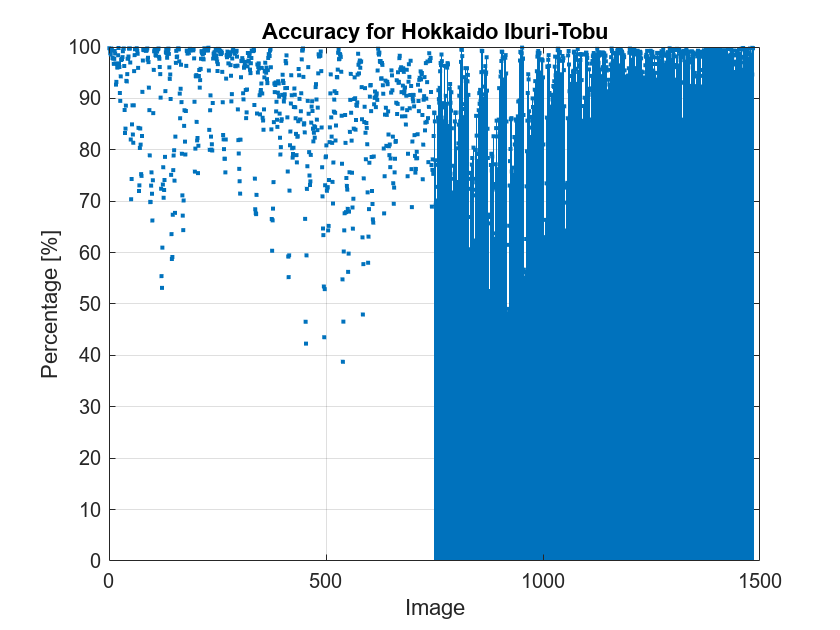

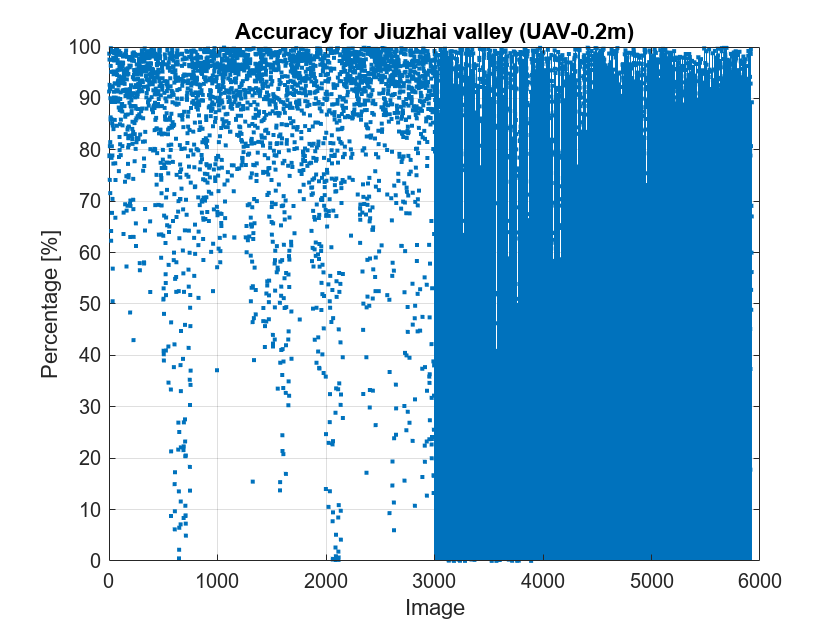


% Loop through each folder to compute stats
for i=1:numel(folders)
    list_imgs = dir(fullfile(orig_dir, folders{i}, 'img', '*.tif')); % Get images
    list_lbls = dir(fullfile(orig_dir, folders{i}, 'label', '*.tif')); % Get images
    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else
        % Create folder to output masks
        if ~exist(fullfile(output_dir,'Plots'), 'dir')
            mkdir(output_dir,'Plots');
        end
        %fprintf("For %s ||| Stats:\n", folders{i});

        % Calc stats per set
        precision_per_set{i} = mean((precision{i}));
        recall_per_set{i} = mean((recall{i}));
        f1_score_per_set{i} = mean((f1_score{i}));
        accuracy_per_set{i} = mean((accuracy{i}));
        
        % Plot statistics
        figure;
        stem(accuracy{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Accuracy for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Accuracy_%s.png',folders{i}));
        saveas(gcf, output_file);% Save current figure
        close(gcf); % Close figure to avoid memory usage
        figure;
        stem(precision{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Precision for %s", folders{i}))
        grid on;
        ylim([0 100]);
        output_file = fullfile(output_dir,'Plots',sprintf('Precision_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(recall{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Recall for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Recall_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(f1_score{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("F1 Score for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('F1_Score_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
    end
end


% Plot per set
figure;
stem(cell2mat(accuracy_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("Accuracy per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Accuracy.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(cell2mat(precision_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("Precision per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Precision.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(cell2mat(recall_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("Recall per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Recall.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(cell2mat(f1_score_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("F1 Score per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','F1_Score.png');
saveas(gcf, output_file);
close(gcf);

overall_precision_hsv_cas_no_closing = mean(cell2mat(precision_per_set))*100;
overall_recall_hsv_cas_no_closing = mean(cell2mat(recall_per_set))*100;
overall_f1_score_hsv_cas_no_closing = mean(cell2mat(f1_score_per_set))*100;
overall_accuracy_hsv_cas_no_closing = mean(cell2mat(accuracy_per_set))*100;

% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- HSV CAS No Morphology -----\n'); 
% Log data
fprintf(output_stats_id, 'Precision = %.5f\n', overall_precision_hsv_cas_no_closing);
fprintf(output_stats_id, 'Recall = %.5f\n', overall_recall_hsv_cas_no_closing);
fprintf(output_stats_id, 'F1 score = %.5f\n', overall_f1_score_hsv_cas_no_closing);
fprintf(output_stats_id, 'Accuracy  = %.5f\n', overall_accuracy_hsv_cas_no_closing);
arr_precision_per_set = cell2mat(precision_per_set);
fprintf(output_stats_id, 'Precision per set: ');
fprintf(output_stats_id, '%.5f, ', arr_precision_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_precision_per_set(end));
arr_recall_per_set = cell2mat(recall_per_set);
fprintf(output_stats_id, 'Recall per set: ');
fprintf(output_stats_id, '%.5f, ', arr_recall_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_recall_per_set(end));
arr_f1_score_per_set = cell2mat(f1_score_per_set);
fprintf(output_stats_id, 'F1 score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_f1_score_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_f1_score_per_set(end));
arr_accuracy_per_set = cell2mat(accuracy_per_set);
fprintf(output_stats_id, 'Accuracy score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_accuracy_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_accuracy_per_set(end));
fprintf(output_stats_id, 'Duration of processing: %.1fs\n', elapsedTime);
% Close file
fclose(output_stats_id);

% Clear workspace to save RAM
clear all

#### Sense Dataset

clc; clear; close all;

imgs_proc = 0;

% Directories
orig_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\archive\TrainData\';
output_dir = 'C:\Users\andre\EE581-LandlideProj\data\hsv_analysis\Sense\No_Normphology';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\data\Stats_classical_methods.txt';

[folder_stats_dir, ~, ~] = fileparts(output_stats_dir);
% Create folder for stats outputs
if ~exist(fullfile(folder_stats_dir, 'dir'))
    mkdir(folder_stats_dir); % Create folder if doesn't exist
end


% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..'})); % Remove

% Set up stats storage
% Assign zero array of its image count
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels
% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count');
else
    true_pos = zeros(1,numel(list_imgs));
    false_pos = zeros(1,numel(list_imgs));
    true_neg = zeros(1,numel(list_imgs));
    false_neg = zeros(1,numel(list_imgs));
    precision = zeros(1,numel(list_imgs));
    recall = zeros(1,numel(list_imgs));
    f1_score = zeros(1,numel(list_imgs));
    accuracy = zeros(1,numel(list_imgs));
end

% Go through through folder
t1 = datetime('now');
% Get list of image and label files
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels

% Create folder for all outputs
if ~exist(output_dir,'dir')
    mkdir(output_dir); % Create folder if doesn't exist
end

% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count for folder: %s', folders{i});
else
    % Iterate through each image (and label) of each folder
    t2 = datetime('now');

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Mask'),'dir')
        mkdir(output_dir,'Mask'); % Create folder if doesn't exist
    end

    for k = 1:numel(list_imgs)
        imgs_proc = imgs_proc + 1;
        % Full path
        img_path = fullfile(orig_dir, folders{1}, list_imgs(k).name);
        lbl_path = fullfile(orig_dir, folders{2}, list_lbls(k).name);

        % Read HDF5 data
        img_info = h5info(img_path);
        img_name = img_info.Datasets(1).Name;
        img_chs = h5read(img_path, ['/' img_name]);
            
        label_info = h5info(lbl_path);
        label_name = label_info.Datasets(1).Name;
        label = h5read(lbl_path, ['/' label_name]);

        % Binarise image
        label = label > 0;

        % Extract channels
        R_CH = squeeze(img_chs(4,:,:));
        G_CH = squeeze(img_chs(3,:,:));
        B_CH = squeeze(img_chs(2,:,:));

        % Combine into an RGB image & label
        img = double(cat(3, R_CH, G_CH, B_CH));
        
        % Normalize images
        if max(img(:)) > 1
            img = img / max(img(:)); % Scale to [0, 1]
        end
        
        img_hsv = rgb2hsv(img);
            
        % Super sample - use interpolation to increase resolution
        scale_factor = 2;
        img_hsv = imresize(img_hsv, scale_factor, 'bicubic'); % Think bicubic is the best
        
        % Convert into HSV format and exctract CHs
        H_CH = img_hsv(:,:,1); % Hue CH
        S_CH = img_hsv(:,:,2); % Saturation CH
        V_CH = img_hsv(:,:,3); % Value CH
        
        % Reduce contrast
        H_mask = H_CH;
        H_mask = histeq(H_mask);
        H_thresh = 0.85;
        H_mask_bin = H_mask >= H_thresh;
        V_mask = V_CH;
        V_mask = histeq(V_mask);
        V_thresh = 0.85;
        V_mask_bin = V_mask >= V_thresh;
        
        % Match areas where landslides could be
        Mask_HV = H_mask_bin & V_mask_bin;
        
        % Remove very small patches by assuming they are like 'salt and pepper' noise
        Mask_HV_denoised = medfilt2(Mask_HV, [3 3]);
            
        % Return image to normal size
        mask = imresize(Mask_HV_denoised, [size(img,1), size(img,2)], 'nearest');
            
        % Statistcally analyse results
        true_pos(k) = sum(label & mask, 'all');
        false_pos(k) = sum(label & ~mask, 'all');
        true_neg(k) = sum(~label & ~mask, 'all');
        false_neg(k) = sum(~label & mask, 'all');
        accuracy(k) = (true_pos(k) + true_neg(k)) / (true_pos(k) + true_neg(k) + false_pos(k) + false_neg(k));
        if (true_pos(k) + false_pos(k)) == 0
            precision(k) = 0;
        else
            precision(k) = true_pos(k) / (true_pos(k) + false_pos(k));
        end
        if (true_pos(k) + false_neg(k)) == 0
            recall(k) = 0;
        else
            recall(k) = true_pos(k) / (true_pos(k) + false_neg(k));
        end
        if (precision(k) + recall(k)) == 0
            f1_score(k) = 0;
        else
            f1_score(k) = (2 * precision(k) * recall(k)) / (precision(k) + recall(k));
        end

        mask_name = split(list_imgs(k).name, '.');
        mask_name = [mask_name{1}, '.jpg'];
        output_file = fullfile(output_dir,'Mask',mask_name);
        imwrite(mask,output_file);
    end
end

t3 = datetime('now');
elapsedTime = seconds(t3-t1); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

Total processing time: 123.6s

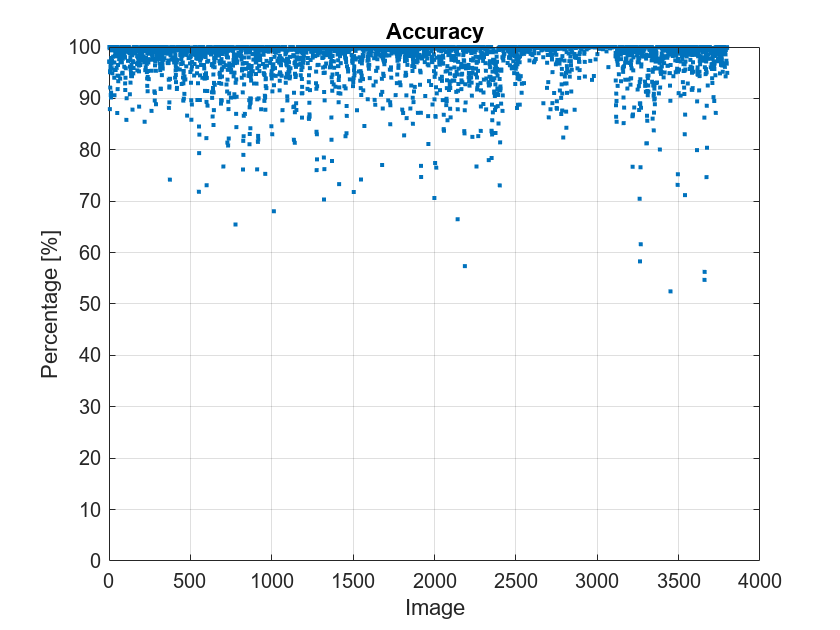


% Go through folder to compute stats
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels
% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count');
else

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Plots'), 'dir')
        mkdir(output_dir,'Plots');
    end

    % Plot statistics
    figure;
    stem(accuracy*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Accuracy");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Accuracy.png');
    saveas(gcf, output_file);% Save current figure
    close(gcf); % Close figure to avoid memory usage
    figure;
    stem(precision*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Precision");
    grid on;
    ylim([0 100]);
    output_file = fullfile(output_dir,'Plots','Precision.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(recall*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Recall");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Recall.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(f1_score*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("F1 Score");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','F1_Score.png');
    saveas(gcf, output_file);
    close(gcf);
end


overall_precision_hsv_sense_cas_no_closing = mean(precision)*100;
overall_recall_hsv_sense_cas_no_closing = mean(recall)*100;
overall_f1_score_hsv_sense_cas_no_closing = mean(f1_score)*100;
overall_accuracy_hsv_sense_cas_no_closing = mean(accuracy)*100;

% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- HSV Sense No Morphology -----\n'); 
% Log data
fprintf(output_stats_id, 'Precision = %.5f\n', overall_precision_hsv_sense_cas_no_closing);
fprintf(output_stats_id, 'Recall = %.5f\n', overall_recall_hsv_sense_cas_no_closing);
fprintf(output_stats_id, 'F1-score = %.5f\n', overall_f1_score_hsv_sense_cas_no_closing);
fprintf(output_stats_id, 'Accuracy = %.5f\n', overall_accuracy_hsv_sense_cas_no_closing);
fprintf(output_stats_id, 'Duration of processing: %.1fs\n', elapsedTime);
% Close file
fclose(output_stats_id);

time_hsv_no_morph = datetime('now')

time_hsv_no_morph = datetime
   02-Apr-2025 02:10:48


save('C:\Users\andre\EE581-LandlideProj\src\classical_methods\Timing\time_hsv_no_morph.mat', 'time_hsv_no_morph');

% Clear workspace to save RAM
clear all;

### HSV Analysis - 5 Opening

#### CAS Dataset

clc; clear; close all;
debug_mode = false;
imgs_proc = 0;

% Directories
orig_dir = 'C:\Users\andre\EE581-LandlideProj\data\original_dataset\';
output_dir = 'C:\Users\andre\EE581-LandlideProj\data\hsv_analysis\CAS\5_Opening';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\data\Stats_classical_methods.txt';

[folder_stats_dir, ~, ~] = fileparts(output_stats_dir);
% Create folder for stats outputs
if ~exist(fullfile(folder_stats_dir, 'dir'))
    mkdir(folder_stats_dir); % Create folder if doesn't exist
end

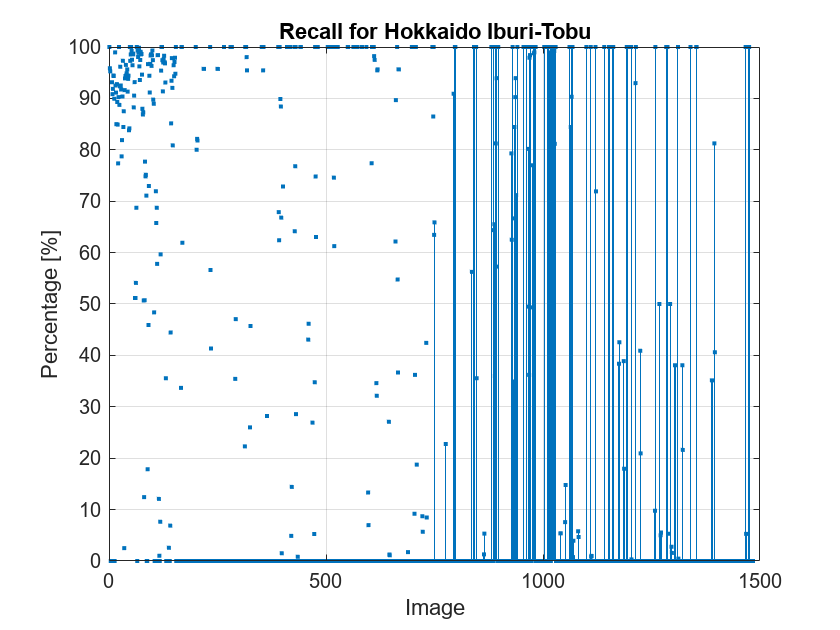

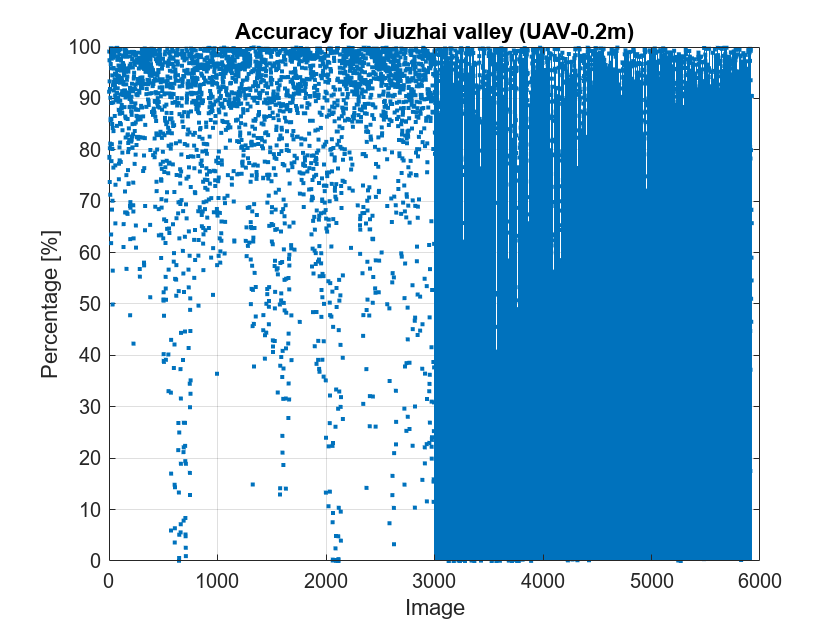


% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..', ...
    'Longxi River(UAV)','Tiburon Peninsula(Sentinel)'})); % Remove

% Set up stats storage
true_pos = cell(numel(folders),1); % Cell array - folder per row
false_pos = cell(numel(folders),1);
true_neg = cell(numel(folders),1);
false_neg = cell(numel(folders),1);
precision = cell(numel(folders),1);
recall = cell(numel(folders),1);
f1_score = cell(numel(folders),1);
accuracy = cell(numel(folders),1);
precision_per_set = cell(1,numel(folders));
recall_per_set = cell(1,numel(folders));
f1_score_per_set = cell(1,numel(folders));
accuracy_per_set = cell(1,numel(folders));

% Loop through each folder & assign zero array of its image count
for i=1:numel(folders)
    list_imgs = dir(fullfile(orig_dir, folders{i}, 'img', '*.tif')); % Get images
    list_lbls = dir(fullfile(orig_dir, folders{i}, 'label', '*.tif')); % Get images
    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else
        true_pos{i} = zeros(1,numel(list_imgs)); % Each cell contains image count
        false_pos{i} = zeros(1,numel(list_imgs));
        true_neg{i} = zeros(1,numel(list_imgs));
        false_neg{i} = zeros(1,numel(list_imgs));
        precision{i} = zeros(1,numel(list_imgs));
        recall{i} = zeros(1,numel(list_imgs));
        f1_score{i} = zeros(1,numel(list_imgs));
        accuracy{i} = zeros(1,numel(list_imgs));
    end
end

% Iterate through each folder
t1 = datetime('now');
for i=1:numel(folders)
    % Directory
    img_dir = fullfile(orig_dir, folders{i}, 'img');
    lbl_dir = fullfile(orig_dir, folders{i}, 'label');

    % Get list of image and label files
    list_imgs = dir(fullfile(img_dir, '*.tif'));
    list_lbls = dir(fullfile(lbl_dir, '*.tif'));
    
    % Create folder to output masks
    if ~exist(fullfile(output_dir,folders{i}), 'dir')
        mkdir(output_dir,folders{i}); % Create folder if doesn't exist
    end

    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else

        % Iterate through each image (and label) of each folder
        t2 = datetime('now');
        for k = 1:numel(list_imgs)
            imgs_proc = imgs_proc + 1;
            % Directory
            img_path = fullfile(img_dir, list_imgs(k).name);
            lbl_path = fullfile(lbl_dir, list_lbls(k).name);
    
            % Load data and label
            img = double(imread(img_path));
            label = double(imread(lbl_path));
    
            % Normalize images
            if max(img(:)) > 1
                img = img / max(img(:)); % Scale to [0, 1]
            end
            if max(label(:)) > 1
                label = label / max(label(:)); % Scale to [0, 1]
            end

            % Binarise the label and invert it so landslied is 1
            
            label_temp = label;
            label_temp(label_temp == 255) = 1;
            label_bin = (label_temp(:,:,1) + label_temp(:,:,2) + label_temp(:,:,3)) > 0;
            label = 1 - label_bin;    
            img_hsv = rgb2hsv(img);
    
            % Super sample - use interpolation to increase resolution
            scale_factor = 2;
            img_hsv = imresize(img_hsv, scale_factor, 'bicubic'); % Think bicubic is the best
        
            % Convert into HSV format and exctract CHs
            R_CH = img(:,:,1); % Red CH
            G_CH = img(:,:,2); % Green CH
            B_CH = img(:,:,3); % Blue CH
            H_CH = img_hsv(:,:,1); % Hue CH
            S_CH = img_hsv(:,:,2); % Saturation CH
            V_CH = img_hsv(:,:,3); % Value CH
        
            % Reduce contrast
            H_mask = H_CH;
            H_mask = histeq(H_mask);
            H_thresh = 0.85;
            H_mask_bin = H_mask >= H_thresh;
            V_mask = V_CH;
            V_mask = histeq(V_mask);
            V_thresh = 0.85;
            V_mask_bin = V_mask >= V_thresh;
        
            % Match areas where landslides could be
            Mask_HV = H_mask_bin & V_mask_bin;
        
            % Remove very small patches by assuming they are like 'salt and pepper' noise
            Mask_HV_denoised = medfilt2(Mask_HV, [3 3]);
            % Fill gaps where landslides could be and return image to normal size
            Mask_HV_denoised_open = imopen(Mask_HV_denoised, strel('disk', 5)); % Fill gaps
            % Return image to normal size
            mask = imresize(Mask_HV_denoised_open, [size(img,1), size(img,2)], 'nearest');
    
            % Statistcally analyse results
            true_pos{i}(k) = sum(label & mask, 'all');
            false_pos{i}(k) = sum(label & ~mask, 'all');
            true_neg{i}(k) = sum(~label & ~mask, 'all');
            false_neg{i}(k) = sum(~label & mask, 'all');
            accuracy{i}(k) = (true_pos{i}(k) + true_neg{i}(k)) / (true_pos{i}(k) + true_neg{i}(k) + false_pos{i}(k) + false_neg{i}(k));
            if (true_pos{i}(k) + false_pos{i}(k)) == 0
                precision{i}(k) = 0;
            else
                precision{i}(k) = true_pos{i}(k) / (true_pos{i}(k) + false_pos{i}(k));
            end
            if (true_pos{i}(k) + false_neg{i}(k)) == 0
                recall{i}(k) = 0;
            else
                recall{i}(k) = true_pos{i}(k) / (true_pos{i}(k) + false_neg{i}(k));
            end
            if (precision{i}(k) + recall{i}(k)) == 0
                f1_score{i}(k) = 0;
            else
                f1_score{i}(k) = (2 * precision{i}(k) * recall{i}(k)) / (precision{i}(k) + recall{i}(k));
            end

            output_file = fullfile(output_dir,folders{i},list_imgs(k).name);
            imwrite(mask,output_file);
        end
    end
    t3 = datetime('now');
    elapsedTime = seconds(t3-t2); % Cacluate elapsed times
    fprintf("%s --- Took %.1fs\n", folders{i} , elapsedTime);    
end
t3 = datetime('now');
elapsedTime = seconds(t3-t1); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

% Loop through each folder to compute stats
for i=1:numel(folders)
    list_imgs = dir(fullfile(orig_dir, folders{i}, 'img', '*.tif')); % Get images
    list_lbls = dir(fullfile(orig_dir, folders{i}, 'label', '*.tif')); % Get images
    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else
        % Create folder to output masks
        if ~exist(fullfile(output_dir,'Plots'), 'dir')
            mkdir(output_dir,'Plots');
        end
        %fprintf("For %s ||| Stats:\n", folders{i});

        % Calc stats per set
        precision_per_set{i} = mean((precision{i}));
        recall_per_set{i} = mean((recall{i}));
        f1_score_per_set{i} = mean((f1_score{i}));
        accuracy_per_set{i} = mean((accuracy{i}));
        
        % Plot statistics
        figure;
        stem(accuracy{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Accuracy for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Accuracy_%s.png',folders{i}));
        saveas(gcf, output_file);% Save current figure
        close(gcf); % Close figure to avoid memory usage
        figure;
        stem(precision{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Precision for %s", folders{i}))
        grid on;
        ylim([0 100]);
        output_file = fullfile(output_dir,'Plots',sprintf('Precision_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(recall{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Recall for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Recall_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(f1_score{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("F1 Score for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('F1_Score_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
    end
end


% Plot per set
figure;
stem(cell2mat(accuracy_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("Accuracy per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Accuracy.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(cell2mat(precision_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("Precision per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Precision.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(cell2mat(recall_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("Recall per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Recall.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(cell2mat(f1_score_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("F1 Score per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','F1_Score.png');
saveas(gcf, output_file);
close(gcf);

overall_precision_hsv_cas_no_closing = mean(cell2mat(precision_per_set))*100;
overall_recall_hsv_cas_no_closing = mean(cell2mat(recall_per_set))*100;
overall_f1_score_hsv_cas_no_closing = mean(cell2mat(f1_score_per_set))*100;
overall_accuracy_hsv_cas_no_closing = mean(cell2mat(accuracy_per_set))*100;

% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- HSV CAS 5 Opening -----\n'); 
% Log data
fprintf(output_stats_id, 'Precision = %.5f\n', overall_precision_hsv_cas_no_closing);
fprintf(output_stats_id, 'Recall = %.5f\n', overall_recall_hsv_cas_no_closing);
fprintf(output_stats_id, 'F1 score = %.5f\n', overall_f1_score_hsv_cas_no_closing);
fprintf(output_stats_id, 'Accuracy  = %.5f\n', overall_accuracy_hsv_cas_no_closing);
arr_precision_per_set = cell2mat(precision_per_set);
fprintf(output_stats_id, 'Precision per set: ');
fprintf(output_stats_id, '%.5f, ', arr_precision_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_precision_per_set(end));
arr_recall_per_set = cell2mat(recall_per_set);
fprintf(output_stats_id, 'Recall per set: ');
fprintf(output_stats_id, '%.5f, ', arr_recall_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_recall_per_set(end));
arr_f1_score_per_set = cell2mat(f1_score_per_set);
fprintf(output_stats_id, 'F1 score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_f1_score_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_f1_score_per_set(end));
arr_accuracy_per_set = cell2mat(accuracy_per_set);
fprintf(output_stats_id, 'Accuracy score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_accuracy_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_accuracy_per_set(end));
fprintf(output_stats_id, 'Duration of processing: %.1fs\n', elapsedTime);
% Close file
fclose(output_stats_id);

% Clear workspace to save RAM
clear all

#### Sense Dataset

clc; clear; close all;

imgs_proc = 0;

% Directories
orig_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\archive\TrainData\';
output_dir = 'C:\Users\andre\EE581-LandlideProj\data\hsv_analysis\Sense\5_Open';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\data\Stats_classical_methods.txt';

[folder_stats_dir, ~, ~] = fileparts(output_stats_dir);
% Create folder for stats outputs
if ~exist(fullfile(folder_stats_dir, 'dir'))
    mkdir(folder_stats_dir); % Create folder if doesn't exist
end


% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..'})); % Remove

% Set up stats storage
% Assign zero array of its image count
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels
% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count');
else
    true_pos = zeros(1,numel(list_imgs));
    false_pos = zeros(1,numel(list_imgs));
    true_neg = zeros(1,numel(list_imgs));
    false_neg = zeros(1,numel(list_imgs));
    precision = zeros(1,numel(list_imgs));
    recall = zeros(1,numel(list_imgs));
    f1_score = zeros(1,numel(list_imgs));
    accuracy = zeros(1,numel(list_imgs));
end

% Go through through folder
t1 = datetime('now');
% Get list of image and label files
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels

% Create folder for all outputs
if ~exist(output_dir,'dir')
    mkdir(output_dir); % Create folder if doesn't exist
end

% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count for folder: %s', folders{i});
else
    % Iterate through each image (and label) of each folder
    t2 = datetime('now');

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Mask'),'dir')
        mkdir(output_dir,'Mask'); % Create folder if doesn't exist
    end

    for k = 1:numel(list_imgs)
        imgs_proc = imgs_proc + 1;
        % Full path
        img_path = fullfile(orig_dir, folders{1}, list_imgs(k).name);
        lbl_path = fullfile(orig_dir, folders{2}, list_lbls(k).name);

        % Read HDF5 data
        img_info = h5info(img_path);
        img_name = img_info.Datasets(1).Name;
        img_chs = h5read(img_path, ['/' img_name]);
            
        label_info = h5info(lbl_path);
        label_name = label_info.Datasets(1).Name;
        label = h5read(lbl_path, ['/' label_name]);

        % Binarise image
        label = label > 0;

        % Extract channels
        R_CH = squeeze(img_chs(4,:,:));
        G_CH = squeeze(img_chs(3,:,:));
        B_CH = squeeze(img_chs(2,:,:));

        % Combine into an RGB image & label
        img = double(cat(3, R_CH, G_CH, B_CH));
        
        % Normalize images
        if max(img(:)) > 1
            img = img / max(img(:)); % Scale to [0, 1]
        end
        
        img_hsv = rgb2hsv(img);
            
        % Super sample - use interpolation to increase resolution
        scale_factor = 2;
        img_hsv = imresize(img_hsv, scale_factor, 'bicubic'); % Think bicubic is the best
        
        % Convert into HSV format and exctract CHs
        H_CH = img_hsv(:,:,1); % Hue CH
        S_CH = img_hsv(:,:,2); % Saturation CH
        V_CH = img_hsv(:,:,3); % Value CH
        
        % Reduce contrast
        H_mask = H_CH;
        H_mask = histeq(H_mask);
        H_thresh = 0.85;
        H_mask_bin = H_mask >= H_thresh;
        V_mask = V_CH;
        V_mask = histeq(V_mask);
        V_thresh = 0.85;
        V_mask_bin = V_mask >= V_thresh;
        
        % Match areas where landslides could be
        Mask_HV = H_mask_bin & V_mask_bin;
        
        % Remove very small patches by assuming they are like 'salt and pepper' noise
        Mask_HV_denoised = medfilt2(Mask_HV, [3 3]);
        % Fill gaps where landslides could be and return image to normal size
        Mask_HV_denoised_open = imopen(Mask_HV_denoised, strel('disk', 5)); % Fill gaps
        % Return image to normal size
        mask = imresize(Mask_HV_denoised_open, [size(img,1), size(img,2)], 'nearest');
            
        % Statistcally analyse results
        true_pos(k) = sum(label & mask, 'all');
        false_pos(k) = sum(label & ~mask, 'all');
        true_neg(k) = sum(~label & ~mask, 'all');
        false_neg(k) = sum(~label & mask, 'all');
        accuracy(k) = (true_pos(k) + true_neg(k)) / (true_pos(k) + true_neg(k) + false_pos(k) + false_neg(k));
        if (true_pos(k) + false_pos(k)) == 0
            precision(k) = 0;
        else
            precision(k) = true_pos(k) / (true_pos(k) + false_pos(k));
        end
        if (true_pos(k) + false_neg(k)) == 0
            recall(k) = 0;
        else
            recall(k) = true_pos(k) / (true_pos(k) + false_neg(k));
        end
        if (precision(k) + recall(k)) == 0
            f1_score(k) = 0;
        else
            f1_score(k) = (2 * precision(k) * recall(k)) / (precision(k) + recall(k));
        end

        mask_name = split(list_imgs(k).name, '.');
        mask_name = [mask_name{1}, '.jpg'];
        output_file = fullfile(output_dir,'Mask',mask_name);
        imwrite(mask,output_file);
    end
end

t3 = datetime('now');
elapsedTime = seconds(t3-t1); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

Total processing time: 136.9s

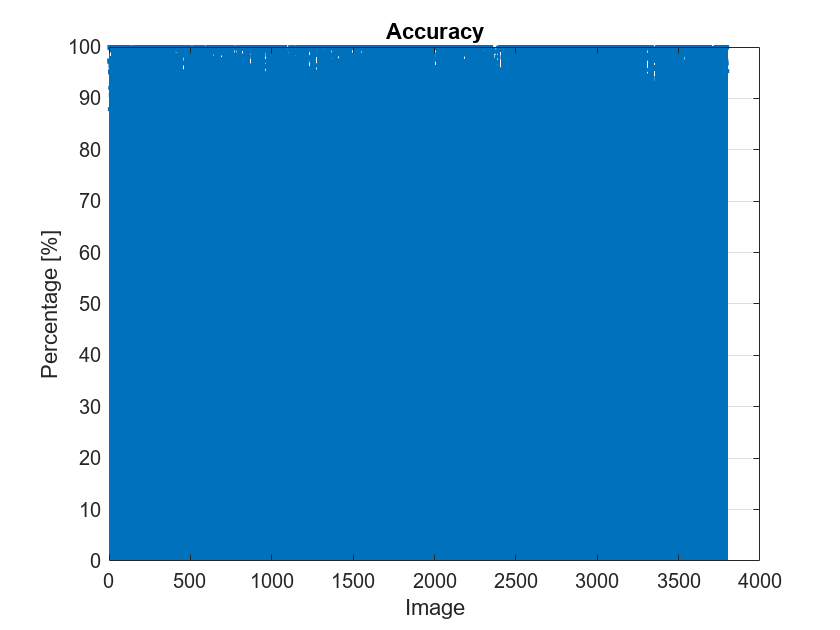

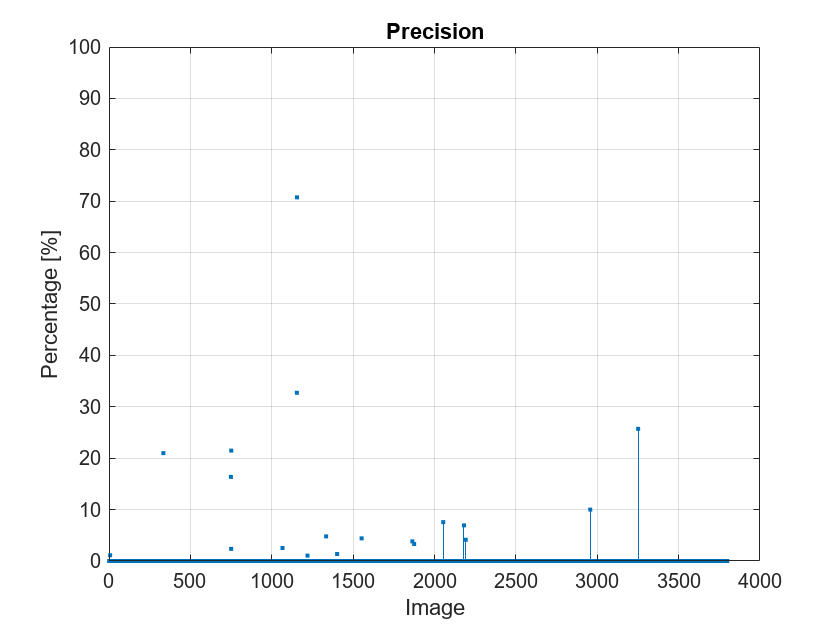

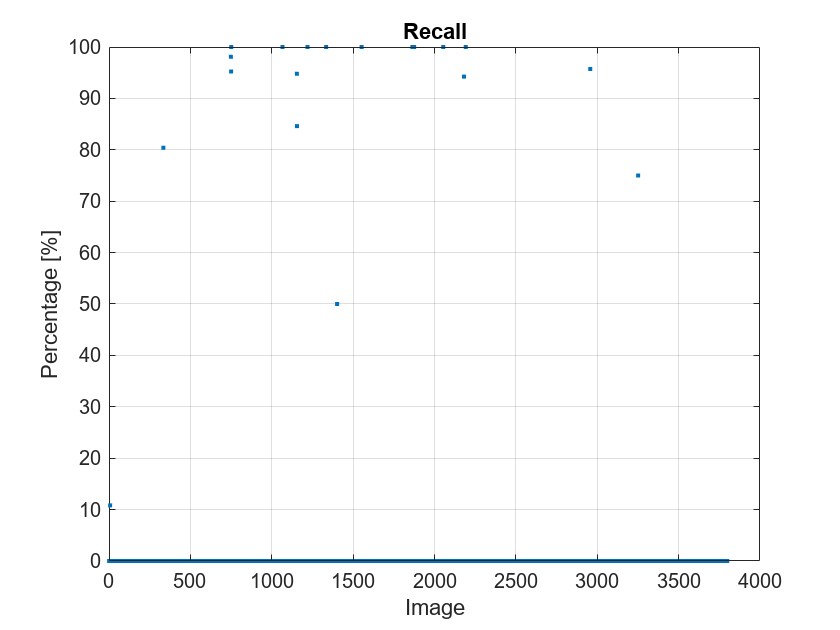


% Go through folder to compute stats
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels
% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count');
else

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Plots'), 'dir')
        mkdir(output_dir,'Plots');
    end

    % Plot statistics
    figure;
    stem(accuracy*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Accuracy");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Accuracy.png');
    saveas(gcf, output_file);% Save current figure
    close(gcf); % Close figure to avoid memory usage
    figure;
    stem(precision*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Precision");
    grid on;
    ylim([0 100]);
    output_file = fullfile(output_dir,'Plots','Precision.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(recall*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Recall");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Recall.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(f1_score*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("F1 Score");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','F1_Score.png');
    saveas(gcf, output_file);
    close(gcf);
end


overall_precision_hsv_sense_cas_no_closing = mean(precision)*100;
overall_recall_hsv_sense_cas_no_closing = mean(recall)*100;
overall_f1_score_hsv_sense_cas_no_closing = mean(f1_score)*100;
overall_accuracy_hsv_sense_cas_no_closing = mean(accuracy)*100;

% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- HSV Sense 5 Opening -----\n'); 
% Log data
fprintf(output_stats_id, 'Precision = %.5f\n', overall_precision_hsv_sense_cas_no_closing);
fprintf(output_stats_id, 'Recall = %.5f\n', overall_recall_hsv_sense_cas_no_closing);
fprintf(output_stats_id, 'F1-score = %.5f\n', overall_f1_score_hsv_sense_cas_no_closing);
fprintf(output_stats_id, 'Accuracy = %.5f\n', overall_accuracy_hsv_sense_cas_no_closing);
fprintf(output_stats_id, 'Duration of processing: %.1fs\n', elapsedTime);
% Close file
fclose(output_stats_id);

time_hsv_5_open= datetime('now')

time_hsv_5_open = datetime
   02-Apr-2025 02:39:54


save('C:\Users\andre\EE581-LandlideProj\src\classical_methods\Timing\time_hsv_5_open.mat', 'time_hsv_5_open');

% Clear workspace to save RAM
clear all;

### HSV Analysis - 7 Opening

#### CAS Dataset

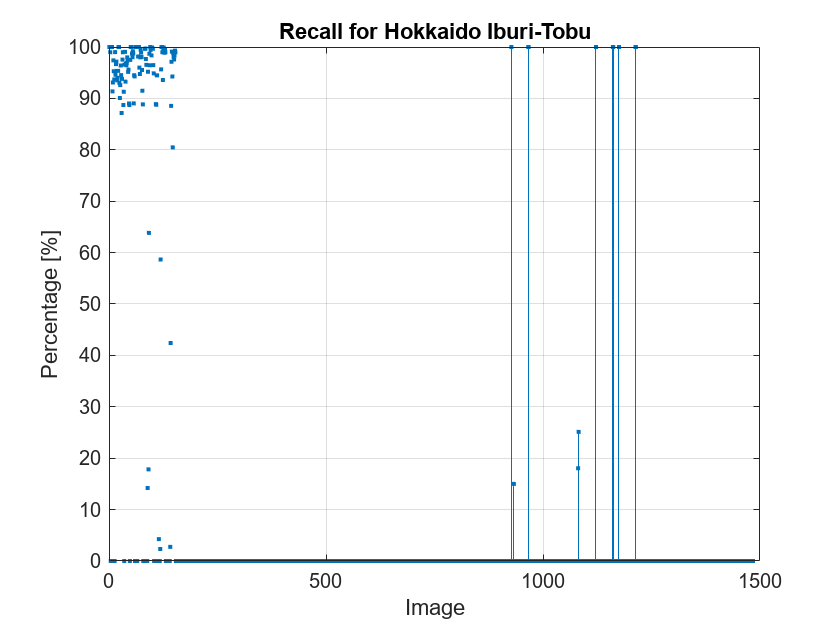

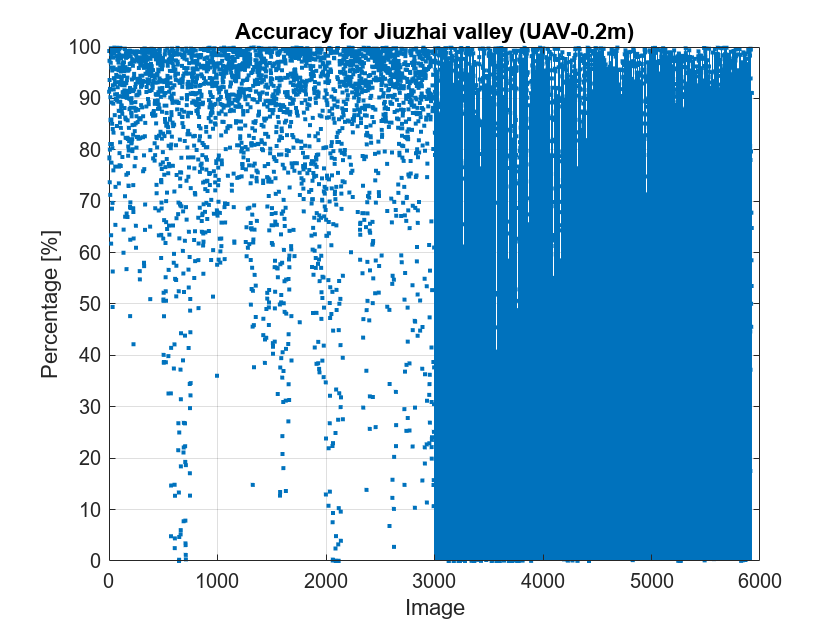

clc; clear; close all;
debug_mode = false;
imgs_proc = 0;

% Directories
orig_dir = 'C:\Users\andre\EE581-LandlideProj\data\original_dataset\';
output_dir = 'C:\Users\andre\EE581-LandlideProj\data\hsv_analysis\CAS\7_Opening';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\data\Stats_classical_methods.txt';

[folder_stats_dir, ~, ~] = fileparts(output_stats_dir);
% Create folder for stats outputs
if ~exist(fullfile(folder_stats_dir, 'dir'))
    mkdir(folder_stats_dir); % Create folder if doesn't exist
end

% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..', ...
    'Longxi River(UAV)','Tiburon Peninsula(Sentinel)'})); % Remove

% Set up stats storage
true_pos = cell(numel(folders),1); % Cell array - folder per row
false_pos = cell(numel(folders),1);
true_neg = cell(numel(folders),1);
false_neg = cell(numel(folders),1);
precision = cell(numel(folders),1);
recall = cell(numel(folders),1);
f1_score = cell(numel(folders),1);
accuracy = cell(numel(folders),1);
precision_per_set = cell(1,numel(folders));
recall_per_set = cell(1,numel(folders));
f1_score_per_set = cell(1,numel(folders));
accuracy_per_set = cell(1,numel(folders));

% Loop through each folder & assign zero array of its image count
for i=1:numel(folders)
    list_imgs = dir(fullfile(orig_dir, folders{i}, 'img', '*.tif')); % Get images
    list_lbls = dir(fullfile(orig_dir, folders{i}, 'label', '*.tif')); % Get images
    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else
        true_pos{i} = zeros(1,numel(list_imgs)); % Each cell contains image count
        false_pos{i} = zeros(1,numel(list_imgs));
        true_neg{i} = zeros(1,numel(list_imgs));
        false_neg{i} = zeros(1,numel(list_imgs));
        precision{i} = zeros(1,numel(list_imgs));
        recall{i} = zeros(1,numel(list_imgs));
        f1_score{i} = zeros(1,numel(list_imgs));
        accuracy{i} = zeros(1,numel(list_imgs));
    end
end

% Iterate through each folder
t1 = datetime('now');
for i=1:numel(folders)
    % Directory
    img_dir = fullfile(orig_dir, folders{i}, 'img');
    lbl_dir = fullfile(orig_dir, folders{i}, 'label');

    % Get list of image and label files
    list_imgs = dir(fullfile(img_dir, '*.tif'));
    list_lbls = dir(fullfile(lbl_dir, '*.tif'));
    
    % Create folder to output masks
    if ~exist(fullfile(output_dir,folders{i}), 'dir')
        mkdir(output_dir,folders{i}); % Create folder if doesn't exist
    end

    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else

        % Iterate through each image (and label) of each folder
        t2 = datetime('now');
        for k = 1:numel(list_imgs)
            imgs_proc = imgs_proc + 1;
            % Directory
            img_path = fullfile(img_dir, list_imgs(k).name);
            lbl_path = fullfile(lbl_dir, list_lbls(k).name);
    
            % Load data and label
            img = double(imread(img_path));
            label = double(imread(lbl_path));
    
            % Normalize images
            if max(img(:)) > 1
                img = img / max(img(:)); % Scale to [0, 1]
            end
            if max(label(:)) > 1
                label = label / max(label(:)); % Scale to [0, 1]
            end

            % Binarise the label and invert it so landslied is 1
            
            label_temp = label;
            label_temp(label_temp == 255) = 1;
            label_bin = (label_temp(:,:,1) + label_temp(:,:,2) + label_temp(:,:,3)) > 0;
            label = 1 - label_bin;    
            img_hsv = rgb2hsv(img);
    
            % Super sample - use interpolation to increase resolution
            scale_factor = 2;
            img_hsv = imresize(img_hsv, scale_factor, 'bicubic'); % Think bicubic is the best
        
            % Convert into HSV format and exctract CHs
            R_CH = img(:,:,1); % Red CH
            G_CH = img(:,:,2); % Green CH
            B_CH = img(:,:,3); % Blue CH
            H_CH = img_hsv(:,:,1); % Hue CH
            S_CH = img_hsv(:,:,2); % Saturation CH
            V_CH = img_hsv(:,:,3); % Value CH
        
            % Reduce contrast
            H_mask = H_CH;
            H_mask = histeq(H_mask);
            H_thresh = 0.85;
            H_mask_bin = H_mask >= H_thresh;
            V_mask = V_CH;
            V_mask = histeq(V_mask);
            V_thresh = 0.85;
            V_mask_bin = V_mask >= V_thresh;
        
            % Match areas where landslides could be
            Mask_HV = H_mask_bin & V_mask_bin;
        
            % Remove very small patches by assuming they are like 'salt and pepper' noise
            Mask_HV_denoised = medfilt2(Mask_HV, [3 3]);
            % Fill gaps where landslides could be and return image to normal size
            Mask_HV_denoised_open = imopen(Mask_HV_denoised, strel('disk', 7)); % Fill gaps
            % Return image to normal size
            mask = imresize(Mask_HV_denoised_open, [size(img,1), size(img,2)], 'nearest');
    
            % Statistcally analyse results
            true_pos{i}(k) = sum(label & mask, 'all');
            false_pos{i}(k) = sum(label & ~mask, 'all');
            true_neg{i}(k) = sum(~label & ~mask, 'all');
            false_neg{i}(k) = sum(~label & mask, 'all');
            accuracy{i}(k) = (true_pos{i}(k) + true_neg{i}(k)) / (true_pos{i}(k) + true_neg{i}(k) + false_pos{i}(k) + false_neg{i}(k));
            if (true_pos{i}(k) + false_pos{i}(k)) == 0
                precision{i}(k) = 0;
            else
                precision{i}(k) = true_pos{i}(k) / (true_pos{i}(k) + false_pos{i}(k));
            end
            if (true_pos{i}(k) + false_neg{i}(k)) == 0
                recall{i}(k) = 0;
            else
                recall{i}(k) = true_pos{i}(k) / (true_pos{i}(k) + false_neg{i}(k));
            end
            if (precision{i}(k) + recall{i}(k)) == 0
                f1_score{i}(k) = 0;
            else
                f1_score{i}(k) = (2 * precision{i}(k) * recall{i}(k)) / (precision{i}(k) + recall{i}(k));
            end

            output_file = fullfile(output_dir,folders{i},list_imgs(k).name);
            imwrite(mask,output_file);
        end
    end
    t3 = datetime('now');
    elapsedTime = seconds(t3-t2); % Cacluate elapsed times
    fprintf("%s --- Took %.1fs\n", folders{i} , elapsedTime);    
end
t3 = datetime('now');
elapsedTime = seconds(t3-t1); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

% Loop through each folder to compute stats
for i=1:numel(folders)
    list_imgs = dir(fullfile(orig_dir, folders{i}, 'img', '*.tif')); % Get images
    list_lbls = dir(fullfile(orig_dir, folders{i}, 'label', '*.tif')); % Get images
    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else
        % Create folder to output masks
        if ~exist(fullfile(output_dir,'Plots'), 'dir')
            mkdir(output_dir,'Plots');
        end
        %fprintf("For %s ||| Stats:\n", folders{i});

        % Calc stats per set
        precision_per_set{i} = mean((precision{i}));
        recall_per_set{i} = mean((recall{i}));
        f1_score_per_set{i} = mean((f1_score{i}));
        accuracy_per_set{i} = mean((accuracy{i}));
        
        % Plot statistics
        figure;
        stem(accuracy{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Accuracy for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Accuracy_%s.png',folders{i}));
        saveas(gcf, output_file);% Save current figure
        close(gcf); % Close figure to avoid memory usage
        figure;
        stem(precision{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Precision for %s", folders{i}))
        grid on;
        ylim([0 100]);
        output_file = fullfile(output_dir,'Plots',sprintf('Precision_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(recall{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Recall for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Recall_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(f1_score{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("F1 Score for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('F1_Score_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
    end
end


% Plot per set
figure;
stem(cell2mat(accuracy_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("Accuracy per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Accuracy.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(cell2mat(precision_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("Precision per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Precision.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(cell2mat(recall_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("Recall per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Recall.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(cell2mat(f1_score_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("F1 Score per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','F1_Score.png');
saveas(gcf, output_file);
close(gcf);

overall_precision_hsv_cas_no_closing = mean(cell2mat(precision_per_set))*100;
overall_recall_hsv_cas_no_closing = mean(cell2mat(recall_per_set))*100;
overall_f1_score_hsv_cas_no_closing = mean(cell2mat(f1_score_per_set))*100;
overall_accuracy_hsv_cas_no_closing = mean(cell2mat(accuracy_per_set))*100;

% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- HSV CAS 7 Opening -----\n'); 
% Log data
fprintf(output_stats_id, 'Precision = %.5f\n', overall_precision_hsv_cas_no_closing);
fprintf(output_stats_id, 'Recall = %.5f\n', overall_recall_hsv_cas_no_closing);
fprintf(output_stats_id, 'F1 score = %.5f\n', overall_f1_score_hsv_cas_no_closing);
fprintf(output_stats_id, 'Accuracy  = %.5f\n', overall_accuracy_hsv_cas_no_closing);
arr_precision_per_set = cell2mat(precision_per_set);
fprintf(output_stats_id, 'Precision per set: ');
fprintf(output_stats_id, '%.5f, ', arr_precision_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_precision_per_set(end));
arr_recall_per_set = cell2mat(recall_per_set);
fprintf(output_stats_id, 'Recall per set: ');
fprintf(output_stats_id, '%.5f, ', arr_recall_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_recall_per_set(end));
arr_f1_score_per_set = cell2mat(f1_score_per_set);
fprintf(output_stats_id, 'F1 score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_f1_score_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_f1_score_per_set(end));
arr_accuracy_per_set = cell2mat(accuracy_per_set);
fprintf(output_stats_id, 'Accuracy score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_accuracy_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_accuracy_per_set(end));
fprintf(output_stats_id, 'Duration of processing: %.1fs\n', elapsedTime);
% Close file
fclose(output_stats_id);

% Clear workspace to save RAM
clear all

#### Sense Dataset

clc; clear; close all;

imgs_proc = 0;

% Directories
orig_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\archive\TrainData\';
output_dir = 'C:\Users\andre\EE581-LandlideProj\data\hsv_analysis\Sense\7_Open';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\data\Stats_classical_methods.txt';

[folder_stats_dir, ~, ~] = fileparts(output_stats_dir);
% Create folder for stats outputs
if ~exist(fullfile(folder_stats_dir, 'dir'))
    mkdir(folder_stats_dir); % Create folder if doesn't exist
end


% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..'})); % Remove

% Set up stats storage
% Assign zero array of its image count
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels
% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count');
else
    true_pos = zeros(1,numel(list_imgs));
    false_pos = zeros(1,numel(list_imgs));
    true_neg = zeros(1,numel(list_imgs));
    false_neg = zeros(1,numel(list_imgs));
    precision = zeros(1,numel(list_imgs));
    recall = zeros(1,numel(list_imgs));
    f1_score = zeros(1,numel(list_imgs));
    accuracy = zeros(1,numel(list_imgs));
end

% Go through through folder
t1 = datetime('now');
% Get list of image and label files
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels

% Create folder for all outputs
if ~exist(output_dir,'dir')
    mkdir(output_dir); % Create folder if doesn't exist
end

% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count for folder: %s', folders{i});
else
    % Iterate through each image (and label) of each folder
    t2 = datetime('now');

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Mask'),'dir')
        mkdir(output_dir,'Mask'); % Create folder if doesn't exist
    end

    for k = 1:numel(list_imgs)
        imgs_proc = imgs_proc + 1;
        % Full path
        img_path = fullfile(orig_dir, folders{1}, list_imgs(k).name);
        lbl_path = fullfile(orig_dir, folders{2}, list_lbls(k).name);

        % Read HDF5 data
        img_info = h5info(img_path);
        img_name = img_info.Datasets(1).Name;
        img_chs = h5read(img_path, ['/' img_name]);
            
        label_info = h5info(lbl_path);
        label_name = label_info.Datasets(1).Name;
        label = h5read(lbl_path, ['/' label_name]);

        % Binarise image
        label = label > 0;

        % Extract channels
        R_CH = squeeze(img_chs(4,:,:));
        G_CH = squeeze(img_chs(3,:,:));
        B_CH = squeeze(img_chs(2,:,:));

        % Combine into an RGB image & label
        img = double(cat(3, R_CH, G_CH, B_CH));
        
        % Normalize images
        if max(img(:)) > 1
            img = img / max(img(:)); % Scale to [0, 1]
        end
        
        img_hsv = rgb2hsv(img);
            
        % Super sample - use interpolation to increase resolution
        scale_factor = 2;
        img_hsv = imresize(img_hsv, scale_factor, 'bicubic'); % Think bicubic is the best
        
        % Convert into HSV format and exctract CHs
        H_CH = img_hsv(:,:,1); % Hue CH
        S_CH = img_hsv(:,:,2); % Saturation CH
        V_CH = img_hsv(:,:,3); % Value CH
        
        % Reduce contrast
        H_mask = H_CH;
        H_mask = histeq(H_mask);
        H_thresh = 0.85;
        H_mask_bin = H_mask >= H_thresh;
        V_mask = V_CH;
        V_mask = histeq(V_mask);
        V_thresh = 0.85;
        V_mask_bin = V_mask >= V_thresh;
        
        % Match areas where landslides could be
        Mask_HV = H_mask_bin & V_mask_bin;
        
        % Remove very small patches by assuming they are like 'salt and pepper' noise
        Mask_HV_denoised = medfilt2(Mask_HV, [3 3]);
        % Fill gaps where landslides could be and return image to normal size
        Mask_HV_denoised_open = imopen(Mask_HV_denoised, strel('disk', 7)); % Fill gaps
        % Return image to normal size
        mask = imresize(Mask_HV_denoised_open, [size(img,1), size(img,2)], 'nearest');
            
        % Statistcally analyse results
        true_pos(k) = sum(label & mask, 'all');
        false_pos(k) = sum(label & ~mask, 'all');
        true_neg(k) = sum(~label & ~mask, 'all');
        false_neg(k) = sum(~label & mask, 'all');
        accuracy(k) = (true_pos(k) + true_neg(k)) / (true_pos(k) + true_neg(k) + false_pos(k) + false_neg(k));
        if (true_pos(k) + false_pos(k)) == 0
            precision(k) = 0;
        else
            precision(k) = true_pos(k) / (true_pos(k) + false_pos(k));
        end
        if (true_pos(k) + false_neg(k)) == 0
            recall(k) = 0;
        else
            recall(k) = true_pos(k) / (true_pos(k) + false_neg(k));
        end
        if (precision(k) + recall(k)) == 0
            f1_score(k) = 0;
        else
            f1_score(k) = (2 * precision(k) * recall(k)) / (precision(k) + recall(k));
        end

        mask_name = split(list_imgs(k).name, '.');
        mask_name = [mask_name{1}, '.jpg'];
        output_file = fullfile(output_dir,'Mask',mask_name);
        imwrite(mask,output_file);
    end
end

t3 = datetime('now');
elapsedTime = seconds(t3-t1); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

Total processing time: 132.6s

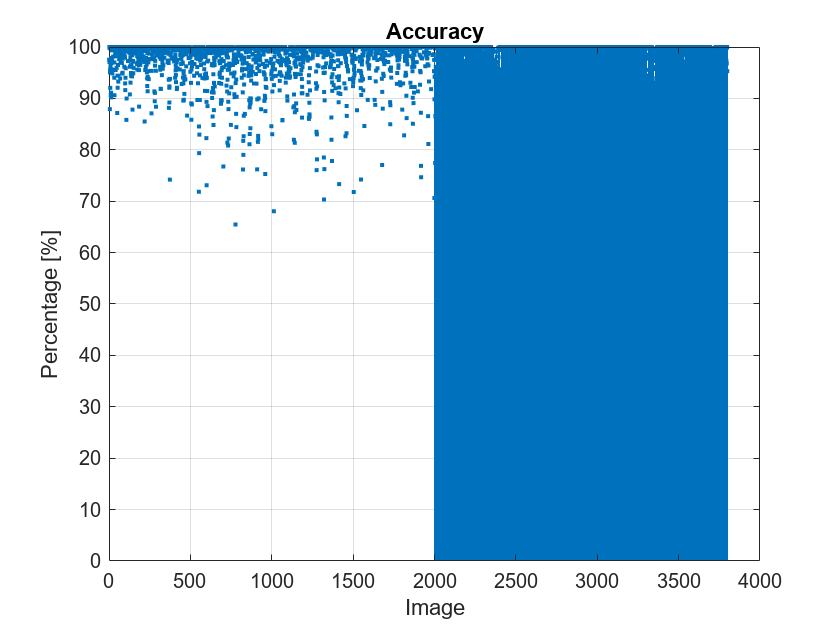

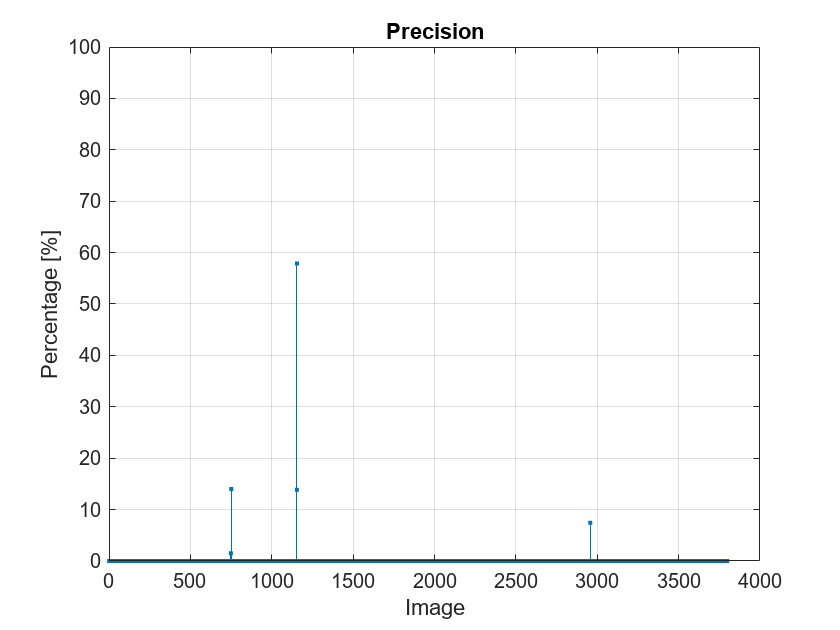


% Go through folder to compute stats
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels
% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count');
else

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Plots'), 'dir')
        mkdir(output_dir,'Plots');
    end

    % Plot statistics
    figure;
    stem(accuracy*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Accuracy");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Accuracy.png');
    saveas(gcf, output_file);% Save current figure
    close(gcf); % Close figure to avoid memory usage
    figure;
    stem(precision*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Precision");
    grid on;
    ylim([0 100]);
    output_file = fullfile(output_dir,'Plots','Precision.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(recall*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Recall");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Recall.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(f1_score*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("F1 Score");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','F1_Score.png');
    saveas(gcf, output_file);
    close(gcf);
end


overall_precision_hsv_sense_cas_no_closing = mean(precision)*100;
overall_recall_hsv_sense_cas_no_closing = mean(recall)*100;
overall_f1_score_hsv_sense_cas_no_closing = mean(f1_score)*100;
overall_accuracy_hsv_sense_cas_no_closing = mean(accuracy)*100;

% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- HSV Sense 7 Opening -----\n'); 
% Log data
fprintf(output_stats_id, 'Precision = %.5f\n', overall_precision_hsv_sense_cas_no_closing);
fprintf(output_stats_id, 'Recall = %.5f\n', overall_recall_hsv_sense_cas_no_closing);
fprintf(output_stats_id, 'F1-score = %.5f\n', overall_f1_score_hsv_sense_cas_no_closing);
fprintf(output_stats_id, 'Accuracy = %.5f\n', overall_accuracy_hsv_sense_cas_no_closing);
fprintf(output_stats_id, 'Duration of processing: %.1fs\n', elapsedTime);
% Close file
fclose(output_stats_id);

time_hsv_7_open= datetime('now')

time_hsv_7_open = datetime
   02-Apr-2025 03:10:14


save('C:\Users\andre\EE581-LandlideProj\src\classical_methods\Timing\time_hsv_7_open.mat', 'time_hsv_7_open');
% Clear workspace to save RAM
clear all;

### HSV Analysis - 5 Closing

#### CAS Dataset

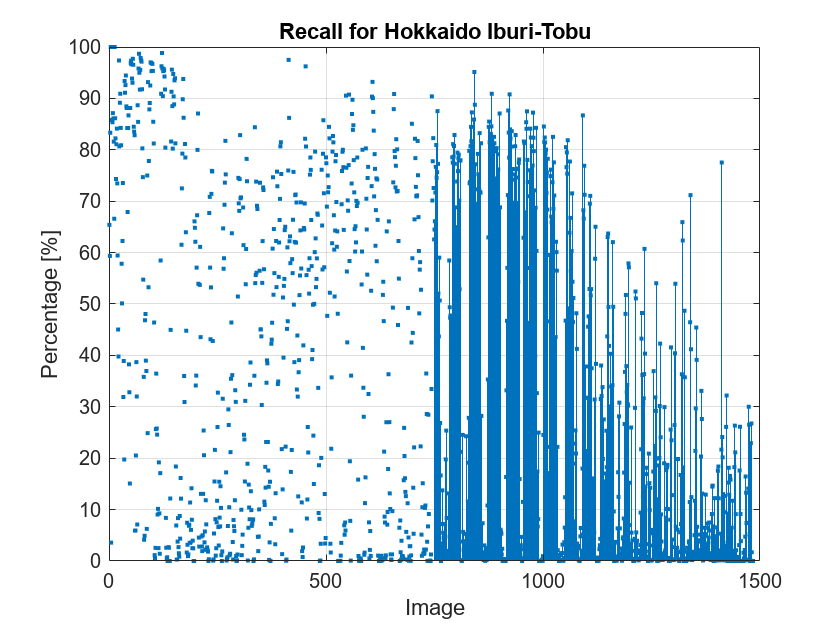

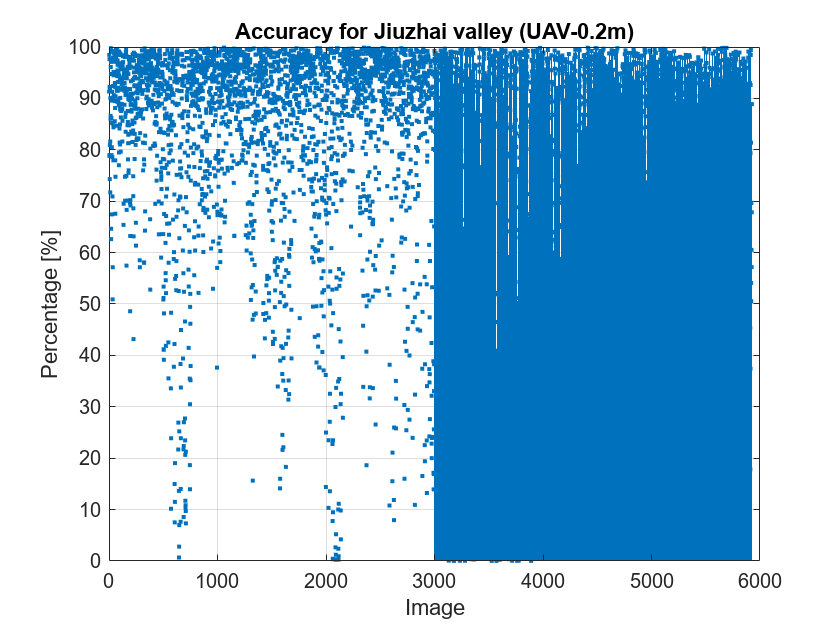

clc; clear; close all;
debug_mode = false;
imgs_proc = 0;

% Directories
orig_dir = 'C:\Users\andre\EE581-LandlideProj\data\original_dataset\';
output_dir = 'C:\Users\andre\EE581-LandlideProj\data\hsv_analysis\CAS\5_Closing';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\data\Stats_classical_methods.txt';

[folder_stats_dir, ~, ~] = fileparts(output_stats_dir);
% Create folder for stats outputs
if ~exist(fullfile(folder_stats_dir, 'dir'))
    mkdir(folder_stats_dir); % Create folder if doesn't exist
end

% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..', ...
    'Longxi River(UAV)','Tiburon Peninsula(Sentinel)'})); % Remove

% Set up stats storage
true_pos = cell(numel(folders),1); % Cell array - folder per row
false_pos = cell(numel(folders),1);
true_neg = cell(numel(folders),1);
false_neg = cell(numel(folders),1);
precision = cell(numel(folders),1);
recall = cell(numel(folders),1);
f1_score = cell(numel(folders),1);
accuracy = cell(numel(folders),1);
precision_per_set = cell(1,numel(folders));
recall_per_set = cell(1,numel(folders));
f1_score_per_set = cell(1,numel(folders));
accuracy_per_set = cell(1,numel(folders));

% Loop through each folder & assign zero array of its image count
for i=1:numel(folders)
    list_imgs = dir(fullfile(orig_dir, folders{i}, 'img', '*.tif')); % Get images
    list_lbls = dir(fullfile(orig_dir, folders{i}, 'label', '*.tif')); % Get images
    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else
        true_pos{i} = zeros(1,numel(list_imgs)); % Each cell contains image count
        false_pos{i} = zeros(1,numel(list_imgs));
        true_neg{i} = zeros(1,numel(list_imgs));
        false_neg{i} = zeros(1,numel(list_imgs));
        precision{i} = zeros(1,numel(list_imgs));
        recall{i} = zeros(1,numel(list_imgs));
        f1_score{i} = zeros(1,numel(list_imgs));
        accuracy{i} = zeros(1,numel(list_imgs));
    end
end

% Iterate through each folder
t1 = datetime('now');
for i=1:numel(folders)
    % Directory
    img_dir = fullfile(orig_dir, folders{i}, 'img');
    lbl_dir = fullfile(orig_dir, folders{i}, 'label');

    % Get list of image and label files
    list_imgs = dir(fullfile(img_dir, '*.tif'));
    list_lbls = dir(fullfile(lbl_dir, '*.tif'));
    
    % Create folder to output masks
    if ~exist(fullfile(output_dir,folders{i}), 'dir')
        mkdir(output_dir,folders{i}); % Create folder if doesn't exist
    end

    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else

        % Iterate through each image (and label) of each folder
        t2 = datetime('now');
        for k = 1:numel(list_imgs)
            imgs_proc = imgs_proc + 1;
            % Directory
            img_path = fullfile(img_dir, list_imgs(k).name);
            lbl_path = fullfile(lbl_dir, list_lbls(k).name);
    
            % Load data and label
            img = double(imread(img_path));
            label = double(imread(lbl_path));
    
            % Normalize images
            if max(img(:)) > 1
                img = img / max(img(:)); % Scale to [0, 1]
            end
            if max(label(:)) > 1
                label = label / max(label(:)); % Scale to [0, 1]
            end

            % Binarise the label and invert it so landslied is 1
            
            label_temp = label;
            label_temp(label_temp == 255) = 1;
            label_bin = (label_temp(:,:,1) + label_temp(:,:,2) + label_temp(:,:,3)) > 0;
            label = 1 - label_bin;    
            img_hsv = rgb2hsv(img);
    
            % Super sample - use interpolation to increase resolution
            scale_factor = 2;
            img_hsv = imresize(img_hsv, scale_factor, 'bicubic'); % Think bicubic is the best
        
            % Convert into HSV format and exctract CHs
            R_CH = img(:,:,1); % Red CH
            G_CH = img(:,:,2); % Green CH
            B_CH = img(:,:,3); % Blue CH
            H_CH = img_hsv(:,:,1); % Hue CH
            S_CH = img_hsv(:,:,2); % Saturation CH
            V_CH = img_hsv(:,:,3); % Value CH
        
            % Reduce contrast
            H_mask = H_CH;
            H_mask = histeq(H_mask);
            H_thresh = 0.85;
            H_mask_bin = H_mask >= H_thresh;
            V_mask = V_CH;
            V_mask = histeq(V_mask);
            V_thresh = 0.85;
            V_mask_bin = V_mask >= V_thresh;
        
            % Match areas where landslides could be
            Mask_HV = H_mask_bin & V_mask_bin;
        
            % Remove very small patches by assuming they are like 'salt and pepper' noise
            Mask_HV_denoised = medfilt2(Mask_HV, [3 3]);
            % Fill gaps where landslides could be and return image to normal size
            Mask_HV_denoised_close = imclose(Mask_HV_denoised, strel('disk', 5)); % Fill gaps
            % Return image to normal size
            mask = imresize(Mask_HV_denoised_close, [size(img,1), size(img,2)], 'nearest');
    
            % Statistcally analyse results
            true_pos{i}(k) = sum(label & mask, 'all');
            false_pos{i}(k) = sum(label & ~mask, 'all');
            true_neg{i}(k) = sum(~label & ~mask, 'all');
            false_neg{i}(k) = sum(~label & mask, 'all');
            accuracy{i}(k) = (true_pos{i}(k) + true_neg{i}(k)) / (true_pos{i}(k) + true_neg{i}(k) + false_pos{i}(k) + false_neg{i}(k));
            if (true_pos{i}(k) + false_pos{i}(k)) == 0
                precision{i}(k) = 0;
            else
                precision{i}(k) = true_pos{i}(k) / (true_pos{i}(k) + false_pos{i}(k));
            end
            if (true_pos{i}(k) + false_neg{i}(k)) == 0
                recall{i}(k) = 0;
            else
                recall{i}(k) = true_pos{i}(k) / (true_pos{i}(k) + false_neg{i}(k));
            end
            if (precision{i}(k) + recall{i}(k)) == 0
                f1_score{i}(k) = 0;
            else
                f1_score{i}(k) = (2 * precision{i}(k) * recall{i}(k)) / (precision{i}(k) + recall{i}(k));
            end

            output_file = fullfile(output_dir,folders{i},list_imgs(k).name);
            imwrite(mask,output_file);
        end
    end
    t3 = datetime('now');
    elapsedTime = seconds(t3-t2); % Cacluate elapsed times
    fprintf("%s --- Took %.1fs\n", folders{i} , elapsedTime);    
end
t3 = datetime('now');
elapsedTime = seconds(t3-t1); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

% Loop through each folder to compute stats
for i=1:numel(folders)
    list_imgs = dir(fullfile(orig_dir, folders{i}, 'img', '*.tif')); % Get images
    list_lbls = dir(fullfile(orig_dir, folders{i}, 'label', '*.tif')); % Get images
    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else
        % Create folder to output masks
        if ~exist(fullfile(output_dir,'Plots'), 'dir')
            mkdir(output_dir,'Plots');
        end
        %fprintf("For %s ||| Stats:\n", folders{i});

        % Calc stats per set
        precision_per_set{i} = mean((precision{i}));
        recall_per_set{i} = mean((recall{i}));
        f1_score_per_set{i} = mean((f1_score{i}));
        accuracy_per_set{i} = mean((accuracy{i}));
        
        % Plot statistics
        figure;
        stem(accuracy{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Accuracy for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Accuracy_%s.png',folders{i}));
        saveas(gcf, output_file);% Save current figure
        close(gcf); % Close figure to avoid memory usage
        figure;
        stem(precision{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Precision for %s", folders{i}))
        grid on;
        ylim([0 100]);
        output_file = fullfile(output_dir,'Plots',sprintf('Precision_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(recall{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Recall for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Recall_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(f1_score{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("F1 Score for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('F1_Score_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
    end
end


% Plot per set
figure;
stem(cell2mat(accuracy_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("Accuracy per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Accuracy.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(cell2mat(precision_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("Precision per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Precision.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(cell2mat(recall_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("Recall per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Recall.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(cell2mat(f1_score_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("F1 Score per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','F1_Score.png');
saveas(gcf, output_file);
close(gcf);

overall_precision_hsv_cas_no_closing = mean(cell2mat(precision_per_set))*100;
overall_recall_hsv_cas_no_closing = mean(cell2mat(recall_per_set))*100;
overall_f1_score_hsv_cas_no_closing = mean(cell2mat(f1_score_per_set))*100;
overall_accuracy_hsv_cas_no_closing = mean(cell2mat(accuracy_per_set))*100;

% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- HSV CAS 5 Closing -----\n'); 
% Log data
fprintf(output_stats_id, 'Precision = %.5f\n', overall_precision_hsv_cas_no_closing);
fprintf(output_stats_id, 'Recall = %.5f\n', overall_recall_hsv_cas_no_closing);
fprintf(output_stats_id, 'F1 score = %.5f\n', overall_f1_score_hsv_cas_no_closing);
fprintf(output_stats_id, 'Accuracy  = %.5f\n', overall_accuracy_hsv_cas_no_closing);
arr_precision_per_set = cell2mat(precision_per_set);
fprintf(output_stats_id, 'Precision per set: ');
fprintf(output_stats_id, '%.5f, ', arr_precision_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_precision_per_set(end));
arr_recall_per_set = cell2mat(recall_per_set);
fprintf(output_stats_id, 'Recall per set: ');
fprintf(output_stats_id, '%.5f, ', arr_recall_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_recall_per_set(end));
arr_f1_score_per_set = cell2mat(f1_score_per_set);
fprintf(output_stats_id, 'F1 score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_f1_score_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_f1_score_per_set(end));
arr_accuracy_per_set = cell2mat(accuracy_per_set);
fprintf(output_stats_id, 'Accuracy score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_accuracy_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_accuracy_per_set(end));
fprintf(output_stats_id, 'Duration of processing: %.1fs\n', elapsedTime);
% Close file
fclose(output_stats_id);

% Clear workspace to save RAM
clear all

#### Sense Dataset

clc; clear; close all;

imgs_proc = 0;

% Directories
orig_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\archive\TrainData\';
output_dir = 'C:\Users\andre\EE581-LandlideProj\data\hsv_analysis\Sense\5_Closing';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\data\Stats_classical_methods.txt';

[folder_stats_dir, ~, ~] = fileparts(output_stats_dir);
% Create folder for stats outputs
if ~exist(fullfile(folder_stats_dir, 'dir'))
    mkdir(folder_stats_dir); % Create folder if doesn't exist
end


% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..'})); % Remove

% Set up stats storage
% Assign zero array of its image count
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels
% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count');
else
    true_pos = zeros(1,numel(list_imgs));
    false_pos = zeros(1,numel(list_imgs));
    true_neg = zeros(1,numel(list_imgs));
    false_neg = zeros(1,numel(list_imgs));
    precision = zeros(1,numel(list_imgs));
    recall = zeros(1,numel(list_imgs));
    f1_score = zeros(1,numel(list_imgs));
    accuracy = zeros(1,numel(list_imgs));
end

% Go through through folder
t1 = datetime('now');
% Get list of image and label files
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels

% Create folder for all outputs
if ~exist(output_dir,'dir')
    mkdir(output_dir); % Create folder if doesn't exist
end

% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count for folder: %s', folders{i});
else
    % Iterate through each image (and label) of each folder
    t2 = datetime('now');

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Mask'),'dir')
        mkdir(output_dir,'Mask'); % Create folder if doesn't exist
    end

    for k = 1:numel(list_imgs)
        imgs_proc = imgs_proc + 1;
        % Full path
        img_path = fullfile(orig_dir, folders{1}, list_imgs(k).name);
        lbl_path = fullfile(orig_dir, folders{2}, list_lbls(k).name);

        % Read HDF5 data
        img_info = h5info(img_path);
        img_name = img_info.Datasets(1).Name;
        img_chs = h5read(img_path, ['/' img_name]);
            
        label_info = h5info(lbl_path);
        label_name = label_info.Datasets(1).Name;
        label = h5read(lbl_path, ['/' label_name]);

        % Binarise image
        label = label > 0;

        % Extract channels
        R_CH = squeeze(img_chs(4,:,:));
        G_CH = squeeze(img_chs(3,:,:));
        B_CH = squeeze(img_chs(2,:,:));

        % Combine into an RGB image & label
        img = double(cat(3, R_CH, G_CH, B_CH));
        
        % Normalize images
        if max(img(:)) > 1
            img = img / max(img(:)); % Scale to [0, 1]
        end
        
        img_hsv = rgb2hsv(img);
            
        % Super sample - use interpolation to increase resolution
        scale_factor = 2;
        img_hsv = imresize(img_hsv, scale_factor, 'bicubic'); % Think bicubic is the best
        
        % Convert into HSV format and exctract CHs
        H_CH = img_hsv(:,:,1); % Hue CH
        S_CH = img_hsv(:,:,2); % Saturation CH
        V_CH = img_hsv(:,:,3); % Value CH
        
        % Reduce contrast
        H_mask = H_CH;
        H_mask = histeq(H_mask);
        H_thresh = 0.85;
        H_mask_bin = H_mask >= H_thresh;
        V_mask = V_CH;
        V_mask = histeq(V_mask);
        V_thresh = 0.85;
        V_mask_bin = V_mask >= V_thresh;
        
        % Match areas where landslides could be
        Mask_HV = H_mask_bin & V_mask_bin;
        
        % Remove very small patches by assuming they are like 'salt and pepper' noise
        Mask_HV_denoised = medfilt2(Mask_HV, [3 3]);
        % Fill gaps where landslides could be and return image to normal size
        Mask_HV_denoised_close = imclose(Mask_HV_denoised, strel('disk', 5)); % Fill gaps
        % Return image to normal size
        mask = imresize(Mask_HV_denoised_close, [size(img,1), size(img,2)], 'nearest');
            
        % Statistcally analyse results
        true_pos(k) = sum(label & mask, 'all');
        false_pos(k) = sum(label & ~mask, 'all');
        true_neg(k) = sum(~label & ~mask, 'all');
        false_neg(k) = sum(~label & mask, 'all');
        accuracy(k) = (true_pos(k) + true_neg(k)) / (true_pos(k) + true_neg(k) + false_pos(k) + false_neg(k));
        if (true_pos(k) + false_pos(k)) == 0
            precision(k) = 0;
        else
            precision(k) = true_pos(k) / (true_pos(k) + false_pos(k));
        end
        if (true_pos(k) + false_neg(k)) == 0
            recall(k) = 0;
        else
            recall(k) = true_pos(k) / (true_pos(k) + false_neg(k));
        end
        if (precision(k) + recall(k)) == 0
            f1_score(k) = 0;
        else
            f1_score(k) = (2 * precision(k) * recall(k)) / (precision(k) + recall(k));
        end

        mask_name = split(list_imgs(k).name, '.');
        mask_name = [mask_name{1}, '.jpg'];
        output_file = fullfile(output_dir,'Mask',mask_name);
        imwrite(mask,output_file);
    end
end

t3 = datetime('now');
elapsedTime = seconds(t3-t1); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

Total processing time: 131.0s

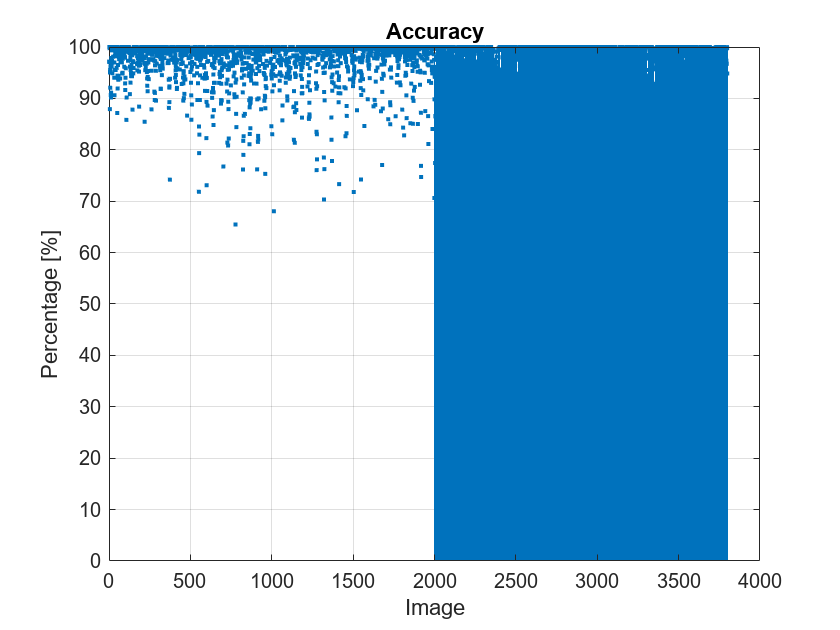

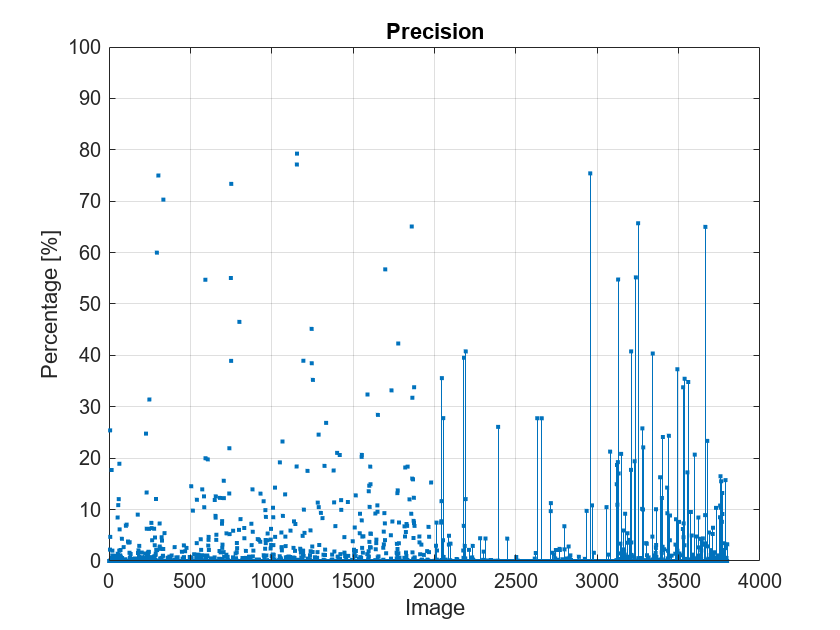


% Go through folder to compute stats
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels
% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count');
else

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Plots'), 'dir')
        mkdir(output_dir,'Plots');
    end

    % Plot statistics
    figure;
    stem(accuracy*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Accuracy");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Accuracy.png');
    saveas(gcf, output_file);% Save current figure
    close(gcf); % Close figure to avoid memory usage
    figure;
    stem(precision*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Precision");
    grid on;
    ylim([0 100]);
    output_file = fullfile(output_dir,'Plots','Precision.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(recall*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Recall");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Recall.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(f1_score*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("F1 Score");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','F1_Score.png');
    saveas(gcf, output_file);
    close(gcf);
end


overall_precision_hsv_sense_cas_no_closing = mean(precision)*100;
overall_recall_hsv_sense_cas_no_closing = mean(recall)*100;
overall_f1_score_hsv_sense_cas_no_closing = mean(f1_score)*100;
overall_accuracy_hsv_sense_cas_no_closing = mean(accuracy)*100;

% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- HSV Sense 5 Closing -----\n'); 
% Log data
fprintf(output_stats_id, 'Precision = %.5f\n', overall_precision_hsv_sense_cas_no_closing);
fprintf(output_stats_id, 'Recall = %.5f\n', overall_recall_hsv_sense_cas_no_closing);
fprintf(output_stats_id, 'F1-score = %.5f\n', overall_f1_score_hsv_sense_cas_no_closing);
fprintf(output_stats_id, 'Accuracy = %.5f\n', overall_accuracy_hsv_sense_cas_no_closing);
fprintf(output_stats_id, 'Duration of processing: %.1fs\n', elapsedTime);
% Close file
fclose(output_stats_id);

time_hsv_5_close = datetime('now')

time_hsv_5_close = datetime
   02-Apr-2025 03:41:04


save('C:\Users\andre\EE581-LandlideProj\src\classical_methods\Timing\time_hsv_5_close.mat', 'time_hsv_5_close');

% Clear workspace to save RAM
clear all;

### HSV Analysis - 7 Closing

#### CAS Dataset

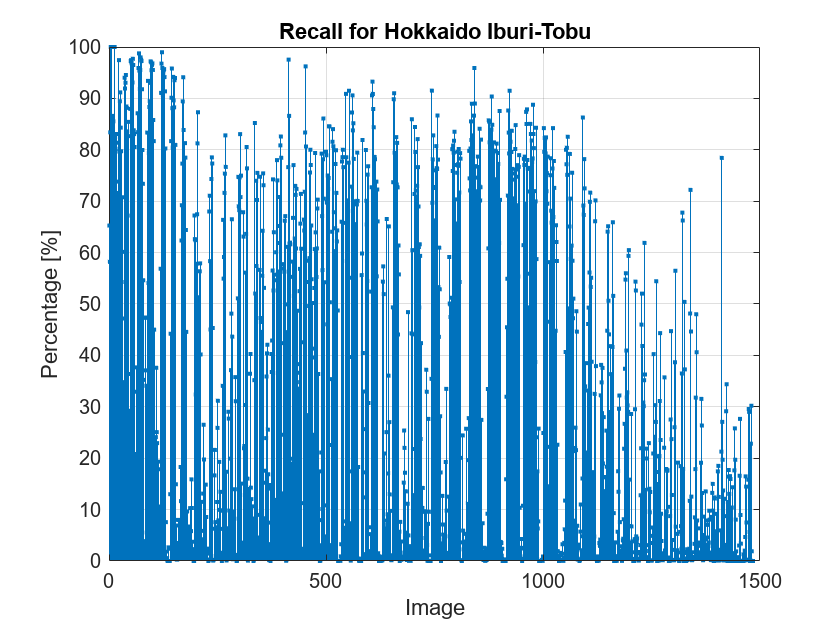

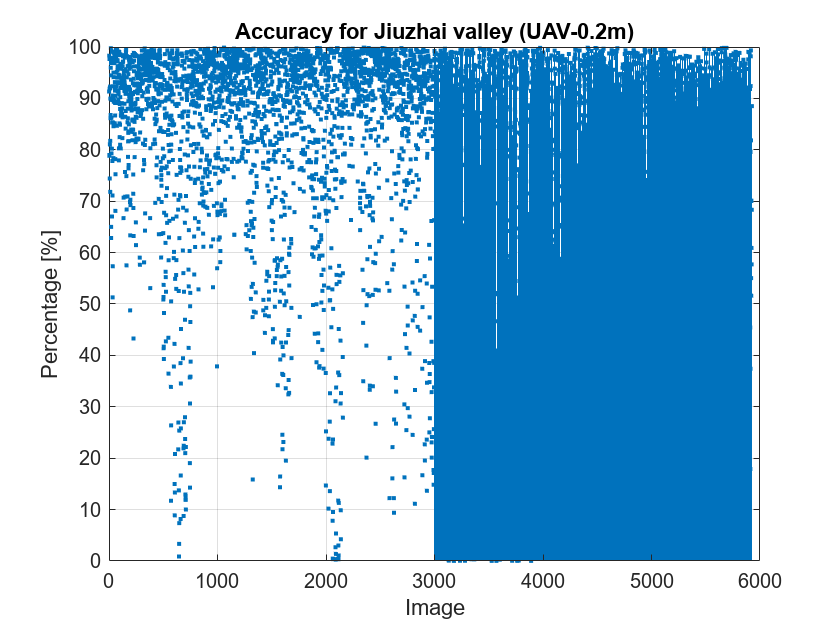

clc; clear; close all;
debug_mode = false;
imgs_proc = 0;

% Directories
orig_dir = 'C:\Users\andre\EE581-LandlideProj\data\original_dataset\';
output_dir = 'C:\Users\andre\EE581-LandlideProj\data\hsv_analysis\CAS\7_Closing';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\data\Stats_classical_methods.txt';

[folder_stats_dir, ~, ~] = fileparts(output_stats_dir);
% Create folder for stats outputs
if ~exist(fullfile(folder_stats_dir, 'dir'))
    mkdir(folder_stats_dir); % Create folder if doesn't exist
end

% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..', ...
    'Longxi River(UAV)','Tiburon Peninsula(Sentinel)'})); % Remove

% Set up stats storage
true_pos = cell(numel(folders),1); % Cell array - folder per row
false_pos = cell(numel(folders),1);
true_neg = cell(numel(folders),1);
false_neg = cell(numel(folders),1);
precision = cell(numel(folders),1);
recall = cell(numel(folders),1);
f1_score = cell(numel(folders),1);
accuracy = cell(numel(folders),1);
precision_per_set = cell(1,numel(folders));
recall_per_set = cell(1,numel(folders));
f1_score_per_set = cell(1,numel(folders));
accuracy_per_set = cell(1,numel(folders));

% Loop through each folder & assign zero array of its image count
for i=1:numel(folders)
    list_imgs = dir(fullfile(orig_dir, folders{i}, 'img', '*.tif')); % Get images
    list_lbls = dir(fullfile(orig_dir, folders{i}, 'label', '*.tif')); % Get images
    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else
        true_pos{i} = zeros(1,numel(list_imgs)); % Each cell contains image count
        false_pos{i} = zeros(1,numel(list_imgs));
        true_neg{i} = zeros(1,numel(list_imgs));
        false_neg{i} = zeros(1,numel(list_imgs));
        precision{i} = zeros(1,numel(list_imgs));
        recall{i} = zeros(1,numel(list_imgs));
        f1_score{i} = zeros(1,numel(list_imgs));
        accuracy{i} = zeros(1,numel(list_imgs));
    end
end

% Iterate through each folder
t1 = datetime('now');
for i=1:numel(folders)
    % Directory
    img_dir = fullfile(orig_dir, folders{i}, 'img');
    lbl_dir = fullfile(orig_dir, folders{i}, 'label');

    % Get list of image and label files
    list_imgs = dir(fullfile(img_dir, '*.tif'));
    list_lbls = dir(fullfile(lbl_dir, '*.tif'));
    
    % Create folder to output masks
    if ~exist(fullfile(output_dir,folders{i}), 'dir')
        mkdir(output_dir,folders{i}); % Create folder if doesn't exist
    end

    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else

        % Iterate through each image (and label) of each folder
        t2 = datetime('now');
        for k = 1:numel(list_imgs)
            imgs_proc = imgs_proc + 1;
            % Directory
            img_path = fullfile(img_dir, list_imgs(k).name);
            lbl_path = fullfile(lbl_dir, list_lbls(k).name);
    
            % Load data and label
            img = double(imread(img_path));
            label = double(imread(lbl_path));
    
            % Normalize images
            if max(img(:)) > 1
                img = img / max(img(:)); % Scale to [0, 1]
            end
            if max(label(:)) > 1
                label = label / max(label(:)); % Scale to [0, 1]
            end

            % Binarise the label and invert it so landslied is 1
            
            label_temp = label;
            label_temp(label_temp == 255) = 1;
            label_bin = (label_temp(:,:,1) + label_temp(:,:,2) + label_temp(:,:,3)) > 0;
            label = 1 - label_bin;    
            img_hsv = rgb2hsv(img);
    
            % Super sample - use interpolation to increase resolution
            scale_factor = 2;
            img_hsv = imresize(img_hsv, scale_factor, 'bicubic'); % Think bicubic is the best
        
            % Convert into HSV format and exctract CHs
            R_CH = img(:,:,1); % Red CH
            G_CH = img(:,:,2); % Green CH
            B_CH = img(:,:,3); % Blue CH
            H_CH = img_hsv(:,:,1); % Hue CH
            S_CH = img_hsv(:,:,2); % Saturation CH
            V_CH = img_hsv(:,:,3); % Value CH
        
            % Reduce contrast
            H_mask = H_CH;
            H_mask = histeq(H_mask);
            H_thresh = 0.85;
            H_mask_bin = H_mask >= H_thresh;
            V_mask = V_CH;
            V_mask = histeq(V_mask);
            V_thresh = 0.85;
            V_mask_bin = V_mask >= V_thresh;
        
            % Match areas where landslides could be
            Mask_HV = H_mask_bin & V_mask_bin;
        
            % Remove very small patches by assuming they are like 'salt and pepper' noise
            Mask_HV_denoised = medfilt2(Mask_HV, [3 3]);
            % Fill gaps where landslides could be and return image to normal size
            Mask_HV_denoised_close = imclose(Mask_HV_denoised, strel('disk', 7)); % Fill gaps
            % Return image to normal size
            mask = imresize(Mask_HV_denoised_close, [size(img,1), size(img,2)], 'nearest');
    
            % Statistcally analyse results
            true_pos{i}(k) = sum(label & mask, 'all');
            false_pos{i}(k) = sum(label & ~mask, 'all');
            true_neg{i}(k) = sum(~label & ~mask, 'all');
            false_neg{i}(k) = sum(~label & mask, 'all');
            accuracy{i}(k) = (true_pos{i}(k) + true_neg{i}(k)) / (true_pos{i}(k) + true_neg{i}(k) + false_pos{i}(k) + false_neg{i}(k));
            if (true_pos{i}(k) + false_pos{i}(k)) == 0
                precision{i}(k) = 0;
            else
                precision{i}(k) = true_pos{i}(k) / (true_pos{i}(k) + false_pos{i}(k));
            end
            if (true_pos{i}(k) + false_neg{i}(k)) == 0
                recall{i}(k) = 0;
            else
                recall{i}(k) = true_pos{i}(k) / (true_pos{i}(k) + false_neg{i}(k));
            end
            if (precision{i}(k) + recall{i}(k)) == 0
                f1_score{i}(k) = 0;
            else
                f1_score{i}(k) = (2 * precision{i}(k) * recall{i}(k)) / (precision{i}(k) + recall{i}(k));
            end

            output_file = fullfile(output_dir,folders{i},list_imgs(k).name);
            imwrite(mask,output_file);
        end
    end
    t3 = datetime('now');
    elapsedTime = seconds(t3-t2); % Cacluate elapsed times
    fprintf("%s --- Took %.1fs\n", folders{i} , elapsedTime);    
end
t3 = datetime('now');
elapsedTime = seconds(t3-t1); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

% Loop through each folder to compute stats
for i=1:numel(folders)
    list_imgs = dir(fullfile(orig_dir, folders{i}, 'img', '*.tif')); % Get images
    list_lbls = dir(fullfile(orig_dir, folders{i}, 'label', '*.tif')); % Get images
    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else
        % Create folder to output masks
        if ~exist(fullfile(output_dir,'Plots'), 'dir')
            mkdir(output_dir,'Plots');
        end
        %fprintf("For %s ||| Stats:\n", folders{i});

        % Calc stats per set
        precision_per_set{i} = mean((precision{i}));
        recall_per_set{i} = mean((recall{i}));
        f1_score_per_set{i} = mean((f1_score{i}));
        accuracy_per_set{i} = mean((accuracy{i}));
        
        % Plot statistics
        figure;
        stem(accuracy{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Accuracy for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Accuracy_%s.png',folders{i}));
        saveas(gcf, output_file);% Save current figure
        close(gcf); % Close figure to avoid memory usage
        figure;
        stem(precision{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Precision for %s", folders{i}))
        grid on;
        ylim([0 100]);
        output_file = fullfile(output_dir,'Plots',sprintf('Precision_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(recall{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Recall for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Recall_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(f1_score{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("F1 Score for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('F1_Score_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
    end
end


% Plot per set
figure;
stem(cell2mat(accuracy_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("Accuracy per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Accuracy.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(cell2mat(precision_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("Precision per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Precision.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(cell2mat(recall_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("Recall per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Recall.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(cell2mat(f1_score_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("F1 Score per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','F1_Score.png');
saveas(gcf, output_file);
close(gcf);

overall_precision_hsv_cas_no_closing = mean(cell2mat(precision_per_set))*100;
overall_recall_hsv_cas_no_closing = mean(cell2mat(recall_per_set))*100;
overall_f1_score_hsv_cas_no_closing = mean(cell2mat(f1_score_per_set))*100;
overall_accuracy_hsv_cas_no_closing = mean(cell2mat(accuracy_per_set))*100;

% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- HSV CAS 7 Closing -----\n'); 
% Log data
fprintf(output_stats_id, 'Precision = %.5f\n', overall_precision_hsv_cas_no_closing);
fprintf(output_stats_id, 'Recall = %.5f\n', overall_recall_hsv_cas_no_closing);
fprintf(output_stats_id, 'F1 score = %.5f\n', overall_f1_score_hsv_cas_no_closing);
fprintf(output_stats_id, 'Accuracy  = %.5f\n', overall_accuracy_hsv_cas_no_closing);
arr_precision_per_set = cell2mat(precision_per_set);
fprintf(output_stats_id, 'Precision per set: ');
fprintf(output_stats_id, '%.5f, ', arr_precision_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_precision_per_set(end));
arr_recall_per_set = cell2mat(recall_per_set);
fprintf(output_stats_id, 'Recall per set: ');
fprintf(output_stats_id, '%.5f, ', arr_recall_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_recall_per_set(end));
arr_f1_score_per_set = cell2mat(f1_score_per_set);
fprintf(output_stats_id, 'F1 score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_f1_score_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_f1_score_per_set(end));
arr_accuracy_per_set = cell2mat(accuracy_per_set);
fprintf(output_stats_id, 'Accuracy score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_accuracy_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_accuracy_per_set(end));
fprintf(output_stats_id, 'Duration of processing: %.1fs\n', elapsedTime);
% Close file
fclose(output_stats_id);

% Clear workspace to save RAM
clear all

#### Sense Dataset

clc; clear; close all;

imgs_proc = 0;

% Directories
orig_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\archive\TrainData\';
output_dir = 'C:\Users\andre\EE581-LandlideProj\data\hsv_analysis\Sense\5_Closing';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\data\Stats_classical_methods.txt';

[folder_stats_dir, ~, ~] = fileparts(output_stats_dir);
% Create folder for stats outputs
if ~exist(fullfile(folder_stats_dir, 'dir'))
    mkdir(folder_stats_dir); % Create folder if doesn't exist
end


% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..'})); % Remove

% Set up stats storage
% Assign zero array of its image count
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels
% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count');
else
    true_pos = zeros(1,numel(list_imgs));
    false_pos = zeros(1,numel(list_imgs));
    true_neg = zeros(1,numel(list_imgs));
    false_neg = zeros(1,numel(list_imgs));
    precision = zeros(1,numel(list_imgs));
    recall = zeros(1,numel(list_imgs));
    f1_score = zeros(1,numel(list_imgs));
    accuracy = zeros(1,numel(list_imgs));
end

% Go through through folder
t1 = datetime('now');
% Get list of image and label files
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels

% Create folder for all outputs
if ~exist(output_dir,'dir')
    mkdir(output_dir); % Create folder if doesn't exist
end

% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count for folder: %s', folders{i});
else
    % Iterate through each image (and label) of each folder
    t2 = datetime('now');

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Mask'),'dir')
        mkdir(output_dir,'Mask'); % Create folder if doesn't exist
    end

    for k = 1:numel(list_imgs)
        imgs_proc = imgs_proc + 1;
        % Full path
        img_path = fullfile(orig_dir, folders{1}, list_imgs(k).name);
        lbl_path = fullfile(orig_dir, folders{2}, list_lbls(k).name);

        % Read HDF5 data
        img_info = h5info(img_path);
        img_name = img_info.Datasets(1).Name;
        img_chs = h5read(img_path, ['/' img_name]);
            
        label_info = h5info(lbl_path);
        label_name = label_info.Datasets(1).Name;
        label = h5read(lbl_path, ['/' label_name]);

        % Binarise image
        label = label > 0;

        % Extract channels
        R_CH = squeeze(img_chs(4,:,:));
        G_CH = squeeze(img_chs(3,:,:));
        B_CH = squeeze(img_chs(2,:,:));

        % Combine into an RGB image & label
        img = double(cat(3, R_CH, G_CH, B_CH));
        
        % Normalize images
        if max(img(:)) > 1
            img = img / max(img(:)); % Scale to [0, 1]
        end
        
        img_hsv = rgb2hsv(img);
            
        % Super sample - use interpolation to increase resolution
        scale_factor = 2;
        img_hsv = imresize(img_hsv, scale_factor, 'bicubic'); % Think bicubic is the best
        
        % Convert into HSV format and exctract CHs
        H_CH = img_hsv(:,:,1); % Hue CH
        S_CH = img_hsv(:,:,2); % Saturation CH
        V_CH = img_hsv(:,:,3); % Value CH
        
        % Reduce contrast
        H_mask = H_CH;
        H_mask = histeq(H_mask);
        H_thresh = 0.85;
        H_mask_bin = H_mask >= H_thresh;
        V_mask = V_CH;
        V_mask = histeq(V_mask);
        V_thresh = 0.85;
        V_mask_bin = V_mask >= V_thresh;
        
        % Match areas where landslides could be
        Mask_HV = H_mask_bin & V_mask_bin;
        
        % Remove very small patches by assuming they are like 'salt and pepper' noise
        Mask_HV_denoised = medfilt2(Mask_HV, [3 3]);
        % Fill gaps where landslides could be and return image to normal size
        Mask_HV_denoised_close = imclose(Mask_HV_denoised, strel('disk', 7)); % Fill gaps
        % Return image to normal size
        mask = imresize(Mask_HV_denoised_close, [size(img,1), size(img,2)], 'nearest');
            
        % Statistcally analyse results
        true_pos(k) = sum(label & mask, 'all');
        false_pos(k) = sum(label & ~mask, 'all');
        true_neg(k) = sum(~label & ~mask, 'all');
        false_neg(k) = sum(~label & mask, 'all');
        accuracy(k) = (true_pos(k) + true_neg(k)) / (true_pos(k) + true_neg(k) + false_pos(k) + false_neg(k));
        if (true_pos(k) + false_pos(k)) == 0
            precision(k) = 0;
        else
            precision(k) = true_pos(k) / (true_pos(k) + false_pos(k));
        end
        if (true_pos(k) + false_neg(k)) == 0
            recall(k) = 0;
        else
            recall(k) = true_pos(k) / (true_pos(k) + false_neg(k));
        end
        if (precision(k) + recall(k)) == 0
            f1_score(k) = 0;
        else
            f1_score(k) = (2 * precision(k) * recall(k)) / (precision(k) + recall(k));
        end

        mask_name = split(list_imgs(k).name, '.');
        mask_name = [mask_name{1}, '.jpg'];
        output_file = fullfile(output_dir,'Mask',mask_name);
        imwrite(mask,output_file);
    end
end

t3 = datetime('now');
elapsedTime = seconds(t3-t1); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

Total processing time: 151.3s

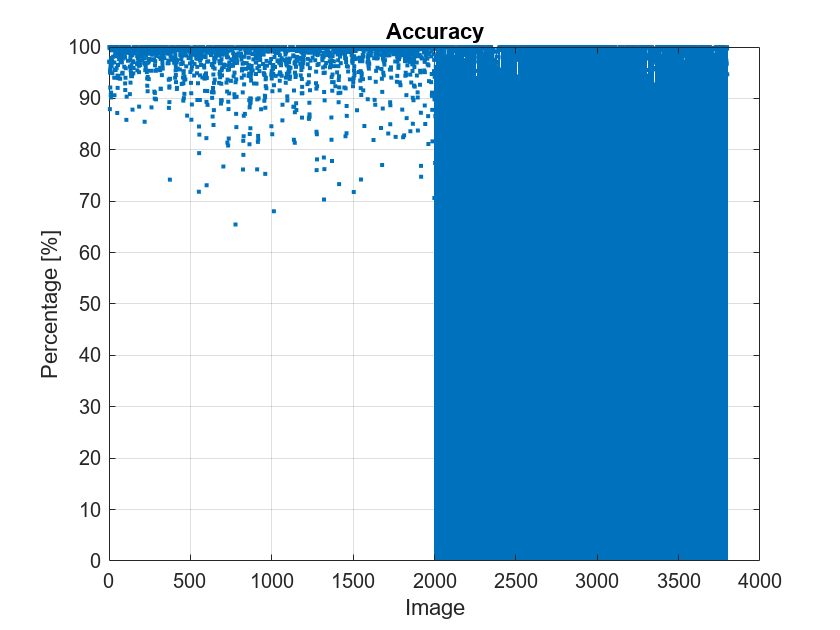

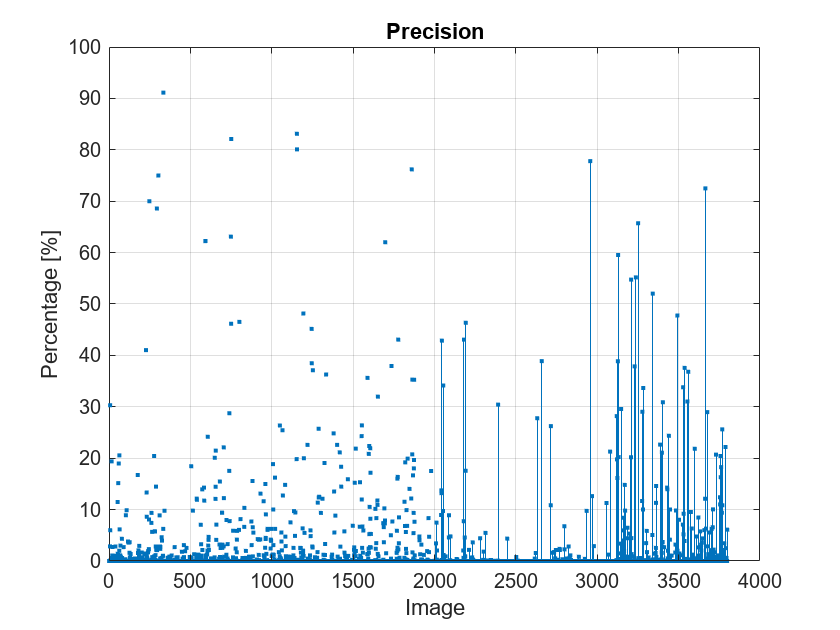

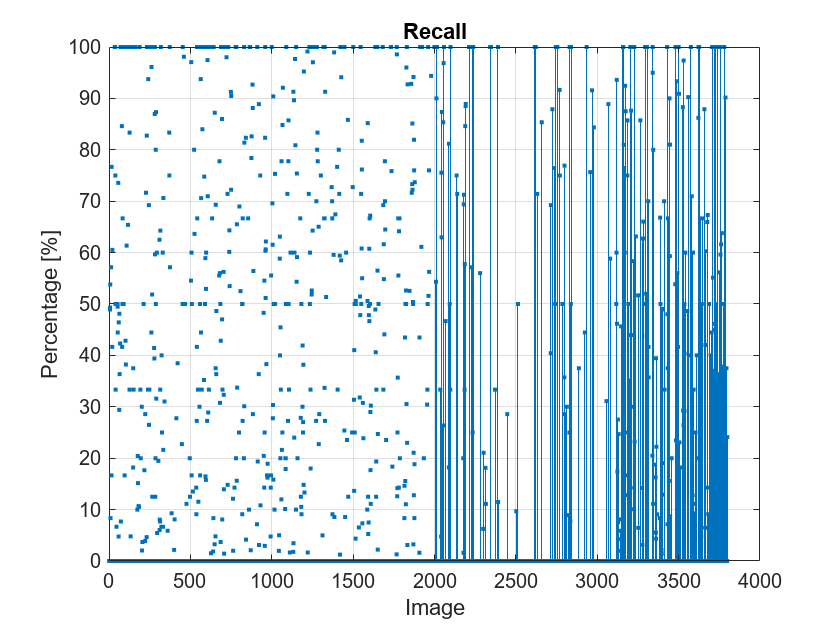


% Go through folder to compute stats
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels
% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count');
else

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Plots'), 'dir')
        mkdir(output_dir,'Plots');
    end

    % Plot statistics
    figure;
    stem(accuracy*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Accuracy");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Accuracy.png');
    saveas(gcf, output_file);% Save current figure
    close(gcf); % Close figure to avoid memory usage
    figure;
    stem(precision*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Precision");
    grid on;
    ylim([0 100]);
    output_file = fullfile(output_dir,'Plots','Precision.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(recall*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Recall");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Recall.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(f1_score*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("F1 Score");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','F1_Score.png');
    saveas(gcf, output_file);
    close(gcf);
end


overall_precision_hsv_sense_cas_no_closing = mean(precision)*100;
overall_recall_hsv_sense_cas_no_closing = mean(recall)*100;
overall_f1_score_hsv_sense_cas_no_closing = mean(f1_score)*100;
overall_accuracy_hsv_sense_cas_no_closing = mean(accuracy)*100;

% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- HSV Sense 7 Closing -----\n'); 
% Log data
fprintf(output_stats_id, 'Precision = %.5f\n', overall_precision_hsv_sense_cas_no_closing);
fprintf(output_stats_id, 'Recall = %.5f\n', overall_recall_hsv_sense_cas_no_closing);
fprintf(output_stats_id, 'F1-score = %.5f\n', overall_f1_score_hsv_sense_cas_no_closing);
fprintf(output_stats_id, 'Accuracy = %.5f\n', overall_accuracy_hsv_sense_cas_no_closing);
fprintf(output_stats_id, 'Duration of processing: %.1fs\n', elapsedTime);
% Close file
fclose(output_stats_id);

time_hsv_7_close = datetime('now')

time_hsv_7_close = datetime
   02-Apr-2025 04:10:45


save('C:\Users\andre\EE581-LandlideProj\src\classical_methods\Timing\time_hsv_7_close.mat', 'time_hsv_7_close');

% Clear workspace to save RAM
clear all;

### Green quantise - No Morphology

#### CAS Dataset

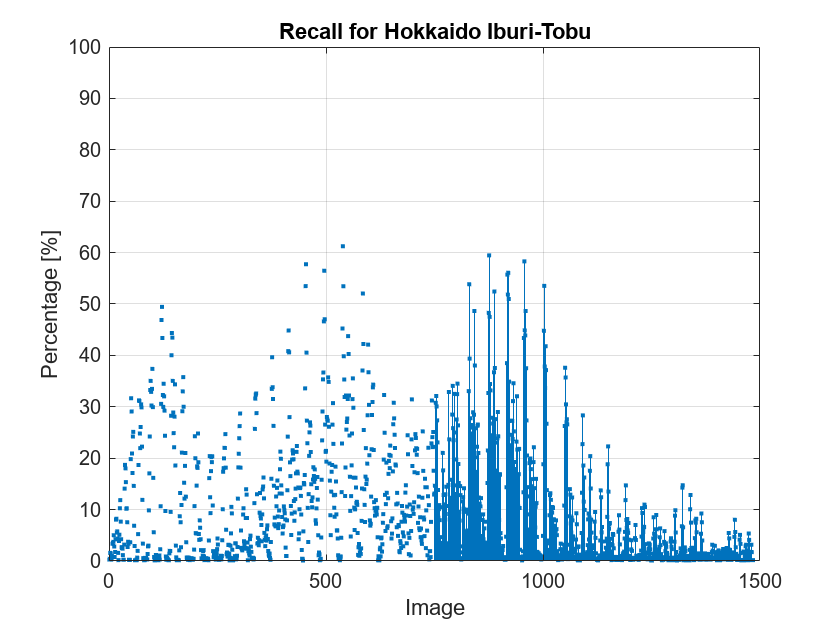

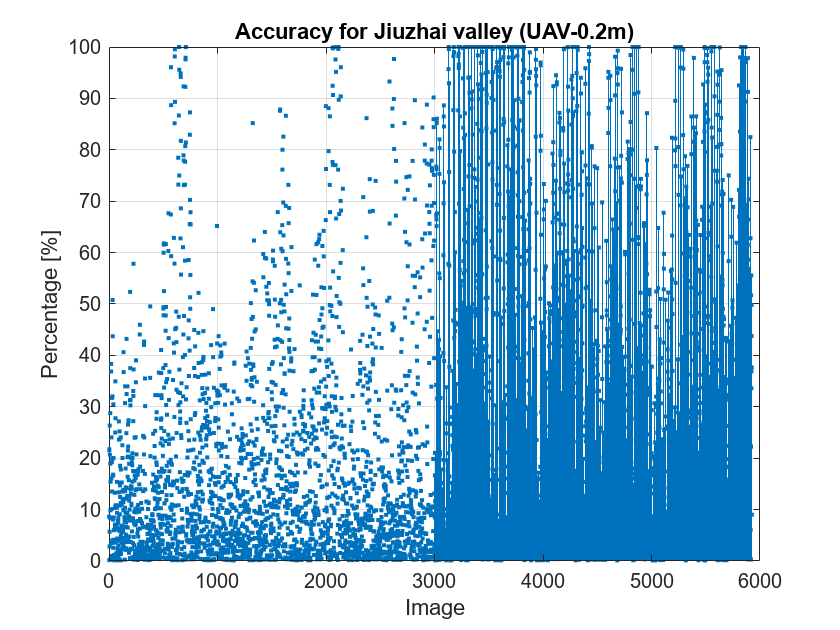

clc; clear; close all;

imgs_proc = 0;

% Directories
orig_dir = 'C:\Users\andre\EE581-LandlideProj\data\original_dataset\';
output_dir = 'C:\Users\andre\EE581-LandlideProj\data\green_quant_filtering\CAS\No_Morphology';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\data\Stats_classical_methods.txt';

[folder_stats_dir, ~, ~] = fileparts(output_stats_dir);
% Create folder for stats outputs
if ~exist(fullfile(folder_stats_dir, 'dir'))
    mkdir(folder_stats_dir); % Create folder if doesn't exist
end

% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..', ...
    'Longxi River(UAV)','Tiburon Peninsula(Sentinel)'})); % Remove

% Set up stats storage
true_pos = cell(numel(folders),1); % Cell array - folder per row
false_pos = cell(numel(folders),1);
true_neg = cell(numel(folders),1);
false_neg = cell(numel(folders),1);
precision = cell(numel(folders),1);
recall = cell(numel(folders),1);
f1_score = cell(numel(folders),1);
accuracy = cell(numel(folders),1);
precision_per_set = cell(1,numel(folders));
recall_per_set = cell(1,numel(folders));
f1_score_per_set = cell(1,numel(folders));
accuracy_per_set = cell(1,numel(folders));

% Loop through each folder & assign zero array of its image count
for i=1:numel(folders)
    list_imgs = dir(fullfile(orig_dir, folders{i}, 'img', '*.tif')); % Get images
    list_lbls = dir(fullfile(orig_dir, folders{i}, 'label', '*.tif')); % Get images
    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else
        true_pos{i} = zeros(1,numel(list_imgs)); % Each cell contains image count
        false_pos{i} = zeros(1,numel(list_imgs));
        true_neg{i} = zeros(1,numel(list_imgs));
        false_neg{i} = zeros(1,numel(list_imgs));
        precision{i} = zeros(1,numel(list_imgs));
        recall{i} = zeros(1,numel(list_imgs));
        f1_score{i} = zeros(1,numel(list_imgs));
        accuracy{i} = zeros(1,numel(list_imgs));
    end
end

% Iterate through each folder
t1 = datetime('now');
for i=1:numel(folders)
    % Directory
    img_dir = fullfile(orig_dir, folders{i}, 'img');
    lbl_dir = fullfile(orig_dir, folders{i}, 'label');

    % Get list of image and label files
    list_imgs = dir(fullfile(img_dir, '*.tif'));
    list_lbls = dir(fullfile(lbl_dir, '*.tif'));
    
    % Create folder to output masks
    if ~exist(fullfile(output_dir,folders{i}), 'dir')
        mkdir(output_dir,folders{i}); % Create folder if doesn't exist
    end

    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else

        % Iterate through each image (and label) of each folder
        t2 = datetime('now');
        for k = 1:numel(list_imgs)
            imgs_proc = imgs_proc + 1;
            % Directory
            img_path = fullfile(img_dir, list_imgs(k).name);
            lbl_path = fullfile(lbl_dir, list_lbls(k).name);
    
            % Load data and label
            img = double(imread(img_path));
            label = double(imread(lbl_path));
    
            % Normalize images
            if max(img(:)) > 1
                img = img / max(img(:)); % Scale to [0, 1]
            end
            if max(label(:)) > 1
                label = label / max(label(:)); % Scale to [0, 1]
            end

            % Binarise the label and invert it so landslied is 1
            
            label_temp = label;
            label_temp(label_temp == 255) = 1;
            label_bin = (label_temp(:,:,1) + label_temp(:,:,2) + label_temp(:,:,3)) > 0;
            label = 1 - label_bin;    
            
            % Exctract CHs
            R_CH = img(:,:,1); % Red CH
            G_CH = img(:,:,2); % Green CH
            B_CH = img(:,:,3); % Blue CH

            % Enhance G plane contrast
            R_eq = histeq(R_CH);
            G_eq = histeq(G_CH);
            B_eq = histeq(B_CH);
            img_enhance = cat(3,R_eq,G_eq,B_eq);
        
            % Apply quant to reduce #CH of unique RGB values
            levels = 1; % Controll blockiness (higher = smoother)
            quant = 256 / levels;
            G_quantized = round(G_eq / quant) * quant;
            img_green_quant = img;
            img_green_quant(:,:,2) = G_quantized; % Replace CH w/ quantised version
        
            % Preserve sharp edges whilst removing (most) green
            img_gray = rgb2gray(img_green_quant); % Convert to grayscale
            im_edges = edge(img_gray,'Canny'); % Detect edges
            
            G_quant = img_green_quant(:,:,2); % Create G plane mask
            green_mask = (G_quant > 0.5 * img_green_quant(:,:,1)) & (G_quant> 1.1 * img_green_quant(:,:,3)) & (G_quant > 200);
            
            green_mask(im_edges) = 0; % Preserve edges (keep intact) whilst removing G plane
            img_no_green = img_green_quant;
            img_no_green(repmat(green_mask, [1,1,3])) = 0; 
            
            img_thresh = img_no_green;
            img_thresh(img_thresh<250) = 0;
            img_inv = 255 - img_thresh;
            
            % Create mask
            img_gray = rgb2gray(img_inv); % Convert to gray scale - black areas have low intensity
            mask = img_gray < 20; % Adjust threshold - keep only black regions (binary mask)
            
            % Statistcally analyse results
            true_pos{i}(k) = sum(label & mask, 'all');
            false_pos{i}(k) = sum(label & ~mask, 'all');
            true_neg{i}(k) = sum(~label & ~mask, 'all');
            false_neg{i}(k) = sum(~label & mask, 'all');
            accuracy{i}(k) = (true_pos{i}(k) + true_neg{i}(k)) / (true_pos{i}(k) + true_neg{i}(k) + false_pos{i}(k) + false_neg{i}(k));
            if (true_pos{i}(k) + false_pos{i}(k)) == 0
                precision{i}(k) = 0;
            else
                precision{i}(k) = true_pos{i}(k) / (true_pos{i}(k) + false_pos{i}(k));
            end
            if (true_pos{i}(k) + false_neg{i}(k)) == 0
                recall{i}(k) = 0;
            else
                recall{i}(k) = true_pos{i}(k) / (true_pos{i}(k) + false_neg{i}(k));
            end
            if (precision{i}(k) + recall{i}(k)) == 0
                f1_score{i}(k) = 0;
            else
                f1_score{i}(k) = (2 * precision{i}(k) * recall{i}(k)) / (precision{i}(k) + recall{i}(k));
            end

            output_file = fullfile(output_dir,folders{i},list_imgs(k).name);
            imwrite(mask,output_file);
        end
    end
    t3 = datetime('now');
    elapsedTime = seconds(t3-t2); % Cacluate elapsed times
    fprintf("%s --- Took %.1fs\n", folders{i} , elapsedTime);    
end
t3 = datetime('now');
elapsedTime = seconds(t3-t1); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

% Loop through each folder to compute stats
for i=1:numel(folders)
    list_imgs = dir(fullfile(orig_dir, folders{i}, 'img', '*.tif')); % Get images
    list_lbls = dir(fullfile(orig_dir, folders{i}, 'label', '*.tif')); % Get images
    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else
        % Create folder to output masks
        if ~exist(fullfile(output_dir,'Plots'), 'dir')
            mkdir(output_dir,'Plots');
        end
        %fprintf("For %s ||| Stats:\n", folders{i});

        % Calc stats per set
        precision_per_set{i} = mean((precision{i}));
        recall_per_set{i} = mean((recall{i}));
        f1_score_per_set{i} = mean((f1_score{i}));
        accuracy_per_set{i} = mean((accuracy{i}));
        
        % Plot statistics
        figure;
        stem(accuracy{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Accuracy for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Accuracy_%s.png',folders{i}));
        saveas(gcf, output_file);% Save current figure
        close(gcf); % Close figure to avoid memory usage
        figure;
        stem(precision{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Precision for %s", folders{i}))
        grid on;
        ylim([0 100]);
        output_file = fullfile(output_dir,'Plots',sprintf('Precision_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(recall{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Recall for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Recall_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(f1_score{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("F1 Score for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('F1_Score_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
    end
end


% Plot sets
figure;
stem(cell2mat(accuracy_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("Accuracy per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Accuracy.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(cell2mat(precision_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("Precision per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Precision.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(cell2mat(recall_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("Recall per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Recall.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(cell2mat(f1_score_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("F1 Score per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','F1_Score.png');
saveas(gcf, output_file);
close(gcf);

overall_precision_gq_cas = mean(cell2mat(precision_per_set))*100;
overall_recall_gq_cas = mean(cell2mat(recall_per_set))*100;
overall_f1_score_gq_cas = mean(cell2mat(f1_score_per_set))*100;
overall_accuracy_gq_cas = mean(cell2mat(accuracy_per_set))*100;

% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- Green Quantisation CAS No Morphology -----\n'); 
% Log data
fprintf(output_stats_id, 'Precision = %.5f\n', overall_precision_gq_cas);
fprintf(output_stats_id, 'Recall = %.5f\n', overall_recall_gq_cas);
fprintf(output_stats_id, 'F1-score = %.5f\n', overall_f1_score_gq_cas);
fprintf(output_stats_id, 'Accuracy = %.5f\n', overall_accuracy_gq_cas);
arr_precision_per_set = cell2mat(precision_per_set);
fprintf(output_stats_id, 'Precision per set: ');
fprintf(output_stats_id, '%.5f, ', arr_precision_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_precision_per_set(end));
arr_recall_per_set = cell2mat(recall_per_set);
fprintf(output_stats_id, 'Recall per set: ');
fprintf(output_stats_id, '%.5f, ', arr_recall_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_recall_per_set(end));
arr_f1_score_per_set = cell2mat(f1_score_per_set);
fprintf(output_stats_id, 'F1 score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_f1_score_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_f1_score_per_set(end));
arr_accuracy_per_set = cell2mat(accuracy_per_set);
fprintf(output_stats_id, 'Accuracy score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_accuracy_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_accuracy_per_set(end));
fprintf(output_stats_id, 'Duration of processing: %.1fs\n', elapsedTime);
% Close file
fclose(output_stats_id);

% Clear workspace to save RAM
clear all

#### Sense Dataset

clc; clear; close all;

imgs_proc = 0;

% Directories
orig_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\archive\TrainData\';
output_dir = 'C:\Users\andre\EE581-LandlideProj\data\green_quant_filtering\Sense\No_Morphology';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\data\Stats_classical_methods.txt';

[folder_stats_dir, ~, ~] = fileparts(output_stats_dir);
% Create folder for stats outputs
if ~exist(fullfile(folder_stats_dir, 'dir'))
    mkdir(folder_stats_dir); % Create folder if doesn't exist
end


% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..'})); % Remove

% Set up stats storage
% Assign zero array of its image count
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels
% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count');
else
    true_pos = zeros(1,numel(list_imgs));
    false_pos = zeros(1,numel(list_imgs));
    true_neg = zeros(1,numel(list_imgs));
    false_neg = zeros(1,numel(list_imgs));
    precision = zeros(1,numel(list_imgs));
    recall = zeros(1,numel(list_imgs));
    f1_score = zeros(1,numel(list_imgs));
    accuracy = zeros(1,numel(list_imgs));
end

% Go through through folder
t1 = datetime('now');
% Get list of image and label files
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels

% Create folder for all outputs
if ~exist(output_dir,'dir')
    mkdir(output_dir); % Create folder if doesn't exist
end

% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count for folder: %s', folders{i});
else
    % Iterate through each image (and label) of each folder
    t2 = datetime('now');

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Mask'),'dir')
        mkdir(output_dir,'Mask'); % Create folder if doesn't exist
    end

    for k = 1:numel(list_imgs)
        imgs_proc = imgs_proc + 1;
        % Full path
        img_path = fullfile(orig_dir, folders{1}, list_imgs(k).name);
        lbl_path = fullfile(orig_dir, folders{2}, list_lbls(k).name);

        % Read HDF5 data
        img_info = h5info(img_path);
        img_name = img_info.Datasets(1).Name;
        img_chs = h5read(img_path, ['/' img_name]);
            
        label_info = h5info(lbl_path);
        label_name = label_info.Datasets(1).Name;
        label = h5read(lbl_path, ['/' label_name]);

        % Binarise image
        label = label > 0;

        % Extract channels
        R_CH = squeeze(img_chs(4,:,:));
        G_CH = squeeze(img_chs(3,:,:));
        B_CH = squeeze(img_chs(2,:,:));

        % Combine into an RGB image & label
        img = double(cat(3, R_CH, G_CH, B_CH));
        
        % Normalize images
        if max(img(:)) > 1
            img = img / max(img(:)); % Scale to [0, 1]
        end
        
        % Enhance G plane contrast
        R_eq = histeq(R_CH);
        G_eq = histeq(G_CH);
        B_eq = histeq(B_CH);
        img_enhance = cat(3,R_eq,G_eq,B_eq);

        % Apply quant to reduce #CH of unique RGB values
        levels = 1; % Controll blockiness (higher = smoother)
        quant = 256 / levels;
        G_quantized = round(G_eq / quant) * quant;
        img_green_quant = img;
        img_green_quant(:,:,2) = G_quantized; % Replace CH w/ quantised version

        % Preserve sharp edges whilst removing (most) green
        img_gray = rgb2gray(img_green_quant); % Convert to grayscale
        im_edges = edge(img_gray,'Canny'); % Detect edges

        G_quant = img_green_quant(:,:,2); % Create G plane mask
        green_mask = (G_quant > 0.5 * img_green_quant(:,:,1)) & (G_quant> 1.1 * img_green_quant(:,:,3)) & (G_quant > 200);

        green_mask(im_edges) = 0; % Preserve edges (keep intact) whilst removing G plane
        img_no_green = img_green_quant;
        img_no_green(repmat(green_mask, [1,1,3])) = 0;

        %histogram(img_no_green);
        img_thresh = img_no_green;
        img_thresh(img_thresh<250) = 0;
        img_inv = 255 - img_thresh;

        % Create mask
        img_gray = rgb2gray(img_inv); % Convert to gray scale - black areas have low intensity
        mask = img_gray < 20; % Adjust threshold - keep only black regions (binary mask)
        
        % Statistcally analyse results
        true_pos(k) = sum(label & mask, 'all');
        false_pos(k) = sum(label & ~mask, 'all');
        true_neg(k) = sum(~label & ~mask, 'all');
        false_neg(k) = sum(~label & mask, 'all');
        accuracy(k) = (true_pos(k) + true_neg(k)) / (true_pos(k) + true_neg(k) + false_pos(k) + false_neg(k));
        if (true_pos(k) + false_pos(k)) == 0
            precision(k) = 0;
        else
            precision(k) = true_pos(k) / (true_pos(k) + false_pos(k));
        end
        if (true_pos(k) + false_neg(k)) == 0
            recall(k) = 0;
        else
            recall(k) = true_pos(k) / (true_pos(k) + false_neg(k));
        end
        if (precision(k) + recall(k)) == 0
            f1_score(k) = 0;
        else
            f1_score(k) = (2 * precision(k) * recall(k)) / (precision(k) + recall(k));
        end

        mask_name = split(list_imgs(k).name, '.');
        mask_name = [mask_name{1}, '.jpg'];
        output_file = fullfile(output_dir,'Mask',mask_name);
        imwrite(mask,output_file);
    end
end

t3 = datetime('now');
elapsedTime = seconds(t3-t1); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

Total processing time: 124.1s

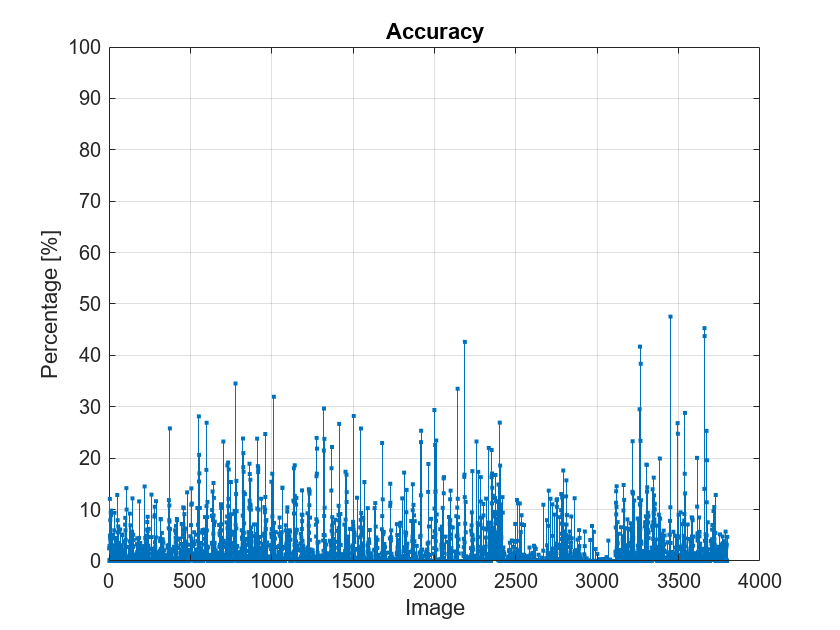

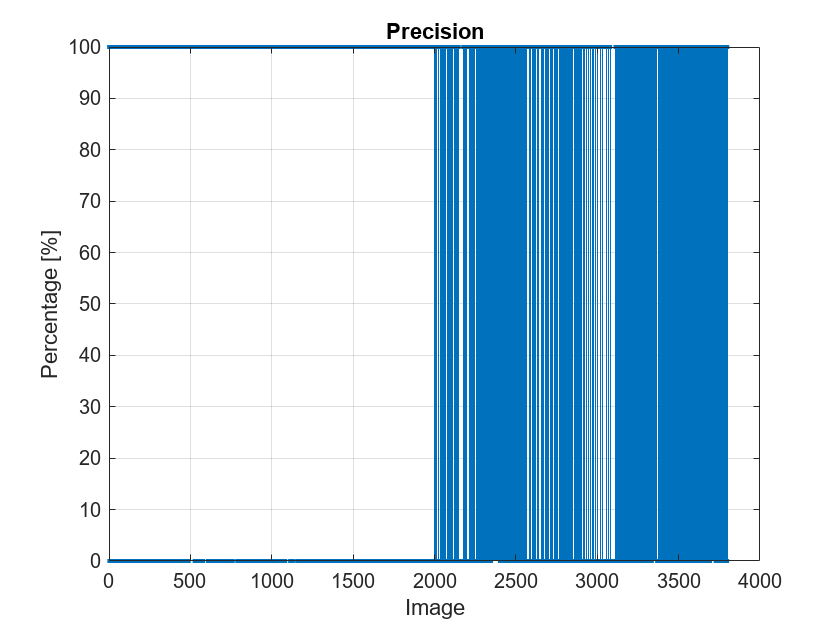

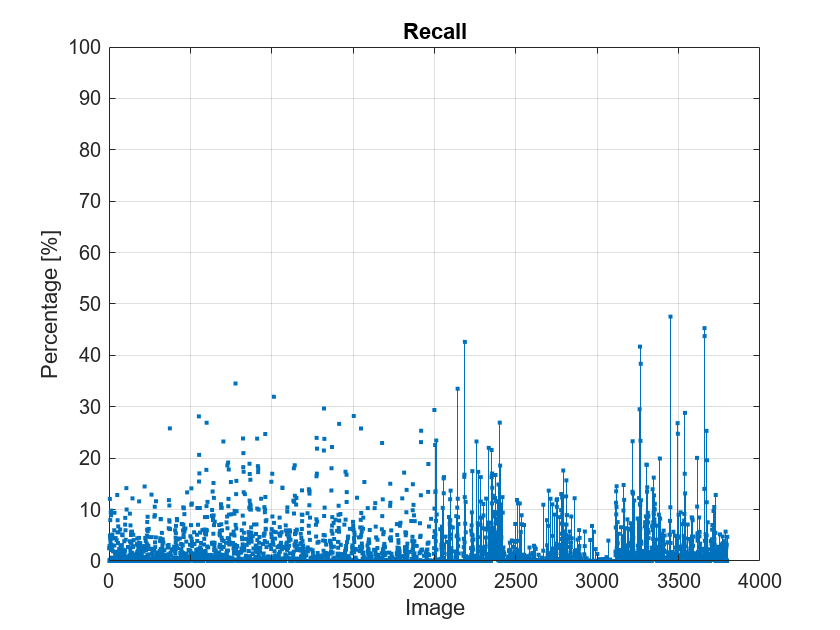


% Go through folder to compute stats
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels
% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count');
else

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Plots'), 'dir')
        mkdir(output_dir,'Plots');
    end

    % Plot statistics
    figure;
    stem(accuracy*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Accuracy");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Accuracy.png');
    saveas(gcf, output_file);% Save current figure
    close(gcf); % Close figure to avoid memory usage
    figure;
    stem(precision*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Precision");
    grid on;
    ylim([0 100]);
    output_file = fullfile(output_dir,'Plots','Precision.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(recall*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Recall");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Recall.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(f1_score*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("F1 Score");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','F1_Score.png');
    saveas(gcf, output_file);
    close(gcf); 
end


overall_precision_gq_sense_cas_no_closing = mean(precision)*100;
overall_recall_gq_sense_cas_no_closing = mean(recall)*100;
overall_f1_score_gq_sense_cas_no_closing = mean(f1_score)*100;
overall_accuracy_gq_sense_cas_no_closing = mean(accuracy)*100;

% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- Green Quantisation Sense No Morphology -----\n'); 
% Log data
fprintf(output_stats_id, 'Precision = %.5f\n', overall_precision_gq_sense_cas_no_closing);
fprintf(output_stats_id, 'Recall = %.5f\n', overall_recall_gq_sense_cas_no_closing);
fprintf(output_stats_id, 'F1-score = %.5f\n', overall_f1_score_gq_sense_cas_no_closing);
fprintf(output_stats_id, 'Accuracy = %.5f\n', overall_accuracy_gq_sense_cas_no_closing);
fprintf(output_stats_id, 'Duration of processing: %.1fs\n', elapsedTime);
% Close file
fclose(output_stats_id);

time_gq_no_morph = datetime('now')

time_gq_no_morph = datetime
   02-Apr-2025 11:55:25


save('C:\Users\andre\EE581-LandlideProj\src\classical_methods\Timing\time_gq_no_morph.mat', 'time_gq_no_morph');

% Clear workspace to save RAM
clear all;

### Superpixel - No Morphology

#### CAS Dataset

clc; clear; close all;

imgs_proc = 0;

% Directories
orig_dir = 'C:\Users\andre\EE581-LandlideProj\data\original_dataset\';
output_dir = 'C:\Users\andre\EE581-LandlideProj\data\superpixel_analysis\CAS\No_Morphology';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\data\Stats_classical_methods.txt';

[folder_stats_dir, ~, ~] = fileparts(output_stats_dir);
% Create folder for stats outputs
if ~exist(fullfile(folder_stats_dir, 'dir'))
    mkdir(folder_stats_dir); % Create folder if doesn't exist
end


% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..', ...
    'Longxi River(UAV)','Tiburon Peninsula(Sentinel)'})); % Remove

% Set up stats storage
true_pos = cell(numel(folders),1); % Cell array - folder per row
false_pos = cell(numel(folders),1);
true_neg = cell(numel(folders),1);
false_neg = cell(numel(folders),1);
precision = cell(numel(folders),1);
recall = cell(numel(folders),1);
f1_score = cell(numel(folders),1);
accuracy = cell(numel(folders),1);
precision_per_set = cell(1,numel(folders));
recall_per_set = cell(1,numel(folders));
f1_score_per_set = cell(1,numel(folders));
accuracy_per_set = cell(1,numel(folders));

% Loop through each folder & assign zero array of its image count
for i=1:numel(folders)
    list_imgs = dir(fullfile(orig_dir, folders{i}, 'img', '*.tif')); % Get images
    list_lbls = dir(fullfile(orig_dir, folders{i}, 'label', '*.tif')); % Get images
    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else
        true_pos{i} = zeros(1,numel(list_imgs)); % Each cell contains image count
        false_pos{i} = zeros(1,numel(list_imgs));
        true_neg{i} = zeros(1,numel(list_imgs));
        false_neg{i} = zeros(1,numel(list_imgs));
        precision{i} = zeros(1,numel(list_imgs));
        recall{i} = zeros(1,numel(list_imgs));
        f1_score{i} = zeros(1,numel(list_imgs));
        accuracy{i} = zeros(1,numel(list_imgs));
    end
end

% Iterate through each folder
t1 = datetime('now');
for i=1:numel(folders)
    % Directory
    img_dir = fullfile(orig_dir, folders{i}, 'img');
    lbl_dir = fullfile(orig_dir, folders{i}, 'label');

    % Get list of image and label files
    list_imgs = dir(fullfile(img_dir, '*.tif'));
    list_lbls = dir(fullfile(lbl_dir, '*.tif'));
    
    % Create folder to output masks
    if ~exist(fullfile(output_dir,folders{i}), 'dir')
        mkdir(output_dir,folders{i}); % Create folder if doesn't exist
    end

    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else

        % Iterate through each image (and label) of each folder
        t2 = datetime('now');
        for k = 1:numel(list_imgs)
            imgs_proc = imgs_proc + 1;
            % Directory
            img_path = fullfile(img_dir, list_imgs(k).name);
            lbl_path = fullfile(lbl_dir, list_lbls(k).name);
    
            % Load data and label
            img = double(imread(img_path));
            label = double(imread(lbl_path));
    
            % Normalize images
            if max(img(:)) > 1
                img = img / max(img(:)); % Scale to [0, 1]
            end
            if max(label(:)) > 1
                label = label / max(label(:)); % Scale to [0, 1]
            end

            % Binarise the label and invert it so landslied is 1
            
            label_temp = label;
            label_temp(label_temp == 255) = 1;
            label_bin = (label_temp(:,:,1) + label_temp(:,:,2) + label_temp(:,:,3)) > 0;
            label = 1 - label_bin;    
            
            % Calculate superpixels of the image.
            [L,N] = superpixels(img,500);
            output_image = zeros(size(img),'like',img);
            idx = label2idx(L);
            num_rows = size(img,1);
            num_cols = size(img,2);
            for label_val = 1:N
                red_idx = idx{label_val};
                green_idx = idx{label_val}+num_rows*num_cols;
                blue_idx = idx{label_val}+2*num_rows*num_cols;
                output_image(red_idx) = mean(img(red_idx));
                output_image(green_idx) = mean(img(green_idx));
                output_image(blue_idx) = mean(img(blue_idx));
            end    
            mask = im2gray(output_image);
            mask = (mask > 0.8);

            % Statistcally analyse results
            true_pos{i}(k) = sum(label & mask, 'all');
            false_pos{i}(k) = sum(label & ~mask, 'all');
            true_neg{i}(k) = sum(~label & ~mask, 'all');
            false_neg{i}(k) = sum(~label & mask, 'all');
            accuracy{i}(k) = (true_pos{i}(k) + true_neg{i}(k)) / (true_pos{i}(k) + true_neg{i}(k) + false_pos{i}(k) + false_neg{i}(k));
            if (true_pos{i}(k) + false_pos{i}(k)) == 0
                precision{i}(k) = 0;
            else
                precision{i}(k) = true_pos{i}(k) / (true_pos{i}(k) + false_pos{i}(k));
            end
            if (true_pos{i}(k) + false_neg{i}(k)) == 0
                recall{i}(k) = 0;
            else
                recall{i}(k) = true_pos{i}(k) / (true_pos{i}(k) + false_neg{i}(k));
            end
            if (precision{i}(k) + recall{i}(k)) == 0
                f1_score{i}(k) = 0;
            else
                f1_score{i}(k) = (2 * precision{i}(k) * recall{i}(k)) / (precision{i}(k) + recall{i}(k));
            end

            output_file = fullfile(output_dir,folders{i},list_imgs(k).name);
            imwrite(mask,output_file);
        end
    end
    t3 = datetime('now');
    elapsedTime = seconds(t3-t2); % Cacluate elapsed times
    fprintf("%s --- Took %.1fs\n", folders{i} , elapsedTime);    
end

Hokkaido Iburi-Tobu --- Took 322.7s


t3 = datetime('now');
elapsedTime = seconds(t3-t1); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

% Loop through each folder to compute stats
for i=1:numel(folders)
    list_imgs = dir(fullfile(orig_dir, folders{i}, 'img', '*.tif')); % Get images
    list_lbls = dir(fullfile(orig_dir, folders{i}, 'label', '*.tif')); % Get images
    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else
        % Create folder to output masks
        if ~exist(fullfile(output_dir,'Plots'), 'dir')
            mkdir(output_dir,'Plots');
        end
        %fprintf("For %s ||| Stats:\n", folders{i});

        % Calc stats per set
        precision_per_set{i} = mean((precision{i}));
        recall_per_set{i} = mean((recall{i}));
        f1_score_per_set{i} = mean((f1_score{i}));
        accuracy_per_set{i} = mean((accuracy{i}));
        
        % Plot statistics
        figure;
        stem(accuracy{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Accuracy for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Accuracy_%s.png',folders{i}));
        saveas(gcf, output_file);% Save current figure
        close(gcf); % Close figure to avoid memory usage
        figure;
        stem(precision{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Precision for %s", folders{i}))
        grid on;
        ylim([0 100]);
        output_file = fullfile(output_dir,'Plots',sprintf('Precision_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(recall{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Recall for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Recall_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(f1_score{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("F1 Score for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('F1_Score_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
    end
end

% Plot sets
figure;
stem(cell2mat(accuracy_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("Accuracy per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Accuracy.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(cell2mat(precision_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("Precision per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Precision.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(cell2mat(recall_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("Recall per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Recall.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(cell2mat(f1_score_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("F1 Score per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','F1_Score.png');
saveas(gcf, output_file);
close(gcf);

overall_precision_sp_cas = mean(cell2mat(precision_per_set))*100;
overall_recall_sp_cas = mean(cell2mat(recall_per_set))*100;
overall_f1_score_sp_cas = mean(cell2mat(f1_score_per_set))*100;
overall_accuracy_sp_cas = mean(cell2mat(accuracy_per_set))*100;
% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- Superpixel CAS No Morphology -----\n'); 
% Log data
fprintf(output_stats_id, 'Precision = %.5f\n', overall_precision_sp_cas);
fprintf(output_stats_id, 'Recall = %.5f\n', overall_recall_sp_cas);
fprintf(output_stats_id, 'F1-score = %.5f\n', overall_f1_score_sp_cas);
fprintf(output_stats_id, 'Accuracy = %.5f\n', overall_accuracy_sp_cas);
arr_precision_per_set = cell2mat(precision_per_set);
fprintf(output_stats_id, 'Precision per set: ');
fprintf(output_stats_id, '%.5f, ', arr_precision_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_precision_per_set(end));
arr_recall_per_set = cell2mat(recall_per_set);
fprintf(output_stats_id, 'Recall per set: ');
fprintf(output_stats_id, '%.5f, ', arr_recall_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_recall_per_set(end));
arr_f1_score_per_set = cell2mat(f1_score_per_set);
fprintf(output_stats_id, 'F1 score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_f1_score_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_f1_score_per_set(end));
arr_accuracy_per_set = cell2mat(accuracy_per_set);
fprintf(output_stats_id, 'Accuracy score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_accuracy_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_accuracy_per_set(end));
% Close file
fclose(output_stats_id);

% Clear workspace to save RAM
clear all

#### Sense Dataset

clc; clear; close all;

imgs_proc = 0;

% Directories
orig_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\archive\TrainData\';
output_dir = 'C:\Users\andre\EE581-LandlideProj\data\superpixel_analysis\Sense\No_Morphology';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\data\Stats_classical_methods.txt';

[folder_stats_dir, ~, ~] = fileparts(output_stats_dir)
% Create folder for stats outputs
if ~exist(fullfile(folder_stats_dir, 'dir'))
    mkdir(folder_stats_dir); % Create folder if doesn't exist
end

% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..'})); % Remove

% Set up stats storage
% Assign zero array of its image count
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels
% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count');
else
    true_pos = zeros(1,numel(list_imgs));
    false_pos = zeros(1,numel(list_imgs));
    true_neg = zeros(1,numel(list_imgs));
    false_neg = zeros(1,numel(list_imgs));
    precision = zeros(1,numel(list_imgs));
    recall = zeros(1,numel(list_imgs));
    f1_score = zeros(1,numel(list_imgs));
    accuracy = zeros(1,numel(list_imgs));
end

% Go through through folder
t1 = datetime('now');
% Get list of image and label files
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels

% Create folder for all outputs
if ~exist(output_dir,'dir')
    mkdir(output_dir); % Create folder if doesn't exist
end

% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count for folder: %s', folders{i});
else
    % Iterate through each image (and label) of each folder
    t2 = datetime('now');

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Mask'),'dir')
        mkdir(output_dir,'Mask'); % Create folder if doesn't exist
    end

    for k = 1:numel(list_imgs)
        imgs_proc = imgs_proc + 1;
        % Full path
        img_path = fullfile(orig_dir, folders{1}, list_imgs(k).name);
        lbl_path = fullfile(orig_dir, folders{2}, list_lbls(k).name);

        % Read HDF5 data
        img_info = h5info(img_path);
        img_name = img_info.Datasets(1).Name;
        img_chs = h5read(img_path, ['/' img_name]);
            
        label_info = h5info(lbl_path);
        label_name = label_info.Datasets(1).Name;
        label = h5read(lbl_path, ['/' label_name]);

        % Binarise image
        label = label > 0;

        % Extract channels
        R_CH = squeeze(img_chs(4,:,:));
        G_CH = squeeze(img_chs(3,:,:));
        B_CH = squeeze(img_chs(2,:,:));

        % Combine into an RGB image & label
        img = double(cat(3, R_CH, G_CH, B_CH));
        
        % Normalize images
        if max(img(:)) > 1
            img = img / max(img(:)); % Scale to [0, 1]
        end
        
        % Calculate superpixels of the image.
        [L,N] = superpixels(img,500);
        output_image = zeros(size(img),'like',img);
        idx = label2idx(L);
        num_rows = size(img,1);
        num_cols = size(img,2);
        for label_val = 1:N
            red_idx = idx{label_val};
            green_idx = idx{label_val}+num_rows*num_cols;
            blue_idx = idx{label_val}+2*num_rows*num_cols;
            output_image(red_idx) = mean(img(red_idx));
            output_image(green_idx) = mean(img(green_idx));
            output_image(blue_idx) = mean(img(blue_idx));
        end
        mask = im2gray(output_image);
        mask = (mask > 0.8);

        % Statistcally analyse results
        true_pos(k) = sum(label & mask, 'all');
        false_pos(k) = sum(label & ~mask, 'all');
        true_neg(k) = sum(~label & ~mask, 'all');
        false_neg(k) = sum(~label & mask, 'all');
        accuracy(k) = (true_pos(k) + true_neg(k)) / (true_pos(k) + true_neg(k) + false_pos(k) + false_neg(k));
        if (true_pos(k) + false_pos(k)) == 0
            precision(k) = 0;
        else
            precision(k) = true_pos(k) / (true_pos(k) + false_pos(k));
        end
        if (true_pos(k) + false_neg(k)) == 0
            recall(k) = 0;
        else
            recall(k) = true_pos(k) / (true_pos(k) + false_neg(k));
        end
        if (precision(k) + recall(k)) == 0
            f1_score(k) = 0;
        else
            f1_score(k) = (2 * precision(k) * recall(k)) / (precision(k) + recall(k));
        end

        mask_name = split(list_imgs(k).name, '.');
        mask_name = [mask_name{1}, '.jpg'];
        output_file = fullfile(output_dir,'Mask',mask_name);
        imwrite(mask,output_file);
    end
end

t3 = datetime('now');
elapsedTime = seconds(t3-t1); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

% Go through folder to compute stats
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels
% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count');
else

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Plots'), 'dir')
        mkdir(output_dir,'Plots');
    end

    % Plot statistics
    figure;
    stem(accuracy*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Accuracy");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Accuracy.png');
    saveas(gcf, output_file);% Save current figure
    close(gcf); % Close figure to avoid memory usage
    figure;
    stem(precision*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Precision");
    grid on;
    ylim([0 100]);
    output_file = fullfile(output_dir,'Plots','Precision.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(recall*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Recall");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Recall.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(f1_score*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("F1 Score");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','F1_Score.png');
    saveas(gcf, output_file);
    close(gcf); 
end

overall_precision_sp_sense_cas_no_closing = mean(precision)*100;
overall_recall_sp_sense_cas_no_closing = mean(recall)*100;
overall_f1_score_sp_sense_cas_no_closing = mean(f1_score)*100;
overall_accuracy_sp_sense_cas_no_closing = mean(accuracy)*100;

% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- Superpixel Sense No Morphology -----\n'); 
% Log data
fprintf(output_stats_id, 'Precision = %.5f\n', overall_precision_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'Recall = %.5f\n', overall_recall_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'F1-score = %.5f\n', overall_f1_score_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'Accuracy = %.5f\n', overall_accuracy_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'Duration of processing: %.1fs\n', elapsedTime);
% Close file
fclose(output_stats_id);

time_sp_no_morph = datetime('now')
save('C:\Users\andre\EE581-LandlideProj\src\classical_methods\Timing\time_sp_no_morph.mat', 'time_sp_no_morph');

% Clear workspace to save RAM
clear all;

### Superpixel - 5 Opening

#### CAS Dataset

clc; clear; close all;

imgs_proc = 0;

% Directories
orig_dir = 'C:\Users\andre\EE581-LandlideProj\data\original_dataset\';
output_dir = 'C:\Users\andre\EE581-LandlideProj\data\superpixel_analysis\CAS\5_Opening';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\data\Stats_classical_methods.txt';

[folder_stats_dir, ~, ~] = fileparts(output_stats_dir);
% Create folder for stats outputs
if ~exist(fullfile(folder_stats_dir, 'dir'))
    mkdir(folder_stats_dir); % Create folder if doesn't exist
end

% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..', ...
    'Longxi River(UAV)','Tiburon Peninsula(Sentinel)'})); % Remove

% Set up stats storage
true_pos = cell(numel(folders),1); % Cell array - folder per row
false_pos = cell(numel(folders),1);
true_neg = cell(numel(folders),1);
false_neg = cell(numel(folders),1);
precision = cell(numel(folders),1);
recall = cell(numel(folders),1);
f1_score = cell(numel(folders),1);
accuracy = cell(numel(folders),1);
precision_per_set = cell(1,numel(folders));
recall_per_set = cell(1,numel(folders));
f1_score_per_set = cell(1,numel(folders));
accuracy_per_set = cell(1,numel(folders));

% Loop through each folder & assign zero array of its image count
for i=1:numel(folders)
    list_imgs = dir(fullfile(orig_dir, folders{i}, 'img', '*.tif')); % Get images
    list_lbls = dir(fullfile(orig_dir, folders{i}, 'label', '*.tif')); % Get images
    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else
        true_pos{i} = zeros(1,numel(list_imgs)); % Each cell contains image count
        false_pos{i} = zeros(1,numel(list_imgs));
        true_neg{i} = zeros(1,numel(list_imgs));
        false_neg{i} = zeros(1,numel(list_imgs));
        precision{i} = zeros(1,numel(list_imgs));
        recall{i} = zeros(1,numel(list_imgs));
        f1_score{i} = zeros(1,numel(list_imgs));
        accuracy{i} = zeros(1,numel(list_imgs));
    end
end

% Iterate through each folder
t1 = datetime('now');
for i=1:numel(folders)
    % Directory
    img_dir = fullfile(orig_dir, folders{i}, 'img');
    lbl_dir = fullfile(orig_dir, folders{i}, 'label');

    % Get list of image and label files
    list_imgs = dir(fullfile(img_dir, '*.tif'));
    list_lbls = dir(fullfile(lbl_dir, '*.tif'));
    
    % Create folder to output masks
    if ~exist(fullfile(output_dir,folders{i}), 'dir')
        mkdir(output_dir,folders{i}); % Create folder if doesn't exist
    end

    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else

        % Iterate through each image (and label) of each folder
        t2 = datetime('now');
        for k = 1:numel(list_imgs)
            imgs_proc = imgs_proc + 1;
            % Directory
            img_path = fullfile(img_dir, list_imgs(k).name);
            lbl_path = fullfile(lbl_dir, list_lbls(k).name);
    
            % Load data and label
            img = double(imread(img_path));
            label = double(imread(lbl_path));
    
            % Normalize images
            if max(img(:)) > 1
                img = img / max(img(:)); % Scale to [0, 1]
            end
            if max(label(:)) > 1
                label = label / max(label(:)); % Scale to [0, 1]
            end

            % Binarise the label and invert it so landslied is 1
            
            label_temp = label;
            label_temp(label_temp == 255) = 1;
            label_bin = (label_temp(:,:,1) + label_temp(:,:,2) + label_temp(:,:,3)) > 0;
            label = 1 - label_bin;    
            
            % Calculate superpixels of the image.
            [L,N] = superpixels(img,500);
            output_image = zeros(size(img),'like',img);
            idx = label2idx(L);
            num_rows = size(img,1);
            num_cols = size(img,2);
            for label_val = 1:N
                red_idx = idx{label_val};
                green_idx = idx{label_val}+num_rows*num_cols;
                blue_idx = idx{label_val}+2*num_rows*num_cols;
                output_image(red_idx) = mean(img(red_idx));
                output_image(green_idx) = mean(img(green_idx));
                output_image(blue_idx) = mean(img(blue_idx));
            end    
            mask = im2gray(output_image);
            mask = (mask > 0.8);
            mask = imopen(mask, strel('disk', 5)); % Fill gaps

            % Statistcally analyse results
            true_pos{i}(k) = sum(label & mask, 'all');
            false_pos{i}(k) = sum(label & ~mask, 'all');
            true_neg{i}(k) = sum(~label & ~mask, 'all');
            false_neg{i}(k) = sum(~label & mask, 'all');
            accuracy{i}(k) = (true_pos{i}(k) + true_neg{i}(k)) / (true_pos{i}(k) + true_neg{i}(k) + false_pos{i}(k) + false_neg{i}(k));
            if (true_pos{i}(k) + false_pos{i}(k)) == 0
                precision{i}(k) = 0;
            else
                precision{i}(k) = true_pos{i}(k) / (true_pos{i}(k) + false_pos{i}(k));
            end
            if (true_pos{i}(k) + false_neg{i}(k)) == 0
                recall{i}(k) = 0;
            else
                recall{i}(k) = true_pos{i}(k) / (true_pos{i}(k) + false_neg{i}(k));
            end
            if (precision{i}(k) + recall{i}(k)) == 0
                f1_score{i}(k) = 0;
            else
                f1_score{i}(k) = (2 * precision{i}(k) * recall{i}(k)) / (precision{i}(k) + recall{i}(k));
            end

            output_file = fullfile(output_dir,folders{i},list_imgs(k).name);
            imwrite(mask,output_file);
        end
    end
    t3 = datetime('now');
    elapsedTime = seconds(t3-t2); % Cacluate elapsed times
    fprintf("%s --- Took %.1fs\n", folders{i} , elapsedTime);    
end
t3 = datetime('now');
elapsedTime = seconds(t3-t1); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

% Loop through each folder to compute stats
for i=1:numel(folders)
    list_imgs = dir(fullfile(orig_dir, folders{i}, 'img', '*.tif')); % Get images
    list_lbls = dir(fullfile(orig_dir, folders{i}, 'label', '*.tif')); % Get images
    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else
        % Create folder to output masks
        if ~exist(fullfile(output_dir,'Plots'), 'dir')
            mkdir(output_dir,'Plots');
        end
        %fprintf("For %s ||| Stats:\n", folders{i});

        % Calc stats per set
        precision_per_set{i} = mean((precision{i}));
        recall_per_set{i} = mean((recall{i}));
        f1_score_per_set{i} = mean((f1_score{i}));
        accuracy_per_set{i} = mean((accuracy{i}));
        
        % Plot statistics
        figure;
        stem(accuracy{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Accuracy for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Accuracy_%s.png',folders{i}));
        saveas(gcf, output_file);% Save current figure
        close(gcf); % Close figure to avoid memory usage
        figure;
        stem(precision{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Precision for %s", folders{i}))
        grid on;
        ylim([0 100]);
        output_file = fullfile(output_dir,'Plots',sprintf('Precision_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(recall{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Recall for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Recall_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(f1_score{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("F1 Score for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('F1_Score_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
    end
end

% Plot sets
figure;
stem(cell2mat(accuracy_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("Accuracy per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Accuracy.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(cell2mat(precision_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("Precision per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Precision.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(cell2mat(recall_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("Recall per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Recall.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(cell2mat(f1_score_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("F1 Score per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','F1_Score.png');
saveas(gcf, output_file);
close(gcf);

overall_precision_sp_cas = mean(cell2mat(precision_per_set))*100;
overall_recall_sp_cas = mean(cell2mat(recall_per_set))*100;
overall_f1_score_sp_cas = mean(cell2mat(f1_score_per_set))*100;
overall_accuracy_sp_cas = mean(cell2mat(accuracy_per_set))*100;
% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- Superpixel CAS 5 Opening -----\n'); 
% Log data
fprintf(output_stats_id, 'Precision = %.5f\n', overall_precision_sp_cas);
fprintf(output_stats_id, 'Recall = %.5f\n', overall_recall_sp_cas);
fprintf(output_stats_id, 'F1-score = %.5f\n', overall_f1_score_sp_cas);
fprintf(output_stats_id, 'Accuracy = %.5f\n', overall_accuracy_sp_cas);
arr_precision_per_set = cell2mat(precision_per_set);
fprintf(output_stats_id, 'Precision per set: ');
fprintf(output_stats_id, '%.5f, ', arr_precision_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_precision_per_set(end));
arr_recall_per_set = cell2mat(recall_per_set);
fprintf(output_stats_id, 'Recall per set: ');
fprintf(output_stats_id, '%.5f, ', arr_recall_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_recall_per_set(end));
arr_f1_score_per_set = cell2mat(f1_score_per_set);
fprintf(output_stats_id, 'F1 score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_f1_score_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_f1_score_per_set(end));
arr_accuracy_per_set = cell2mat(accuracy_per_set);
fprintf(output_stats_id, 'Accuracy score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_accuracy_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_accuracy_per_set(end));
% Close file
fclose(output_stats_id);

% Clear workspace to save RAM
clear all

#### Sense Dataset

clc; clear; close all;

imgs_proc = 0;

% Directories
orig_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\archive\TrainData\';
output_dir = 'C:\Users\andre\EE581-LandlideProj\data\superpixel_analysis\Sense\5_Opening';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\data\Stats_classical_methods.txt';

[folder_stats_dir, ~, ~] = fileparts(output_stats_dir)
% Create folder for stats outputs
if ~exist(fullfile(folder_stats_dir, 'dir'))
    mkdir(folder_stats_dir); % Create folder if doesn't exist
end

% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..'})); % Remove

% Set up stats storage
% Assign zero array of its image count
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels
% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count');
else
    true_pos = zeros(1,numel(list_imgs));
    false_pos = zeros(1,numel(list_imgs));
    true_neg = zeros(1,numel(list_imgs));
    false_neg = zeros(1,numel(list_imgs));
    precision = zeros(1,numel(list_imgs));
    recall = zeros(1,numel(list_imgs));
    f1_score = zeros(1,numel(list_imgs));
    accuracy = zeros(1,numel(list_imgs));
end

% Go through through folder
t1 = datetime('now');
% Get list of image and label files
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels

% Create folder for all outputs
if ~exist(output_dir,'dir')
    mkdir(output_dir); % Create folder if doesn't exist
end

% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count for folder: %s', folders{i});
else
    % Iterate through each image (and label) of each folder
    t2 = datetime('now');

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Mask'),'dir')
        mkdir(output_dir,'Mask'); % Create folder if doesn't exist
    end

    for k = 1:numel(list_imgs)
        imgs_proc = imgs_proc + 1;
        % Full path
        img_path = fullfile(orig_dir, folders{1}, list_imgs(k).name);
        lbl_path = fullfile(orig_dir, folders{2}, list_lbls(k).name);

        % Read HDF5 data
        img_info = h5info(img_path);
        img_name = img_info.Datasets(1).Name;
        img_chs = h5read(img_path, ['/' img_name]);
            
        label_info = h5info(lbl_path);
        label_name = label_info.Datasets(1).Name;
        label = h5read(lbl_path, ['/' label_name]);

        % Binarise image
        label = label > 0;

        % Extract channels
        R_CH = squeeze(img_chs(4,:,:));
        G_CH = squeeze(img_chs(3,:,:));
        B_CH = squeeze(img_chs(2,:,:));

        % Combine into an RGB image & label
        img = double(cat(3, R_CH, G_CH, B_CH));
        
        % Normalize images
        if max(img(:)) > 1
            img = img / max(img(:)); % Scale to [0, 1]
        end
        
        % Calculate superpixels of the image.
        [L,N] = superpixels(img,500);
        output_image = zeros(size(img),'like',img);
        idx = label2idx(L);
        num_rows = size(img,1);
        num_cols = size(img,2);
        for label_val = 1:N
            red_idx = idx{label_val};
            green_idx = idx{label_val}+num_rows*num_cols;
            blue_idx = idx{label_val}+2*num_rows*num_cols;
            output_image(red_idx) = mean(img(red_idx));
            output_image(green_idx) = mean(img(green_idx));
            output_image(blue_idx) = mean(img(blue_idx));
        end
        mask = im2gray(output_image);
        mask = (mask > 0.8);
        mask = imopen(mask, strel('disk', 5)); % Fill gaps

        % Statistcally analyse results
        true_pos(k) = sum(label & mask, 'all');
        false_pos(k) = sum(label & ~mask, 'all');
        true_neg(k) = sum(~label & ~mask, 'all');
        false_neg(k) = sum(~label & mask, 'all');
        accuracy(k) = (true_pos(k) + true_neg(k)) / (true_pos(k) + true_neg(k) + false_pos(k) + false_neg(k));
        if (true_pos(k) + false_pos(k)) == 0
            precision(k) = 0;
        else
            precision(k) = true_pos(k) / (true_pos(k) + false_pos(k));
        end
        if (true_pos(k) + false_neg(k)) == 0
            recall(k) = 0;
        else
            recall(k) = true_pos(k) / (true_pos(k) + false_neg(k));
        end
        if (precision(k) + recall(k)) == 0
            f1_score(k) = 0;
        else
            f1_score(k) = (2 * precision(k) * recall(k)) / (precision(k) + recall(k));
        end

        mask_name = split(list_imgs(k).name, '.');
        mask_name = [mask_name{1}, '.jpg'];
        output_file = fullfile(output_dir,'Mask',mask_name);
        imwrite(mask,output_file);
    end
end

t3 = datetime('now');
elapsedTime = seconds(t3-t1); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

% Go through folder to compute stats
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels
% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count');
else

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Plots'), 'dir')
        mkdir(output_dir,'Plots');
    end

    % Plot statistics
    figure;
    stem(accuracy*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Accuracy");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Accuracy.png');
    saveas(gcf, output_file);% Save current figure
    close(gcf); % Close figure to avoid memory usage
    figure;
    stem(precision*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Precision");
    grid on;
    ylim([0 100]);
    output_file = fullfile(output_dir,'Plots','Precision.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(recall*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Recall");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Recall.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(f1_score*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("F1 Score");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','F1_Score.png');
    saveas(gcf, output_file);
    close(gcf); 
end

overall_precision_sp_sense_cas_no_closing = mean(precision)*100;
overall_recall_sp_sense_cas_no_closing = mean(recall)*100;
overall_f1_score_sp_sense_cas_no_closing = mean(f1_score)*100;
overall_accuracy_sp_sense_cas_no_closing = mean(accuracy)*100;

% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- Superpixel Sense 5 Opening -----\n'); 
% Log data
fprintf(output_stats_id, 'Precision = %.5f\n', overall_precision_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'Recall = %.5f\n', overall_recall_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'F1-score = %.5f\n', overall_f1_score_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'Accuracy = %.5f\n', overall_accuracy_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'Duration of processing: %.1fs\n', elapsedTime);
% Close file
fclose(output_stats_id);

time_sp_5_open = datetime('now')
save('C:\Users\andre\EE581-LandlideProj\src\classical_methods\Timing\time_sp_5_open.mat', 'time_sp_5_open');

% Clear workspace to save RAM
clear all;

### Superpixel - 7 Opening

#### CAS Dataset

clc; clear; close all;

imgs_proc = 0;

% Directories
orig_dir = 'C:\Users\andre\EE581-LandlideProj\data\original_dataset\';
output_dir = 'C:\Users\andre\EE581-LandlideProj\data\superpixel_analysis\CAS\7_Opening';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\data\Stats_classical_methods.txt';

[folder_stats_dir, ~, ~] = fileparts(output_stats_dir);
% Create folder for stats outputs
if ~exist(fullfile(folder_stats_dir, 'dir'))
    mkdir(folder_stats_dir); % Create folder if doesn't exist
end

% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..', ...
    'Longxi River(UAV)','Tiburon Peninsula(Sentinel)'})); % Remove

% Set up stats storage
true_pos = cell(numel(folders),1); % Cell array - folder per row
false_pos = cell(numel(folders),1);
true_neg = cell(numel(folders),1);
false_neg = cell(numel(folders),1);
precision = cell(numel(folders),1);
recall = cell(numel(folders),1);
f1_score = cell(numel(folders),1);
accuracy = cell(numel(folders),1);
precision_per_set = cell(1,numel(folders));
recall_per_set = cell(1,numel(folders));
f1_score_per_set = cell(1,numel(folders));
accuracy_per_set = cell(1,numel(folders));

% Loop through each folder & assign zero array of its image count
for i=1:numel(folders)
    list_imgs = dir(fullfile(orig_dir, folders{i}, 'img', '*.tif')); % Get images
    list_lbls = dir(fullfile(orig_dir, folders{i}, 'label', '*.tif')); % Get images
    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else
        true_pos{i} = zeros(1,numel(list_imgs)); % Each cell contains image count
        false_pos{i} = zeros(1,numel(list_imgs));
        true_neg{i} = zeros(1,numel(list_imgs));
        false_neg{i} = zeros(1,numel(list_imgs));
        precision{i} = zeros(1,numel(list_imgs));
        recall{i} = zeros(1,numel(list_imgs));
        f1_score{i} = zeros(1,numel(list_imgs));
        accuracy{i} = zeros(1,numel(list_imgs));
    end
end

% Iterate through each folder
t1 = datetime('now');
for i=1:numel(folders)
    % Directory
    img_dir = fullfile(orig_dir, folders{i}, 'img');
    lbl_dir = fullfile(orig_dir, folders{i}, 'label');

    % Get list of image and label files
    list_imgs = dir(fullfile(img_dir, '*.tif'));
    list_lbls = dir(fullfile(lbl_dir, '*.tif'));
    
    % Create folder to output masks
    if ~exist(fullfile(output_dir,folders{i}), 'dir')
        mkdir(output_dir,folders{i}); % Create folder if doesn't exist
    end

    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else

        % Iterate through each image (and label) of each folder
        t2 = datetime('now');
        for k = 1:numel(list_imgs)
            imgs_proc = imgs_proc + 1;
            % Directory
            img_path = fullfile(img_dir, list_imgs(k).name);
            lbl_path = fullfile(lbl_dir, list_lbls(k).name);
    
            % Load data and label
            img = double(imread(img_path));
            label = double(imread(lbl_path));
    
            % Normalize images
            if max(img(:)) > 1
                img = img / max(img(:)); % Scale to [0, 1]
            end
            if max(label(:)) > 1
                label = label / max(label(:)); % Scale to [0, 1]
            end

            % Binarise the label and invert it so landslied is 1
            
            label_temp = label;
            label_temp(label_temp == 255) = 1;
            label_bin = (label_temp(:,:,1) + label_temp(:,:,2) + label_temp(:,:,3)) > 0;
            label = 1 - label_bin;    
            
            % Calculate superpixels of the image.
            [L,N] = superpixels(img,500);
            output_image = zeros(size(img),'like',img);
            idx = label2idx(L);
            num_rows = size(img,1);
            num_cols = size(img,2);
            for label_val = 1:N
                red_idx = idx{label_val};
                green_idx = idx{label_val}+num_rows*num_cols;
                blue_idx = idx{label_val}+2*num_rows*num_cols;
                output_image(red_idx) = mean(img(red_idx));
                output_image(green_idx) = mean(img(green_idx));
                output_image(blue_idx) = mean(img(blue_idx));
            end    
            mask = im2gray(output_image);
            mask = (mask > 0.8);
            mask = imopen(mask, strel('disk', 7)); % Fill gaps

            % Statistcally analyse results
            true_pos{i}(k) = sum(label & mask, 'all');
            false_pos{i}(k) = sum(label & ~mask, 'all');
            true_neg{i}(k) = sum(~label & ~mask, 'all');
            false_neg{i}(k) = sum(~label & mask, 'all');
            accuracy{i}(k) = (true_pos{i}(k) + true_neg{i}(k)) / (true_pos{i}(k) + true_neg{i}(k) + false_pos{i}(k) + false_neg{i}(k));
            if (true_pos{i}(k) + false_pos{i}(k)) == 0
                precision{i}(k) = 0;
            else
                precision{i}(k) = true_pos{i}(k) / (true_pos{i}(k) + false_pos{i}(k));
            end
            if (true_pos{i}(k) + false_neg{i}(k)) == 0
                recall{i}(k) = 0;
            else
                recall{i}(k) = true_pos{i}(k) / (true_pos{i}(k) + false_neg{i}(k));
            end
            if (precision{i}(k) + recall{i}(k)) == 0
                f1_score{i}(k) = 0;
            else
                f1_score{i}(k) = (2 * precision{i}(k) * recall{i}(k)) / (precision{i}(k) + recall{i}(k));
            end

            output_file = fullfile(output_dir,folders{i},list_imgs(k).name);
            imwrite(mask,output_file);
        end
    end
    t3 = datetime('now');
    elapsedTime = seconds(t3-t2); % Cacluate elapsed times
    fprintf("%s --- Took %.1fs\n", folders{i} , elapsedTime);    
end
t3 = datetime('now');
elapsedTime = seconds(t3-t1); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

% Loop through each folder to compute stats
for i=1:numel(folders)
    list_imgs = dir(fullfile(orig_dir, folders{i}, 'img', '*.tif')); % Get images
    list_lbls = dir(fullfile(orig_dir, folders{i}, 'label', '*.tif')); % Get images
    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else
        % Create folder to output masks
        if ~exist(fullfile(output_dir,'Plots'), 'dir')
            mkdir(output_dir,'Plots');
        end
        %fprintf("For %s ||| Stats:\n", folders{i});

        % Calc stats per set
        precision_per_set{i} = mean((precision{i}));
        recall_per_set{i} = mean((recall{i}));
        f1_score_per_set{i} = mean((f1_score{i}));
        accuracy_per_set{i} = mean((accuracy{i}));
        
        % Plot statistics
        figure;
        stem(accuracy{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Accuracy for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Accuracy_%s.png',folders{i}));
        saveas(gcf, output_file);% Save current figure
        close(gcf); % Close figure to avoid memory usage
        figure;
        stem(precision{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Precision for %s", folders{i}))
        grid on;
        ylim([0 100]);
        output_file = fullfile(output_dir,'Plots',sprintf('Precision_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(recall{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Recall for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Recall_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(f1_score{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("F1 Score for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('F1_Score_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
    end
end

% Plot sets
figure;
stem(cell2mat(accuracy_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("Accuracy per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Accuracy.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(cell2mat(precision_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("Precision per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Precision.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(cell2mat(recall_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("Recall per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Recall.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(cell2mat(f1_score_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("F1 Score per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','F1_Score.png');
saveas(gcf, output_file);
close(gcf);

overall_precision_sp_cas = mean(cell2mat(precision_per_set))*100;
overall_recall_sp_cas = mean(cell2mat(recall_per_set))*100;
overall_f1_score_sp_cas = mean(cell2mat(f1_score_per_set))*100;
overall_accuracy_sp_cas = mean(cell2mat(accuracy_per_set))*100;
% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- Superpixel CAS 7 Opening -----\n'); 
% Log data
fprintf(output_stats_id, 'Precision = %.5f\n', overall_precision_sp_cas);
fprintf(output_stats_id, 'Recall = %.5f\n', overall_recall_sp_cas);
fprintf(output_stats_id, 'F1-score = %.5f\n', overall_f1_score_sp_cas);
fprintf(output_stats_id, 'Accuracy = %.5f\n', overall_accuracy_sp_cas);
arr_precision_per_set = cell2mat(precision_per_set);
fprintf(output_stats_id, 'Precision per set: ');
fprintf(output_stats_id, '%.5f, ', arr_precision_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_precision_per_set(end));
arr_recall_per_set = cell2mat(recall_per_set);
fprintf(output_stats_id, 'Recall per set: ');
fprintf(output_stats_id, '%.5f, ', arr_recall_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_recall_per_set(end));
arr_f1_score_per_set = cell2mat(f1_score_per_set);
fprintf(output_stats_id, 'F1 score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_f1_score_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_f1_score_per_set(end));
arr_accuracy_per_set = cell2mat(accuracy_per_set);
fprintf(output_stats_id, 'Accuracy score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_accuracy_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_accuracy_per_set(end));
% Close file
fclose(output_stats_id);

% Clear workspace to save RAM
clear all

#### Sense Dataset

clc; clear; close all;

imgs_proc = 0;

% Directories
orig_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\archive\TrainData\';
output_dir = 'C:\Users\andre\EE581-LandlideProj\data\superpixel_analysis\Sense\7_Opening';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\data\Stats_classical_methods.txt';

[folder_stats_dir, ~, ~] = fileparts(output_stats_dir)
% Create folder for stats outputs
if ~exist(fullfile(folder_stats_dir, 'dir'))
    mkdir(folder_stats_dir); % Create folder if doesn't exist
end

% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..'})); % Remove

% Set up stats storage
% Assign zero array of its image count
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels
% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count');
else
    true_pos = zeros(1,numel(list_imgs));
    false_pos = zeros(1,numel(list_imgs));
    true_neg = zeros(1,numel(list_imgs));
    false_neg = zeros(1,numel(list_imgs));
    precision = zeros(1,numel(list_imgs));
    recall = zeros(1,numel(list_imgs));
    f1_score = zeros(1,numel(list_imgs));
    accuracy = zeros(1,numel(list_imgs));
end

% Go through through folder
t1 = datetime('now');
% Get list of image and label files
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels

% Create folder for all outputs
if ~exist(output_dir,'dir')
    mkdir(output_dir); % Create folder if doesn't exist
end

% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count for folder: %s', folders{i});
else
    % Iterate through each image (and label) of each folder
    t2 = datetime('now');

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Mask'),'dir')
        mkdir(output_dir,'Mask'); % Create folder if doesn't exist
    end

    for k = 1:numel(list_imgs)
        imgs_proc = imgs_proc + 1;
        % Full path
        img_path = fullfile(orig_dir, folders{1}, list_imgs(k).name);
        lbl_path = fullfile(orig_dir, folders{2}, list_lbls(k).name);

        % Read HDF5 data
        img_info = h5info(img_path);
        img_name = img_info.Datasets(1).Name;
        img_chs = h5read(img_path, ['/' img_name]);
            
        label_info = h5info(lbl_path);
        label_name = label_info.Datasets(1).Name;
        label = h5read(lbl_path, ['/' label_name]);

        % Binarise image
        label = label > 0;

        % Extract channels
        R_CH = squeeze(img_chs(4,:,:));
        G_CH = squeeze(img_chs(3,:,:));
        B_CH = squeeze(img_chs(2,:,:));

        % Combine into an RGB image & label
        img = double(cat(3, R_CH, G_CH, B_CH));
        
        % Normalize images
        if max(img(:)) > 1
            img = img / max(img(:)); % Scale to [0, 1]
        end
        
        % Calculate superpixels of the image.
        [L,N] = superpixels(img,500);
        output_image = zeros(size(img),'like',img);
        idx = label2idx(L);
        num_rows = size(img,1);
        num_cols = size(img,2);
        for label_val = 1:N
            red_idx = idx{label_val};
            green_idx = idx{label_val}+num_rows*num_cols;
            blue_idx = idx{label_val}+2*num_rows*num_cols;
            output_image(red_idx) = mean(img(red_idx));
            output_image(green_idx) = mean(img(green_idx));
            output_image(blue_idx) = mean(img(blue_idx));
        end
        mask = im2gray(output_image);
        mask = (mask > 0.8);
        mask = imopen(mask, strel('disk', 7)); % Fill gaps

        % Statistcally analyse results
        true_pos(k) = sum(label & mask, 'all');
        false_pos(k) = sum(label & ~mask, 'all');
        true_neg(k) = sum(~label & ~mask, 'all');
        false_neg(k) = sum(~label & mask, 'all');
        accuracy(k) = (true_pos(k) + true_neg(k)) / (true_pos(k) + true_neg(k) + false_pos(k) + false_neg(k));
        if (true_pos(k) + false_pos(k)) == 0
            precision(k) = 0;
        else
            precision(k) = true_pos(k) / (true_pos(k) + false_pos(k));
        end
        if (true_pos(k) + false_neg(k)) == 0
            recall(k) = 0;
        else
            recall(k) = true_pos(k) / (true_pos(k) + false_neg(k));
        end
        if (precision(k) + recall(k)) == 0
            f1_score(k) = 0;
        else
            f1_score(k) = (2 * precision(k) * recall(k)) / (precision(k) + recall(k));
        end

        mask_name = split(list_imgs(k).name, '.');
        mask_name = [mask_name{1}, '.jpg'];
        output_file = fullfile(output_dir,'Mask',mask_name);
        imwrite(mask,output_file);
    end
end

t3 = datetime('now');
elapsedTime = seconds(t3-t1); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

% Go through folder to compute stats
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels
% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count');
else

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Plots'), 'dir')
        mkdir(output_dir,'Plots');
    end

    % Plot statistics
    figure;
    stem(accuracy*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Accuracy");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Accuracy.png');
    saveas(gcf, output_file);% Save current figure
    close(gcf); % Close figure to avoid memory usage
    figure;
    stem(precision*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Precision");
    grid on;
    ylim([0 100]);
    output_file = fullfile(output_dir,'Plots','Precision.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(recall*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Recall");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Recall.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(f1_score*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("F1 Score");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','F1_Score.png');
    saveas(gcf, output_file);
    close(gcf); 
end

overall_precision_sp_sense_cas_no_closing = mean(precision)*100;
overall_recall_sp_sense_cas_no_closing = mean(recall)*100;
overall_f1_score_sp_sense_cas_no_closing = mean(f1_score)*100;
overall_accuracy_sp_sense_cas_no_closing = mean(accuracy)*100;

% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- Superpixel Sense 7 Opening -----\n'); 
% Log data
fprintf(output_stats_id, 'Precision = %.5f\n', overall_precision_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'Recall = %.5f\n', overall_recall_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'F1-score = %.5f\n', overall_f1_score_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'Accuracy = %.5f\n', overall_accuracy_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'Duration of processing: %.1fs\n', elapsedTime);
% Close file
fclose(output_stats_id);

time_sp_7_open = datetime('now')
save('C:\Users\andre\EE581-LandlideProj\src\classical_methods\Timing\time_sp_7_open.mat', 'time_sp_7_open');

% Clear workspace to save RAM
clear all;

### Superpixel - 5 Closing

#### CAS Dataset

clc; clear; close all;

imgs_proc = 0;

% Directories
orig_dir = 'C:\Users\andre\EE581-LandlideProj\data\original_dataset\';
output_dir = 'C:\Users\andre\EE581-LandlideProj\data\superpixel_analysis\CAS\5_Closing';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\data\Stats_classical_methods.txt';

[folder_stats_dir, ~, ~] = fileparts(output_stats_dir);
% Create folder for stats outputs
if ~exist(fullfile(folder_stats_dir, 'dir'))
    mkdir(folder_stats_dir); % Create folder if doesn't exist
end

% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..', ...
    'Longxi River(UAV)','Tiburon Peninsula(Sentinel)'})); % Remove

% Set up stats storage
true_pos = cell(numel(folders),1); % Cell array - folder per row
false_pos = cell(numel(folders),1);
true_neg = cell(numel(folders),1);
false_neg = cell(numel(folders),1);
precision = cell(numel(folders),1);
recall = cell(numel(folders),1);
f1_score = cell(numel(folders),1);
accuracy = cell(numel(folders),1);
precision_per_set = cell(1,numel(folders));
recall_per_set = cell(1,numel(folders));
f1_score_per_set = cell(1,numel(folders));
accuracy_per_set = cell(1,numel(folders));

% Loop through each folder & assign zero array of its image count
for i=1:numel(folders)
    list_imgs = dir(fullfile(orig_dir, folders{i}, 'img', '*.tif')); % Get images
    list_lbls = dir(fullfile(orig_dir, folders{i}, 'label', '*.tif')); % Get images
    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else
        true_pos{i} = zeros(1,numel(list_imgs)); % Each cell contains image count
        false_pos{i} = zeros(1,numel(list_imgs));
        true_neg{i} = zeros(1,numel(list_imgs));
        false_neg{i} = zeros(1,numel(list_imgs));
        precision{i} = zeros(1,numel(list_imgs));
        recall{i} = zeros(1,numel(list_imgs));
        f1_score{i} = zeros(1,numel(list_imgs));
        accuracy{i} = zeros(1,numel(list_imgs));
    end
end

% Iterate through each folder
t1 = datetime('now');
for i=1:numel(folders)
    % Directory
    img_dir = fullfile(orig_dir, folders{i}, 'img');
    lbl_dir = fullfile(orig_dir, folders{i}, 'label');

    % Get list of image and label files
    list_imgs = dir(fullfile(img_dir, '*.tif'));
    list_lbls = dir(fullfile(lbl_dir, '*.tif'));
    
    % Create folder to output masks
    if ~exist(fullfile(output_dir,folders{i}), 'dir')
        mkdir(output_dir,folders{i}); % Create folder if doesn't exist
    end

    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else

        % Iterate through each image (and label) of each folder
        t2 = datetime('now');
        for k = 1:numel(list_imgs)
            imgs_proc = imgs_proc + 1;
            % Directory
            img_path = fullfile(img_dir, list_imgs(k).name);
            lbl_path = fullfile(lbl_dir, list_lbls(k).name);
    
            % Load data and label
            img = double(imread(img_path));
            label = double(imread(lbl_path));
    
            % Normalize images
            if max(img(:)) > 1
                img = img / max(img(:)); % Scale to [0, 1]
            end
            if max(label(:)) > 1
                label = label / max(label(:)); % Scale to [0, 1]
            end

            % Binarise the label and invert it so landslied is 1
            
            label_temp = label;
            label_temp(label_temp == 255) = 1;
            label_bin = (label_temp(:,:,1) + label_temp(:,:,2) + label_temp(:,:,3)) > 0;
            label = 1 - label_bin;    
            
            % Calculate superpixels of the image.
            [L,N] = superpixels(img,500);
            output_image = zeros(size(img),'like',img);
            idx = label2idx(L);
            num_rows = size(img,1);
            num_cols = size(img,2);
            for label_val = 1:N
                red_idx = idx{label_val};
                green_idx = idx{label_val}+num_rows*num_cols;
                blue_idx = idx{label_val}+2*num_rows*num_cols;
                output_image(red_idx) = mean(img(red_idx));
                output_image(green_idx) = mean(img(green_idx));
                output_image(blue_idx) = mean(img(blue_idx));
            end    
            mask = im2gray(output_image);
            mask = (mask > 0.8);
            mask = imclose(mask, strel('disk', 5)); % Fill gaps

            % Statistcally analyse results
            true_pos{i}(k) = sum(label & mask, 'all');
            false_pos{i}(k) = sum(label & ~mask, 'all');
            true_neg{i}(k) = sum(~label & ~mask, 'all');
            false_neg{i}(k) = sum(~label & mask, 'all');
            accuracy{i}(k) = (true_pos{i}(k) + true_neg{i}(k)) / (true_pos{i}(k) + true_neg{i}(k) + false_pos{i}(k) + false_neg{i}(k));
            if (true_pos{i}(k) + false_pos{i}(k)) == 0
                precision{i}(k) = 0;
            else
                precision{i}(k) = true_pos{i}(k) / (true_pos{i}(k) + false_pos{i}(k));
            end
            if (true_pos{i}(k) + false_neg{i}(k)) == 0
                recall{i}(k) = 0;
            else
                recall{i}(k) = true_pos{i}(k) / (true_pos{i}(k) + false_neg{i}(k));
            end
            if (precision{i}(k) + recall{i}(k)) == 0
                f1_score{i}(k) = 0;
            else
                f1_score{i}(k) = (2 * precision{i}(k) * recall{i}(k)) / (precision{i}(k) + recall{i}(k));
            end

            output_file = fullfile(output_dir,folders{i},list_imgs(k).name);
            imwrite(mask,output_file);
        end
    end
    t3 = datetime('now');
    elapsedTime = seconds(t3-t2); % Cacluate elapsed times
    fprintf("%s --- Took %.1fs\n", folders{i} , elapsedTime);    
end
t3 = datetime('now');
elapsedTime = seconds(t3-t1); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

% Loop through each folder to compute stats
for i=1:numel(folders)
    list_imgs = dir(fullfile(orig_dir, folders{i}, 'img', '*.tif')); % Get images
    list_lbls = dir(fullfile(orig_dir, folders{i}, 'label', '*.tif')); % Get images
    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else
        % Create folder to output masks
        if ~exist(fullfile(output_dir,'Plots'), 'dir')
            mkdir(output_dir,'Plots');
        end
        %fprintf("For %s ||| Stats:\n", folders{i});

        % Calc stats per set
        precision_per_set{i} = mean((precision{i}));
        recall_per_set{i} = mean((recall{i}));
        f1_score_per_set{i} = mean((f1_score{i}));
        accuracy_per_set{i} = mean((accuracy{i}));
        
        % Plot statistics
        figure;
        stem(accuracy{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Accuracy for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Accuracy_%s.png',folders{i}));
        saveas(gcf, output_file);% Save current figure
        close(gcf); % Close figure to avoid memory usage
        figure;
        stem(precision{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Precision for %s", folders{i}))
        grid on;
        ylim([0 100]);
        output_file = fullfile(output_dir,'Plots',sprintf('Precision_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(recall{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Recall for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Recall_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(f1_score{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("F1 Score for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('F1_Score_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
    end
end

% Plot sets
figure;
stem(cell2mat(accuracy_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("Accuracy per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Accuracy.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(cell2mat(precision_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("Precision per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Precision.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(cell2mat(recall_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("Recall per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Recall.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(cell2mat(f1_score_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("F1 Score per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','F1_Score.png');
saveas(gcf, output_file);
close(gcf);

overall_precision_sp_cas = mean(cell2mat(precision_per_set))*100;
overall_recall_sp_cas = mean(cell2mat(recall_per_set))*100;
overall_f1_score_sp_cas = mean(cell2mat(f1_score_per_set))*100;
overall_accuracy_sp_cas = mean(cell2mat(accuracy_per_set))*100;
% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- Superpixel CAS 5 Closing -----\n'); 
% Log data
fprintf(output_stats_id, 'Precision = %.5f\n', overall_precision_sp_cas);
fprintf(output_stats_id, 'Recall = %.5f\n', overall_recall_sp_cas);
fprintf(output_stats_id, 'F1-score = %.5f\n', overall_f1_score_sp_cas);
fprintf(output_stats_id, 'Accuracy = %.5f\n', overall_accuracy_sp_cas);
arr_precision_per_set = cell2mat(precision_per_set);
fprintf(output_stats_id, 'Precision per set: ');
fprintf(output_stats_id, '%.5f, ', arr_precision_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_precision_per_set(end));
arr_recall_per_set = cell2mat(recall_per_set);
fprintf(output_stats_id, 'Recall per set: ');
fprintf(output_stats_id, '%.5f, ', arr_recall_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_recall_per_set(end));
arr_f1_score_per_set = cell2mat(f1_score_per_set);
fprintf(output_stats_id, 'F1 score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_f1_score_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_f1_score_per_set(end));
arr_accuracy_per_set = cell2mat(accuracy_per_set);
fprintf(output_stats_id, 'Accuracy score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_accuracy_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_accuracy_per_set(end));
% Close file
fclose(output_stats_id);

% Clear workspace to save RAM
clear all

#### Sense Dataset

clc; clear; close all;

imgs_proc = 0;

% Directories
orig_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\archive\TrainData\';
output_dir = 'C:\Users\andre\EE581-LandlideProj\data\superpixel_analysis\Sense\5_Closing';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\data\Stats_classical_methods.txt';

[folder_stats_dir, ~, ~] = fileparts(output_stats_dir)

folder_stats_dir = 'C:\Users\andre\EE581-LandlideProj\data'

% Create folder for stats outputs
if ~exist(fullfile(folder_stats_dir, 'dir'))
    mkdir(folder_stats_dir); % Create folder if doesn't exist
end


% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..'})); % Remove

% Set up stats storage
% Assign zero array of its image count
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels
% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count');
else
    true_pos = zeros(1,numel(list_imgs));
    false_pos = zeros(1,numel(list_imgs));
    true_neg = zeros(1,numel(list_imgs));
    false_neg = zeros(1,numel(list_imgs));
    precision = zeros(1,numel(list_imgs));
    recall = zeros(1,numel(list_imgs));
    f1_score = zeros(1,numel(list_imgs));
    accuracy = zeros(1,numel(list_imgs));
end

% Go through through folder
t1 = datetime('now');
% Get list of image and label files
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels

% Create folder for all outputs
if ~exist(output_dir,'dir')
    mkdir(output_dir); % Create folder if doesn't exist
end

% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count for folder: %s', folders{i});
else
    % Iterate through each image (and label) of each folder
    t2 = datetime('now');

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Mask'),'dir')
        mkdir(output_dir,'Mask'); % Create folder if doesn't exist
    end

    for k = 1:numel(list_imgs)
        imgs_proc = imgs_proc + 1;
        % Full path
        img_path = fullfile(orig_dir, folders{1}, list_imgs(k).name);
        lbl_path = fullfile(orig_dir, folders{2}, list_lbls(k).name);

        % Read HDF5 data
        img_info = h5info(img_path);
        img_name = img_info.Datasets(1).Name;
        img_chs = h5read(img_path, ['/' img_name]);
            
        label_info = h5info(lbl_path);
        label_name = label_info.Datasets(1).Name;
        label = h5read(lbl_path, ['/' label_name]);

        % Binarise image
        label = label > 0;

        % Extract channels
        R_CH = squeeze(img_chs(4,:,:));
        G_CH = squeeze(img_chs(3,:,:));
        B_CH = squeeze(img_chs(2,:,:));

        % Combine into an RGB image & label
        img = double(cat(3, R_CH, G_CH, B_CH));
        
        % Normalize images
        if max(img(:)) > 1
            img = img / max(img(:)); % Scale to [0, 1]
        end
        
        % Calculate superpixels of the image.
        [L,N] = superpixels(img,500);
        output_image = zeros(size(img),'like',img);
        idx = label2idx(L);
        num_rows = size(img,1);
        num_cols = size(img,2);
        for label_val = 1:N
            red_idx = idx{label_val};
            green_idx = idx{label_val}+num_rows*num_cols;
            blue_idx = idx{label_val}+2*num_rows*num_cols;
            output_image(red_idx) = mean(img(red_idx));
            output_image(green_idx) = mean(img(green_idx));
            output_image(blue_idx) = mean(img(blue_idx));
        end
        mask = im2gray(output_image);
        mask = (mask > 0.8);
        mask = imclose(mask, strel('disk', 5)); % Fill gaps

        % Statistcally analyse results
        true_pos(k) = sum(label & mask, 'all');
        false_pos(k) = sum(label & ~mask, 'all');
        true_neg(k) = sum(~label & ~mask, 'all');
        false_neg(k) = sum(~label & mask, 'all');
        accuracy(k) = (true_pos(k) + true_neg(k)) / (true_pos(k) + true_neg(k) + false_pos(k) + false_neg(k));
        if (true_pos(k) + false_pos(k)) == 0
            precision(k) = 0;
        else
            precision(k) = true_pos(k) / (true_pos(k) + false_pos(k));
        end
        if (true_pos(k) + false_neg(k)) == 0
            recall(k) = 0;
        else
            recall(k) = true_pos(k) / (true_pos(k) + false_neg(k));
        end
        if (precision(k) + recall(k)) == 0
            f1_score(k) = 0;
        else
            f1_score(k) = (2 * precision(k) * recall(k)) / (precision(k) + recall(k));
        end

        mask_name = split(list_imgs(k).name, '.');
        mask_name = [mask_name{1}, '.jpg'];
        output_file = fullfile(output_dir,'Mask',mask_name);
        imwrite(mask,output_file);
    end
end

t3 = datetime('now');
elapsedTime = seconds(t3-t1); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

% Go through folder to compute stats
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels
% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count');
else

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Plots'), 'dir')
        mkdir(output_dir,'Plots');
    end

    % Plot statistics
    figure;
    stem(accuracy*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Accuracy");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Accuracy.png');
    saveas(gcf, output_file);% Save current figure
    close(gcf); % Close figure to avoid memory usage
    figure;
    stem(precision*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Precision");
    grid on;
    ylim([0 100]);
    output_file = fullfile(output_dir,'Plots','Precision.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(recall*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Recall");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Recall.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(f1_score*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("F1 Score");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','F1_Score.png');
    saveas(gcf, output_file);
    close(gcf); 
end

overall_precision_sp_sense_cas_no_closing = mean(precision)*100;
overall_recall_sp_sense_cas_no_closing = mean(recall)*100;
overall_f1_score_sp_sense_cas_no_closing = mean(f1_score)*100;
overall_accuracy_sp_sense_cas_no_closing = mean(accuracy)*100;

% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- Superpixel Sense 5 Closing -----\n'); 
% Log data
fprintf(output_stats_id, 'Precision = %.5f\n', overall_precision_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'Recall = %.5f\n', overall_recall_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'F1-score = %.5f\n', overall_f1_score_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'Accuracy = %.5f\n', overall_accuracy_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'Duration of processing: %.1fs\n', elapsedTime);
% Close file
fclose(output_stats_id);

time_sp_5_close = datetime('now')
save('C:\Users\andre\EE581-LandlideProj\src\classical_methods\Timing\time_sp_5_close.mat', 'time_sp_5_close');

% Clear workspace to save RAM
clear all;

### Superpixel - 7 Closing

#### CAS Dataset

clc; clear; close all;

imgs_proc = 0;

% Directories
orig_dir = 'C:\Users\andre\EE581-LandlideProj\data\original_dataset\';
output_dir = 'C:\Users\andre\EE581-LandlideProj\data\superpixel_analysis\CAS\7_Closing';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\data\Stats_classical_methods.txt';

[folder_stats_dir, ~, ~] = fileparts(output_stats_dir);
% Create folder for stats outputs
if ~exist(fullfile(folder_stats_dir, 'dir'))
    mkdir(folder_stats_dir); % Create folder if doesn't exist
end

% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..', ...
    'Longxi River(UAV)','Tiburon Peninsula(Sentinel)'})); % Remove

% Set up stats storage
true_pos = cell(numel(folders),1); % Cell array - folder per row
false_pos = cell(numel(folders),1);
true_neg = cell(numel(folders),1);
false_neg = cell(numel(folders),1);
precision = cell(numel(folders),1);
recall = cell(numel(folders),1);
f1_score = cell(numel(folders),1);
accuracy = cell(numel(folders),1);
precision_per_set = cell(1,numel(folders));
recall_per_set = cell(1,numel(folders));
f1_score_per_set = cell(1,numel(folders));
accuracy_per_set = cell(1,numel(folders));

% Loop through each folder & assign zero array of its image count
for i=1:numel(folders)
    list_imgs = dir(fullfile(orig_dir, folders{i}, 'img', '*.tif')); % Get images
    list_lbls = dir(fullfile(orig_dir, folders{i}, 'label', '*.tif')); % Get images
    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else
        true_pos{i} = zeros(1,numel(list_imgs)); % Each cell contains image count
        false_pos{i} = zeros(1,numel(list_imgs));
        true_neg{i} = zeros(1,numel(list_imgs));
        false_neg{i} = zeros(1,numel(list_imgs));
        precision{i} = zeros(1,numel(list_imgs));
        recall{i} = zeros(1,numel(list_imgs));
        f1_score{i} = zeros(1,numel(list_imgs));
        accuracy{i} = zeros(1,numel(list_imgs));
    end
end

% Iterate through each folder
t1 = datetime('now');
for i=1:numel(folders)
    % Directory
    img_dir = fullfile(orig_dir, folders{i}, 'img');
    lbl_dir = fullfile(orig_dir, folders{i}, 'label');

    % Get list of image and label files
    list_imgs = dir(fullfile(img_dir, '*.tif'));
    list_lbls = dir(fullfile(lbl_dir, '*.tif'));
    
    % Create folder to output masks
    if ~exist(fullfile(output_dir,folders{i}), 'dir')
        mkdir(output_dir,folders{i}); % Create folder if doesn't exist
    end

    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else

        % Iterate through each image (and label) of each folder
        t2 = datetime('now');
        for k = 1:numel(list_imgs)
            imgs_proc = imgs_proc + 1;
            % Directory
            img_path = fullfile(img_dir, list_imgs(k).name);
            lbl_path = fullfile(lbl_dir, list_lbls(k).name);
    
            % Load data and label
            img = double(imread(img_path));
            label = double(imread(lbl_path));
    
            % Normalize images
            if max(img(:)) > 1
                img = img / max(img(:)); % Scale to [0, 1]
            end
            if max(label(:)) > 1
                label = label / max(label(:)); % Scale to [0, 1]
            end

            % Binarise the label and invert it so landslied is 1
            
            label_temp = label;
            label_temp(label_temp == 255) = 1;
            label_bin = (label_temp(:,:,1) + label_temp(:,:,2) + label_temp(:,:,3)) > 0;
            label = 1 - label_bin;    
            
            % Calculate superpixels of the image.
            [L,N] = superpixels(img,500);
            output_image = zeros(size(img),'like',img);
            idx = label2idx(L);
            num_rows = size(img,1);
            num_cols = size(img,2);
            for label_val = 1:N
                red_idx = idx{label_val};
                green_idx = idx{label_val}+num_rows*num_cols;
                blue_idx = idx{label_val}+2*num_rows*num_cols;
                output_image(red_idx) = mean(img(red_idx));
                output_image(green_idx) = mean(img(green_idx));
                output_image(blue_idx) = mean(img(blue_idx));
            end    
            mask = im2gray(output_image);
            mask = (mask > 0.8);
            mask = imclose(mask, strel('disk', 7)); % Fill gaps

            % Statistcally analyse results
            true_pos{i}(k) = sum(label & mask, 'all');
            false_pos{i}(k) = sum(label & ~mask, 'all');
            true_neg{i}(k) = sum(~label & ~mask, 'all');
            false_neg{i}(k) = sum(~label & mask, 'all');
            accuracy{i}(k) = (true_pos{i}(k) + true_neg{i}(k)) / (true_pos{i}(k) + true_neg{i}(k) + false_pos{i}(k) + false_neg{i}(k));
            if (true_pos{i}(k) + false_pos{i}(k)) == 0
                precision{i}(k) = 0;
            else
                precision{i}(k) = true_pos{i}(k) / (true_pos{i}(k) + false_pos{i}(k));
            end
            if (true_pos{i}(k) + false_neg{i}(k)) == 0
                recall{i}(k) = 0;
            else
                recall{i}(k) = true_pos{i}(k) / (true_pos{i}(k) + false_neg{i}(k));
            end
            if (precision{i}(k) + recall{i}(k)) == 0
                f1_score{i}(k) = 0;
            else
                f1_score{i}(k) = (2 * precision{i}(k) * recall{i}(k)) / (precision{i}(k) + recall{i}(k));
            end

            output_file = fullfile(output_dir,folders{i},list_imgs(k).name);
            imwrite(mask,output_file);
        end
    end
    t3 = datetime('now');
    elapsedTime = seconds(t3-t2); % Cacluate elapsed times
    fprintf("%s --- Took %.1fs\n", folders{i} , elapsedTime);    
end
t3 = datetime('now');
elapsedTime = seconds(t3-t1); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

% Loop through each folder to compute stats
for i=1:numel(folders)
    list_imgs = dir(fullfile(orig_dir, folders{i}, 'img', '*.tif')); % Get images
    list_lbls = dir(fullfile(orig_dir, folders{i}, 'label', '*.tif')); % Get images
    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else
        % Create folder to output masks
        if ~exist(fullfile(output_dir,'Plots'), 'dir')
            mkdir(output_dir,'Plots');
        end
        %fprintf("For %s ||| Stats:\n", folders{i});

        % Calc stats per set
        precision_per_set{i} = mean((precision{i}));
        recall_per_set{i} = mean((recall{i}));
        f1_score_per_set{i} = mean((f1_score{i}));
        accuracy_per_set{i} = mean((accuracy{i}));
        
        % Plot statistics
        figure;
        stem(accuracy{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Accuracy for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Accuracy_%s.png',folders{i}));
        saveas(gcf, output_file);% Save current figure
        close(gcf); % Close figure to avoid memory usage
        figure;
        stem(precision{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Precision for %s", folders{i}))
        grid on;
        ylim([0 100]);
        output_file = fullfile(output_dir,'Plots',sprintf('Precision_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(recall{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Recall for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Recall_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(f1_score{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("F1 Score for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('F1_Score_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
    end
end

% Plot sets
figure;
stem(cell2mat(accuracy_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("Accuracy per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Accuracy.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(cell2mat(precision_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("Precision per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Precision.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(cell2mat(recall_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("Recall per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Recall.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(cell2mat(f1_score_per_set)*100,'.');
xlabel('Set');
ylabel('Percentage [%]');
title("F1 Score per Set")
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','F1_Score.png');
saveas(gcf, output_file);
close(gcf);

overall_precision_sp_cas = mean(cell2mat(precision_per_set))*100;
overall_recall_sp_cas = mean(cell2mat(recall_per_set))*100;
overall_f1_score_sp_cas = mean(cell2mat(f1_score_per_set))*100;
overall_accuracy_sp_cas = mean(cell2mat(accuracy_per_set))*100;
% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- Superpixel CAS 7 Closing -----\n'); 
% Log data
fprintf(output_stats_id, 'Precision = %.5f\n', overall_precision_sp_cas);
fprintf(output_stats_id, 'Recall = %.5f\n', overall_recall_sp_cas);
fprintf(output_stats_id, 'F1-score = %.5f\n', overall_f1_score_sp_cas);
fprintf(output_stats_id, 'Accuracy = %.5f\n', overall_accuracy_sp_cas);
arr_precision_per_set = cell2mat(precision_per_set);
fprintf(output_stats_id, 'Precision per set: ');
fprintf(output_stats_id, '%.5f, ', arr_precision_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_precision_per_set(end));
arr_recall_per_set = cell2mat(recall_per_set);
fprintf(output_stats_id, 'Recall per set: ');
fprintf(output_stats_id, '%.5f, ', arr_recall_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_recall_per_set(end));
arr_f1_score_per_set = cell2mat(f1_score_per_set);
fprintf(output_stats_id, 'F1 score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_f1_score_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_f1_score_per_set(end));
arr_accuracy_per_set = cell2mat(accuracy_per_set);
fprintf(output_stats_id, 'Accuracy score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_accuracy_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_accuracy_per_set(end));
% Close file
fclose(output_stats_id);

% Clear workspace to save RAM
clear all

#### Sense Dataset

clc; clear; close all;

imgs_proc = 0;

% Directories
orig_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\archive\TrainData\';
output_dir = 'C:\Users\andre\EE581-LandlideProj\data\superpixel_analysis\Sense\7_Closing';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\data\Stats_classical_methods.txt';

[folder_stats_dir, ~, ~] = fileparts(output_stats_dir)
% Create folder for stats outputs
if ~exist(fullfile(folder_stats_dir, 'dir'))
    mkdir(folder_stats_dir); % Create folder if doesn't exist
end

% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..'})); % Remove

% Set up stats storage
% Assign zero array of its image count
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels
% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count');
else
    true_pos = zeros(1,numel(list_imgs));
    false_pos = zeros(1,numel(list_imgs));
    true_neg = zeros(1,numel(list_imgs));
    false_neg = zeros(1,numel(list_imgs));
    precision = zeros(1,numel(list_imgs));
    recall = zeros(1,numel(list_imgs));
    f1_score = zeros(1,numel(list_imgs));
    accuracy = zeros(1,numel(list_imgs));
end

% Go through through folder
t1 = datetime('now');
% Get list of image and label files
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels

% Create folder for all outputs
if ~exist(output_dir,'dir')
    mkdir(output_dir); % Create folder if doesn't exist
end

% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count for folder: %s', folders{i});
else
    % Iterate through each image (and label) of each folder
    t2 = datetime('now');

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Mask'),'dir')
        mkdir(output_dir,'Mask'); % Create folder if doesn't exist
    end

    for k = 1:numel(list_imgs)
        imgs_proc = imgs_proc + 1;
        % Full path
        img_path = fullfile(orig_dir, folders{1}, list_imgs(k).name);
        lbl_path = fullfile(orig_dir, folders{2}, list_lbls(k).name);

        % Read HDF5 data
        img_info = h5info(img_path);
        img_name = img_info.Datasets(1).Name;
        img_chs = h5read(img_path, ['/' img_name]);
            
        label_info = h5info(lbl_path);
        label_name = label_info.Datasets(1).Name;
        label = h5read(lbl_path, ['/' label_name]);

        % Binarise image
        label = label > 0;

        % Extract channels
        R_CH = squeeze(img_chs(4,:,:));
        G_CH = squeeze(img_chs(3,:,:));
        B_CH = squeeze(img_chs(2,:,:));

        % Combine into an RGB image & label
        img = double(cat(3, R_CH, G_CH, B_CH));
        
        % Normalize images
        if max(img(:)) > 1
            img = img / max(img(:)); % Scale to [0, 1]
        end
        
        % Calculate superpixels of the image.
        [L,N] = superpixels(img,500);
        output_image = zeros(size(img),'like',img);
        idx = label2idx(L);
        num_rows = size(img,1);
        num_cols = size(img,2);
        for label_val = 1:N
            red_idx = idx{label_val};
            green_idx = idx{label_val}+num_rows*num_cols;
            blue_idx = idx{label_val}+2*num_rows*num_cols;
            output_image(red_idx) = mean(img(red_idx));
            output_image(green_idx) = mean(img(green_idx));
            output_image(blue_idx) = mean(img(blue_idx));
        end
        mask = im2gray(output_image);
        mask = (mask > 0.8);
        mask = imclose(mask, strel('disk', 7)); % Fill gaps

        % Statistcally analyse results
        true_pos(k) = sum(label & mask, 'all');
        false_pos(k) = sum(label & ~mask, 'all');
        true_neg(k) = sum(~label & ~mask, 'all');
        false_neg(k) = sum(~label & mask, 'all');
        accuracy(k) = (true_pos(k) + true_neg(k)) / (true_pos(k) + true_neg(k) + false_pos(k) + false_neg(k));
        if (true_pos(k) + false_pos(k)) == 0
            precision(k) = 0;
        else
            precision(k) = true_pos(k) / (true_pos(k) + false_pos(k));
        end
        if (true_pos(k) + false_neg(k)) == 0
            recall(k) = 0;
        else
            recall(k) = true_pos(k) / (true_pos(k) + false_neg(k));
        end
        if (precision(k) + recall(k)) == 0
            f1_score(k) = 0;
        else
            f1_score(k) = (2 * precision(k) * recall(k)) / (precision(k) + recall(k));
        end

        mask_name = split(list_imgs(k).name, '.');
        mask_name = [mask_name{1}, '.jpg'];
        output_file = fullfile(output_dir,'Mask',mask_name);
        imwrite(mask,output_file);
    end
end

t3 = datetime('now');
elapsedTime = seconds(t3-t1); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

% Go through folder to compute stats
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels
% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count');
else

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Plots'), 'dir')
        mkdir(output_dir,'Plots');
    end

    % Plot statistics
    figure;
    stem(accuracy*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Accuracy");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Accuracy.png');
    saveas(gcf, output_file);% Save current figure
    close(gcf); % Close figure to avoid memory usage
    figure;
    stem(precision*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Precision");
    grid on;
    ylim([0 100]);
    output_file = fullfile(output_dir,'Plots','Precision.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(recall*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Recall");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Recall.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(f1_score*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("F1 Score");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','F1_Score.png');
    saveas(gcf, output_file);
    close(gcf); 
end

overall_precision_sp_sense_cas_no_closing = mean(precision)*100;
overall_recall_sp_sense_cas_no_closing = mean(recall)*100;
overall_f1_score_sp_sense_cas_no_closing = mean(f1_score)*100;
overall_accuracy_sp_sense_cas_no_closing = mean(accuracy)*100;

% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- Superpixel Sense 7 Closing -----\n'); 
% Log data
fprintf(output_stats_id, 'Precision = %.5f\n', overall_precision_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'Recall = %.5f\n', overall_recall_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'F1-score = %.5f\n', overall_f1_score_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'Accuracy = %.5f\n', overall_accuracy_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'Duration of processing: %.1fs\n', elapsedTime);
% Close file
fclose(output_stats_id);

time_sp_7_close = datetime('now')
save('C:\Users\andre\EE581-LandlideProj\src\classical_methods\Timing\time_sp_7_close.mat', 'time_sp_7_close');

% Clear workspace to save RAM
clear all;
end_time = datetime('now');
save('C:\Users\andre\EE581-LandlideProj\src\classical_methods\Timing\end_time.mat', 'end_time');

load('C:\Users\andre\EE581-LandlideProj\src\classical_methods\Timing\start_time.mat', 'start_time');
load('C:\Users\andre\EE581-LandlideProj\src\classical_methods\Timing\end_time.mat', 'end_time');
% delete end_time.mat
% delete start_time.mat
% delete time_hsv_no_morph
% delete time_hsv_5_close
% delete time_hsv_7_close
% delete time_hsv_5_open
% delete time_hsv_7_open
% delete time_gq_no_morph
% delete time_sp_no_morph
% delete time_sp_5_close
% delete time_sp_7_close
% delete time_sp_5_open
% delete time_sp_7_open
duration = end_time - start_time